# Income shock increases delay discounting independently of emotion

Bastien Blain*, Laura Globig & Tali Sharot

Affective Brain Lab, Department of Experimental Psychology, University College London, 

London, WC1H 0AP, UK. 

Max  Planck  UCL  Centre  for  Computational  Psychiatry  and  Ageing  Research,  University College London, London, United Kingdom

*Correspondence to: 

b.blain@ucl.ac.uk

## Abstract

How to distribute resource consumption over time is a critical optimization problem. If an agent were to consume all available resources, they would be left with insufficient resources in the future. Inversely, if an agent were to save all their resources for later, they might not live long enough to consume them. The first error is common due to “temporal discounting” - the tendency to value immediate rewards over equivalent future rewards. A major research goal is to identify the factors that influence the temporal discounting rate, so that policy makers could develop interventions to correct for imbalance. It has been shown that a negative change in life circumstances, such as loss of income, is associated with an increase in temporal discounting. Interestingly, negative affect is also associated with increased temporal discounting. Here, we test whether both negative income shock and negative affect lead to greater temporal discounting, and whether they do so independently. We tested 1,145 individuals as the market was crashing in late March 2020 and unemployment rising due to the COVID-19 crisis and then retested 200 individuals as the market was recovering in June 2020. We found that income shock was strongly related to an increase in delay discounting using cross-sectional and longitudinal data. Importantly, this relationship was independent of the negative impact on affect. These findings suggest that the link between income change and delay discounting is a direct result of liquidity constraints, not of changes in affect. This independence may be adaptive, as affect is a noisy reflection of environmental constraints, which may introduce noise to the decision problem leading to suboptimal choice. 

## Load the data

clear all;
close all;
cd('D:\Google Drive\UCL-MIT\Corona\PublicData')
load DDfit
load dataTP2
load DDfitTP1
load CoronaITCIncome
load dataTable_covid19US
load('dataTP2.mat')
load DDfitTP2
load dataTable_covid19US_raw
[num,txt,raw] = xlsread('unemploymentRate2015_2020.xlsx');
load unemploymentRate2015_2020.mat
[num2,txt2,raw2] = xlsread('dowJones.xlsx');
idx = 1:length(num2);                                 % Index
idxq = linspace(min(idx), max(idx), 60);    % Interpolation Vector
Vi = interp1(idx, num2, idxq, 'linear');       % Downsampled Vector

## **Figure 1**. **Timing of the Experiment**. 

We tested 1145 individuals on March 26-29, 2020 as the financial markets were plummeting (blue) and the unemployment was sharply increasing (red); we then tested 200 of those individuals again on June 6-7, 2020 as the markets were recovering and the unemployment rate started to decrease (*Bureau of Labor Statistics Data*, n.d.; *INDEXDJX: .DJI - Google Search*, n.d.).  

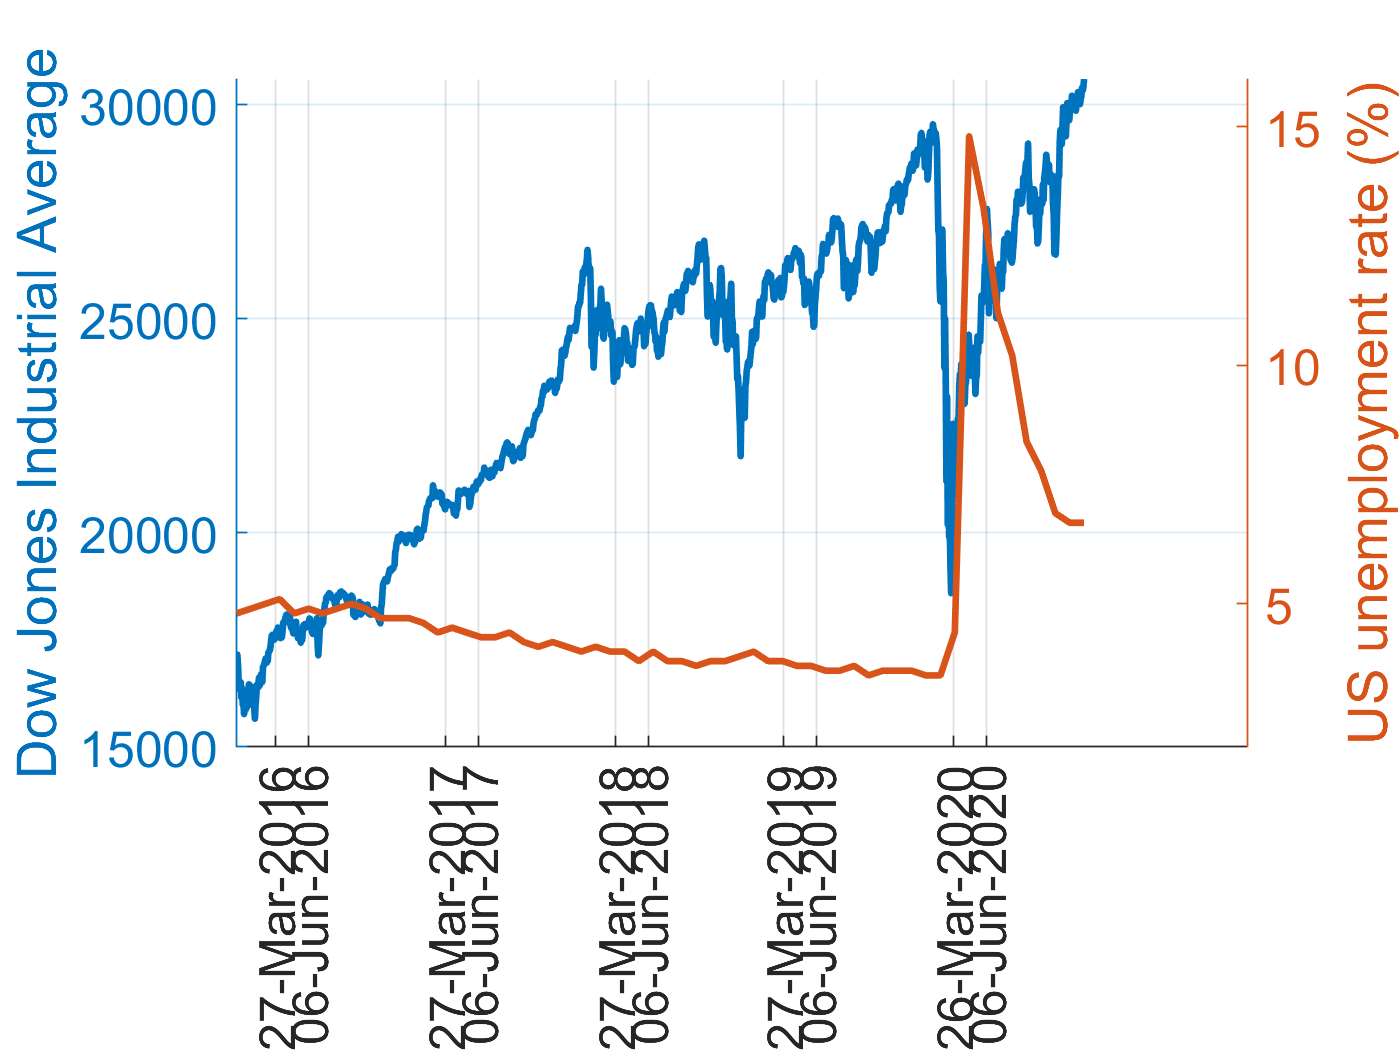

Subset = [datenum(2016, 3, 27);datenum(2016, 6, 6); datenum(2017, 3, 27);datenum(2017, 6, 6);datenum(2018, 3, 27);datenum(2018, 6, 6);datenum(2019, 3, 27);datenum(2019, 6, 6);datenum(2020, 3, 27);datenum(2020, 6, 6);];
t = datetime({raw2{1:1257,1}}, 'InputFormat', 'dd/MM/yyyy');
tlower = datetime(datestr(Subset ))-1;
tupper = datetime(datestr(Subset ))+1;

tf = [];
ctf=[];
for i=1:length(tlower)
    tmp = find(isbetween(t,tlower(i),tupper(i)));
    tf(i) = tmp(1);
    ctf{i} = datestr(t(tmp(1)));
    if length(tmp)==3
        tf(i) = tmp(2);
        ctf{i} = datestr(t(tmp(2)));
    end
end


figure;
ctf{10}(2)='6';
ctf{1}(2)='7';
yyaxis left;
plot(num2,'-','Color',[0 0.45 0.75],'LineWidth',2)
ax = gca;
ax.YAxis(1).Exponent = 0;
ylabel('Dow Jones Industrial Average')
yyaxis right
plot(idxq,unemploymentRate2015_2020,'Color',[0.85 0.33 0.1],'LineWidth',2)
ylabel('US unemployment rate (%)')
grid on
set(gca,'XTick',tf,'XTickLabel',ctf,'XTickLabelRotation',90,'FontSize',15)
box off

## **Figure 2. Income shock is related to temporal discounting rates.** 

**A**: For illustration purposes participants were split into those experiencing high income shock in orange (that is those that reported income shock higher than 3, which is the middle of the scale) and low income shock in cyan (<3). Displayed are the proportion of trials in which participants selected the immediate reward over the delayed reward (Y axis) as a function of the days associated with the delayed reward. The orange line is above the cyan line indicating that those experiencing higher income shock were more likely to select immediate rewards over delayed rewards for the same temporal delays.  The lines represent the prediction of the hyperbolic model and dots represent observed data. Error bars and shaded areas represents the standard error of the mean**. **N = 1,145. **B**: There was a strong relationship between income shock and the log temporal discounting rate in a model controlling for all demographic variables. In addition, greater temporal discounting rate was also related to less education, low income and a trend relationship with age. Figures show standardized coefficients from a linear model predicting the logged temporal discounting rates. Gender: 1 corresponds to male and 0 to female. N = 1,145.  **C**: Temporal changes in discounting rates (Y axis) are related to temporal changes in income shock (X axis). The orange line corresponds to the regression line controlling for demographic variables. Error bars correspond to the standard deviation of the mean. N = 184. Ϯ p < 0.1, ***P<0.001

% INCOME SHOCK
incomeShockTP1 = dataTable_covid19US_raw{:,18};
var2Table = [mean(incomeShockTP1) median(incomeShockTP1) std(incomeShockTP1)/sqrt(size(incomeShockTP1,1))];
matStats.incomeShock.summary  = array2table(var2Table);       
matStats.incomeShock.summary.Properties.VariableNames = {'Mean','Median','SE'};
matStats.incomeShock.summary.Properties.RowNames= {'time1ALL'};

**Figure 2A**

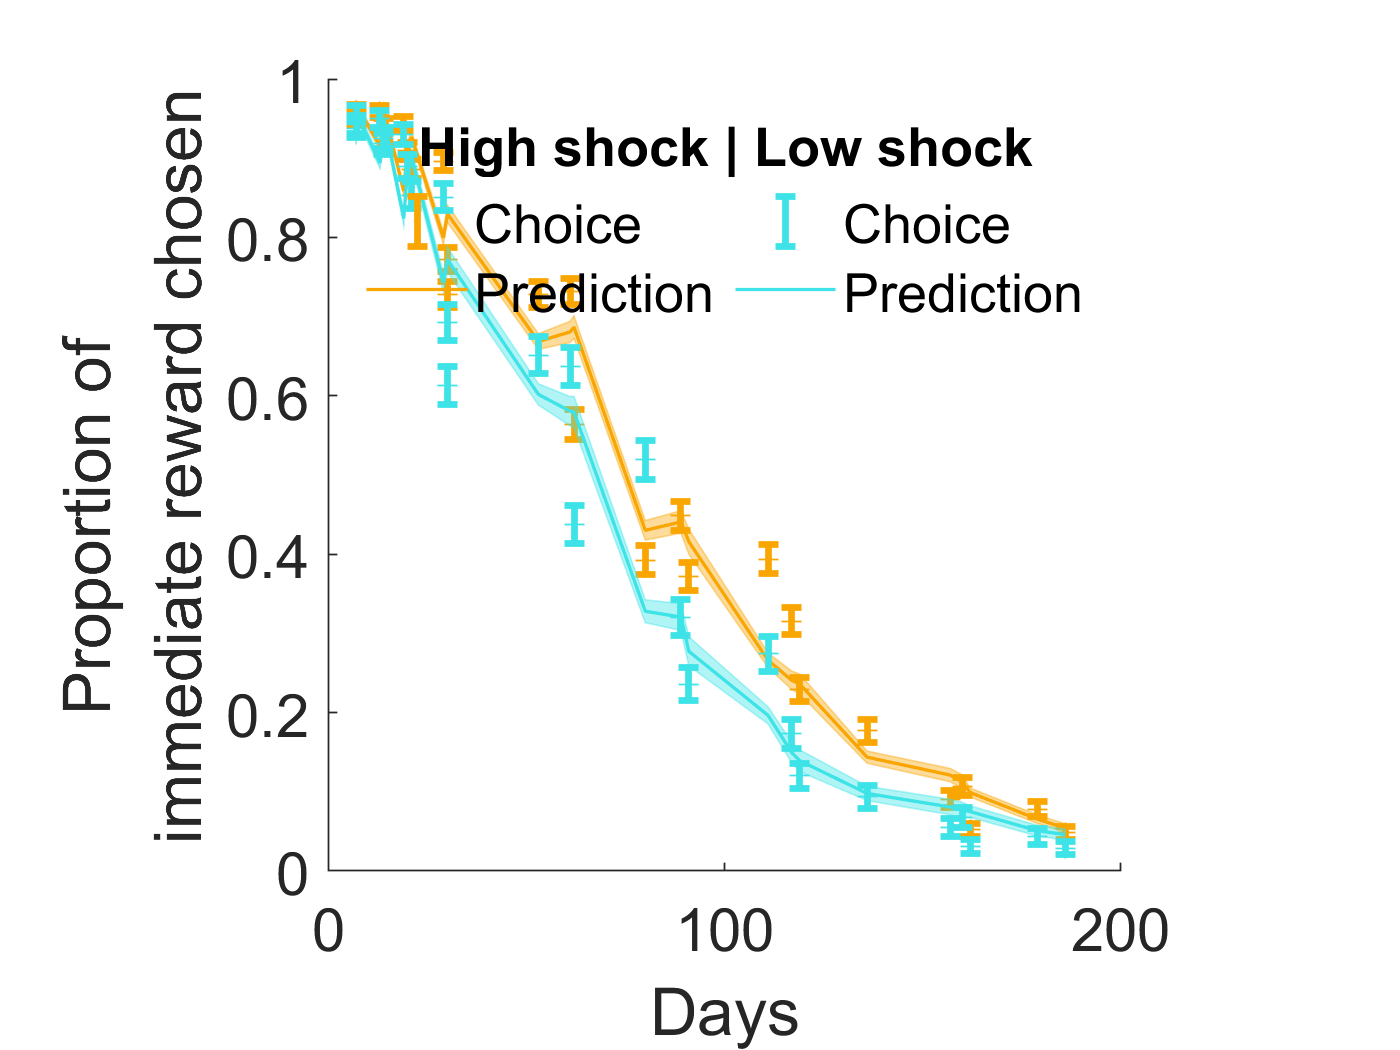

% fit plot
figure; hold on;
for igroup=1:2
    if igroup==1
        ioi = dataTable_covid19US_raw{:,18}>=3;
        lcolor = [249/255,166/255,2/255];
    else
        ioi =  dataTable_covid19US_raw{:,18}<3;
        lcolor = [0.24 0.89 0.9];
    end
    
    [ratioOrd] = sort(delay(2,:));%sort(log((rewardmag(2,:)./rewardmag(1,:)-1)./delay(2,:)));
    
    jbfill(ratioOrd,mean(matpredITC_sortedTP1((ioi),:))+std(matpredITC_sortedTP1((ioi),:))./sqrt(sum(ioi)),...
        mean(matpredITC_sortedTP1((ioi),:))-std(matpredITC_sortedTP1((ioi),:))./sqrt(sum((ioi))),...
        lcolor,lcolor,0,0.4);
     plot0{igroup} = plot(ratioOrd,mean(pImpSortedTP1((ioi),:)),'+','Color',lcolor);
     plot1{igroup} = errorbar(ratioOrd,mean(pImpSortedTP1((ioi),:)),std(pImpSortedTP1((ioi),:))./sqrt(sum(ioi)),'.','Color',lcolor,'LineWidth',2);
     plot2{igroup} = plot(ratioOrd,mean(matpredITC_sortedTP1((ioi),:)),'k','LineWidth',1,'Color',lcolor);
%     xlabel('log(delayed reward/Immediate reward)')
    xlabel('Days')
    ylabel('        Proportion of \newline immediate reward chosen')
    set(gca,'FontSize',18)
    if igroup==2
        l = legend([plot1{1} plot2{1} plot1{2} plot2{2}],{'Choice','Prediction','Choice','Prediction'});
        l.NumColumns = 2;
        title(l,'High shock | Low shock')
        legend boxoff
    end
    axis square
end 

% store stats
var2Table = [mean(matestTP1(:,3)), std(matestTP1(:,3))/sqrt(size(matestTP1,1)),...
    nanmean(matestTP1(:,[4])), nanstd(matestTP1(:,[4]))/sqrt(size(matestTP1,1))];
matStats.decision.ITC.fit = array2table(var2Table);
matStats.decision.ITC.fit.Properties.VariableNames = {'MeanR2','ESR2','MeanBacc','ESBacc'};
matStats.decision.ITC.fit.Properties.RowNames = {'time1ALL'};
var2Table = [nanmedian(log(matestTP1(:,1))) nanstd(log(matestTP1(:,1)))./sqrt(sum(income.sign<3))];
matStats.decision.ITC.k = array2table(var2Table);
matStats.decision.ITC.k.Properties.VariableNames = {'MedianK','ESK'};
matStats.decision.ITC.k.Properties.RowNames = {'time1ALL'};

**Figure 2B**

% regressions 
y  = zscore(log(matestTP1(:,1)));
IV =  zscore(dataTable_covid19US_raw{:,18});
demographics = dataTable_covid19US{:,{'Age' 'Gender' 'Education' 'Income'}};
%%% REGRESSION INCOME SCHOCK ~ DELAY DISCOUNTING RATE
[b,stats] = robustfit([demographics IV],y);
% get full stats for IS
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.ITC.kISdem= array2table(var2Table);
matStats.decision.ITC.kISdem.Properties.VariableNames = {'beta','se','t','df','p'};
matStats.decision.ITC.kISdem.Properties.RowNames = {'time1ALL'};
matStats.decision.ITC.kISdem

ans = 1×5 table
                 beta         se         t        df         p     
                _______    ________    ______    ____    __________

    time1ALL    0.13264    0.028774    4.6099    1139    4.4833e-06


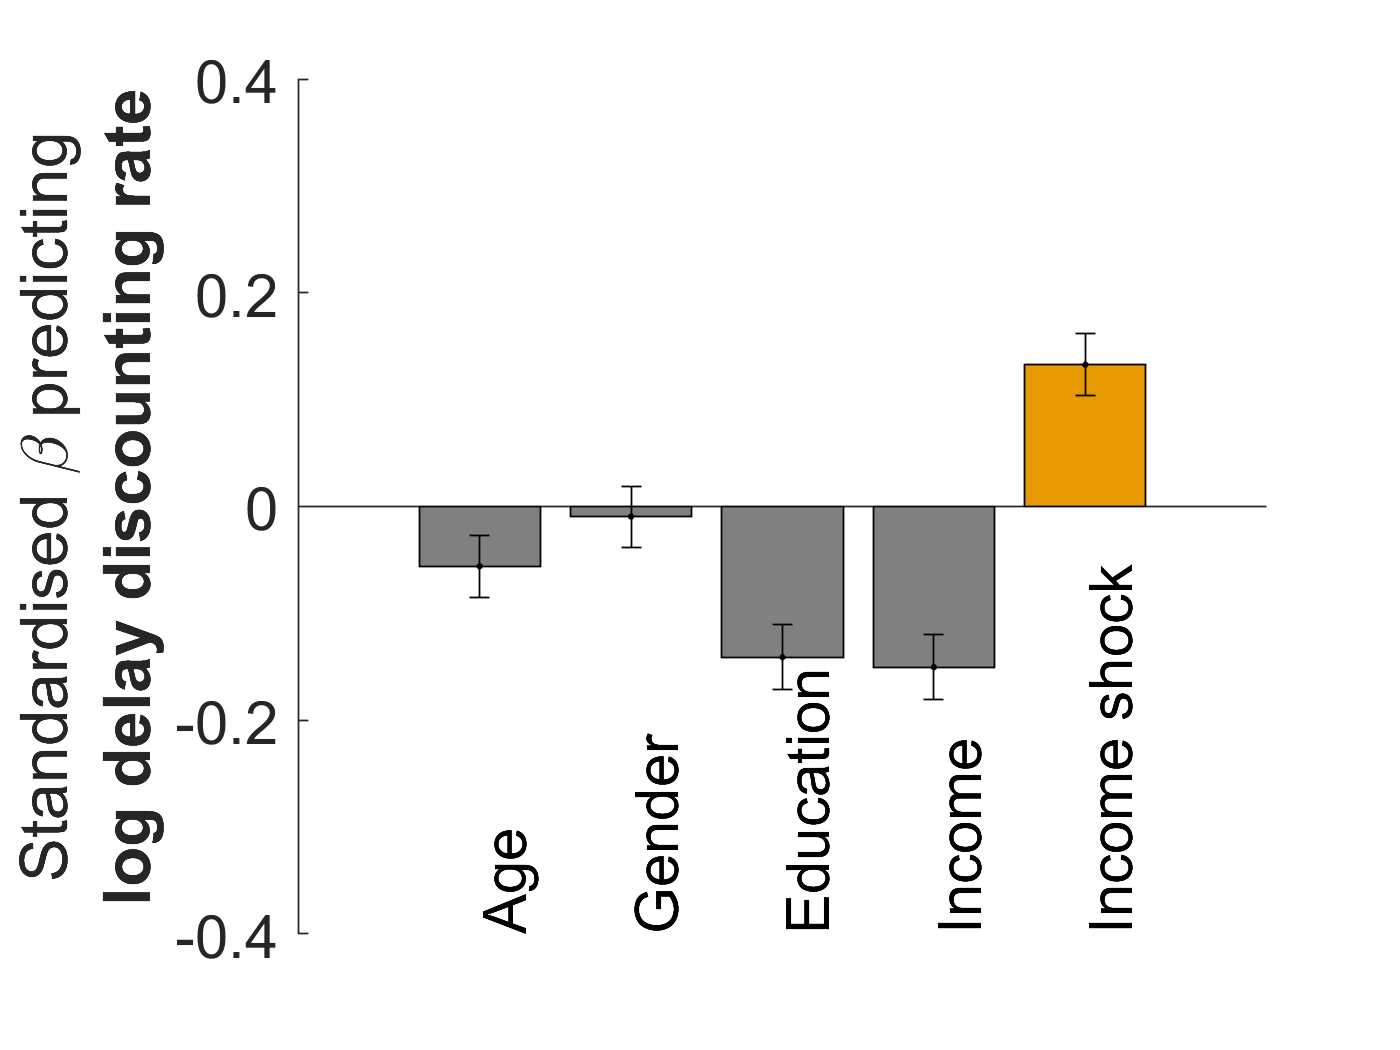

% get the p-values for demographics, to report to the plot
var2Table = [stats.p(2:(end-1))'];
matStats.decision.ITC.kdem = array2table(var2Table);
matStats.decision.ITC.kdem.Properties.VariableNames = {'Age' 'Gender' 'Education' 'Income'};%{'Age' 'Gender' 'Education' 'Income' 'PoliticalOrientation' 'Ethnicity' 'Children' 'HealthInsurance' 'Restrictions'};
matStats.decision.ITC.kdem.Properties.RowNames = {'time1ALL'};

figure;hold on;
bar(1:(length(b)-1),b(2:end),'FaceColor',[0.5 0.5 0.5]);
bar((length(b)-1),b(end),'FaceColor',[0.9 0.6 0]);
errorbar(1:(length(b)-1),b(2:end),stats.se(2:end),'k.');
lnames = {'Age' 'Gender' 'Education' 'Income' ... %demographics
    'Income shock'}; % behaviour
text([1:(length(b)-1)]+0.15,-0.4.*ones(1,length(b)-1),lnames,'rotation',90,'FontSize',18);
ylabel({'Standardised \beta predicting'; ['\bf log delay discounting rate']});
set(gca,'FontSize',18);
h = gca; h.XAxis.Visible = 'off';
ylim([-0.4 0.4])

% store IS effect without controlling for demographics
[b,stats] = robustfit([IV],y);
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.ITC.kIS = array2table(var2Table);
matStats.decision.ITC.kIS.Properties.VariableNames = {'beta','se','t','df','p'};
matStats.decision.ITC.kIS.Properties.RowNames = {'time1ALL'};
matStats.decision.ITC.kIS

ans = 1×5 table
                 beta        se         t       df         p     
                ______    ________    _____    ____    __________

    time1ALL    0.1645    0.029348    5.605    1143    2.6095e-08


**Figure 2C**

%% Change in log k is linked to the change in income shock
incomeShockTP2 = income.shock(income.sign<3,1);
[b, stats] = robustfit([demographics(idxNewSample(income.sign<3),:) incomeShockTP2-incomeShockTP1(idxNewSample(income.sign<3))],log(matestTP2((income.sign<3),1))-log(matestTP1(idxNewSample(income.sign<3),1)));
var2Table = [b(end),stats.se(end),stats.t(end),stats.dfe(end),stats.p(end)];
matStats.deltaIncomedeltaITC = array2table(var2Table);
matStats.deltaIncomedeltaITC.Properties.VariableNames ={'beta','SE','t','df','p'};
matStats.deltaIncomedeltaITC

ans = 1×5 table
     beta        SE         t      df        p    
    _______    _______    _____    ___    ________

    0.15442    0.05983    2.581    178    0.010657


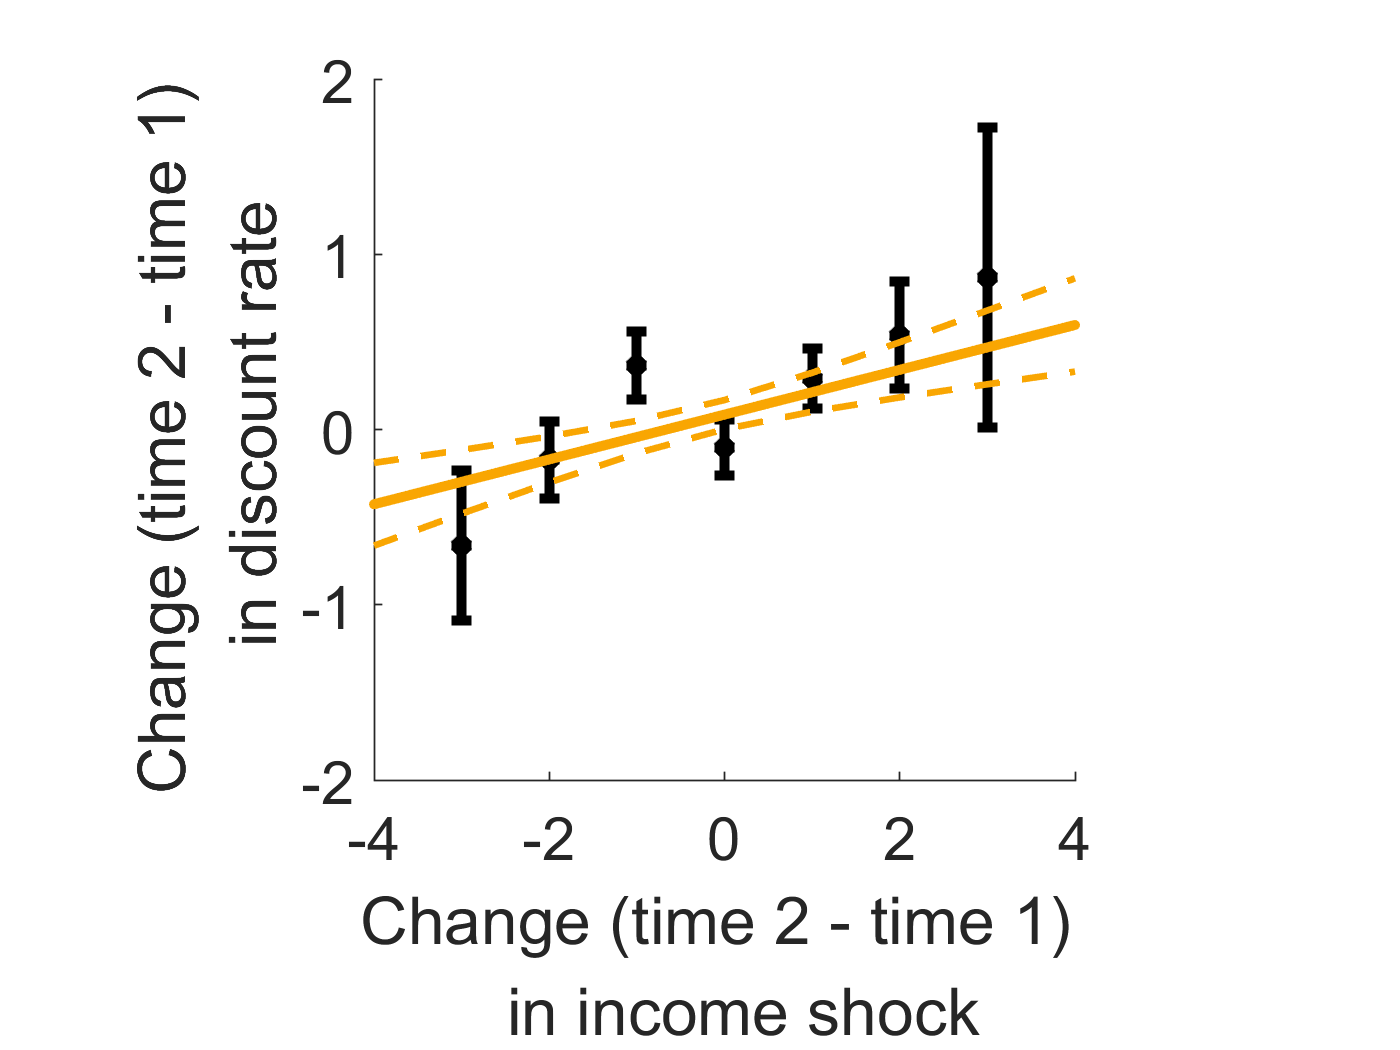


%robustness check 1: removing demographics (stil significant)
[b, stats] = robustfit([incomeShockTP2-incomeShockTP1(idxNewSample(income.sign<3))],log(matestTP2((income.sign<3),1))-log(matestTP1(idxNewSample(income.sign<3),1)));

deltaYY = log(matestTP2((income.sign<3),1))-log(matestTP1(idxNewSample(income.sign<3),1));
deltaXX = incomeShockTP2-incomeShockTP1(idxNewSample(income.sign<3));

lIV = unique(deltaXX);
for i=1:length(lIV)
    lDDm(i)  = nanmean(deltaYY(deltaXX==lIV(i)));
    lDDes(i) = nanstd(deltaYY(deltaXX==lIV(i)))./sqrt(sum(deltaXX==lIV(i)));
end
figure;hold on;
plot(lIV(2:(end-1))',lDDm(2:(end-1)),'k*','LineWidth',3)
errorbar(lIV(2:(end-1))',lDDm(2:(end-1)),lDDes(2:(end-1)),'.k','LineWidth',3)
xlabel('Change (time 2 - time 1) \newline        in income shock')
ylabel('Change (time 2 - time 1) \newline        in discount rate')
plot(deltaXX(2:(end-1)),b(1)+b(end).*deltaXX(2:(end-1)),'Color',[249/255,166/255,2/255],'LineWidth',3)
set(gca,'FontSize',18)
ylim([-2 2])
axis square
%compute se
n = size(deltaXX,1);
p = tcdf(0.975,n-2);
se= sqrt(sum((deltaYY - b(1)+b(end).*deltaXX).^2)./(n - 2)).*sqrt(1./n+(deltaXX - mean(deltaXX)).^2./sum((deltaXX - mean(deltaXX)).^2));
% get the boundaries
slopeUpper = b(1)+b(end).*deltaXX +p.*se;
slopeLower  = b(1)+b(end).*deltaXX -p.*se;
[aa,bb] = sort(deltaXX);
plot(aa,slopeUpper(bb),'--','Color',[249/255,166/255,2/255],'LineWidth',2);
plot(aa,slopeLower(bb),'--','Color',[249/255,166/255,2/255],'LineWidth',2);


% robustness check 2: including all income shock (still significant)
incomeShockTP1all = dataTP1(:,18);
incomeShockTP2all = income.shock(:,1);
demographics = dataTable_covid19US{idxNewSample,{'Age' 'Gender' 'Education' 'Income'}};
for idem=1:size(demographics,2)
    demographics(:,idem) = zscore(demographics(:,idem));
end
[b, stats] = robustfit([demographics incomeShockTP2all-incomeShockTP1all],log(matestTP2(:,1))-log(matestTP1(idxNewSample,1)));

## **Figure 3. Temporal discounting is related to negative affect**. 

**A**: For illustration purposes participants were split to those experiencing high negative affective state in red (<50) and low negative affective state in green (  50). Displayed are the proportion of trials in which participants selected the immediate reward over the delayed reward (Y axis) as a function of the days associated with the delayed reward. The lines represent the prediction of the hyperbolic model and dots represent observed data. Error bars and shaded areas represents the standard error of the mean.** B: **Figure shows standardized coefficients from a linear model predicting the logged temporal discounting rates when both affect and income shock compete for variance. Logged temporal discounting rate was related to greater negative affect and greater income shock, suggesting both variables independently influence temporal discounting. Gender: 1 corresponds to male and 0 to female. **C:** Figure illustrates the link between income shock and temporal discount rate when negative affective state and demographics are regressed out. Orange line refers to the regression line; dashed lines represent the confidence interval**. D:** Temporal changes in discounting rate (Y axis) are not related to temporal changes in negative affective state (X axis). The red line corresponds to the regression line, controlling for demographic variables (each of the 6 error bars corresponds to a bin of 30 participants). Dashed lines around represent the confidence interval. *P<0.05, ***P<0.0001

%%% REGRESSON Y~M
demographics = dataTable_covid19US{:,{'Age' 'Gender' 'Education' 'Income'}};
M = zscore((mean(dataTable_covid19US{1:end,[10:1:12]},2)));

X = [demographics M];
Y = y;
[b,stats] = robustfit(X,Y);
% get full stats for A
var2Table = [b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)];
matStats.decision.Affects.AKdem(1,:) = array2table(var2Table);
matStats.decision.Affects.AKdem.Properties.VariableNames = {'betaA','seA','tA','dfA','pA'};
% matStats.decision.Affects.AISdem.Properties.RowNames = {'time 1','time 2'};
% get the p-values for demographics, to report to the plot
var2Table = [stats.p(2:(end-1))'];
matStats.decision.Affects.kdemNoIS(1,:) = array2table(var2Table);
matStats.decision.Affects.kdemNoIS.Properties.VariableNames = {'Age' 'Gender' 'Education' 'Income'};


**Figure 3A**

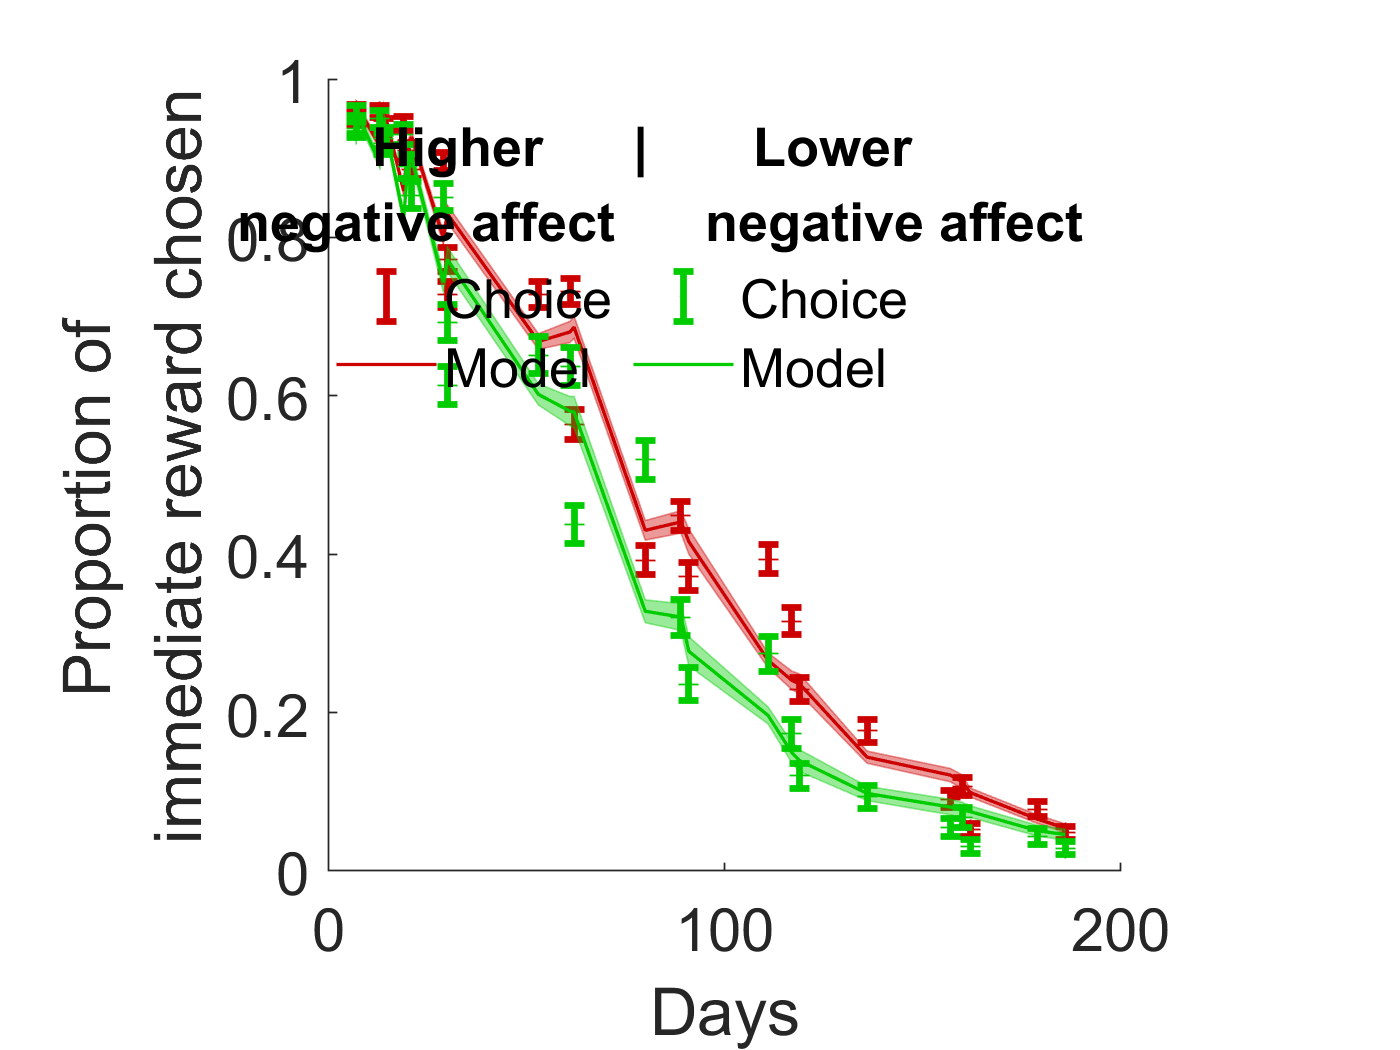

XX = incomeShockTP1;
YY = incomeShockTP2;
figure;hold on;%('Renderer', 'painters', 'Position', [10 10 700 500]);hold on;
for igroup=1:2
    if igroup==1
        ioi = XX >= median(XX);
        lcolor = [0.8 0 0];
    else
        ioi =  XX < median(XX);
        lcolor = [0 0.8 0];
    end
    
    [ratioOrd] = sort(delay(2,:));%sort(log((rewardmag(2,:)./rewardmag(1,:)-1)./delay(2,:)));
    
    jbfill(ratioOrd,mean(matpredITC_sortedTP1((ioi),:))+std(matpredITC_sortedTP1((ioi),:))./sqrt(sum(ioi)),...
        mean(matpredITC_sortedTP1((ioi),:))-std(matpredITC_sortedTP1((ioi),:))./sqrt(sum((ioi))),...
        lcolor,lcolor,0,0.4);
     plot0{igroup} = plot(ratioOrd,mean(pImpSortedTP1((ioi),:)),'+','Color',lcolor);
     plot1{igroup} = errorbar(ratioOrd,mean(pImpSortedTP1((ioi),:)),std(pImpSortedTP1((ioi),:))./sqrt(sum(ioi)),'.','Color',lcolor,'LineWidth',2);
     plot2{igroup} = plot(ratioOrd,mean(matpredITC_sortedTP1((ioi),:)),'k','LineWidth',1,'Color',lcolor);
%     xlabel('log(delayed reward/Immediate reward)')
    xlabel('Days')
    ylabel('         Proportion of \newline immediate reward chosen')
    set(gca,'FontSize',18)
    if igroup==2
        l = legend([plot1{1} plot2{1} plot1{2} plot2{2}],{'Choice','Model','Choice','Model'});
        l.NumColumns = 2;
        title(l,'              Higher      |       Lower \newline     negative affect      negative affect')
        legend boxoff
    end
    axis square
end 


[b,stats] = robustfit([M],y);
[b(end-1) stats.se(end-1) stats.t(end-1) stats.dfe stats.p(end-1)];
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.Affects.kNoIS = array2table(var2Table);
matStats.decision.Affects.kNoIS.Properties.VariableNames = {'beta','se','t','df','p'};

%%% REGRESSION M~IV
[b,stats] = robustfit([demographics IV],M);
% get full stats for IS
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.Affects.AISdem = array2table(var2Table);
matStats.Affects.AISdem.Properties.VariableNames = {'beta','se','t','df','p'};
var2Table = [stats.p(2:(end-1))'];
matStats.Affects.Adem = array2table(var2Table);
matStats.Affects.Adem.Properties.VariableNames = {'Age' 'Gender' 'Education' 'Income'};

% store IS effect without controlling for demographics
[b,stats] = robustfit([IV],M);
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.Affects.AIS = array2table(var2Table);
matStats.Affects.AIS.Properties.VariableNames = {'beta','se','t','df','p'};

**Figure 3B**

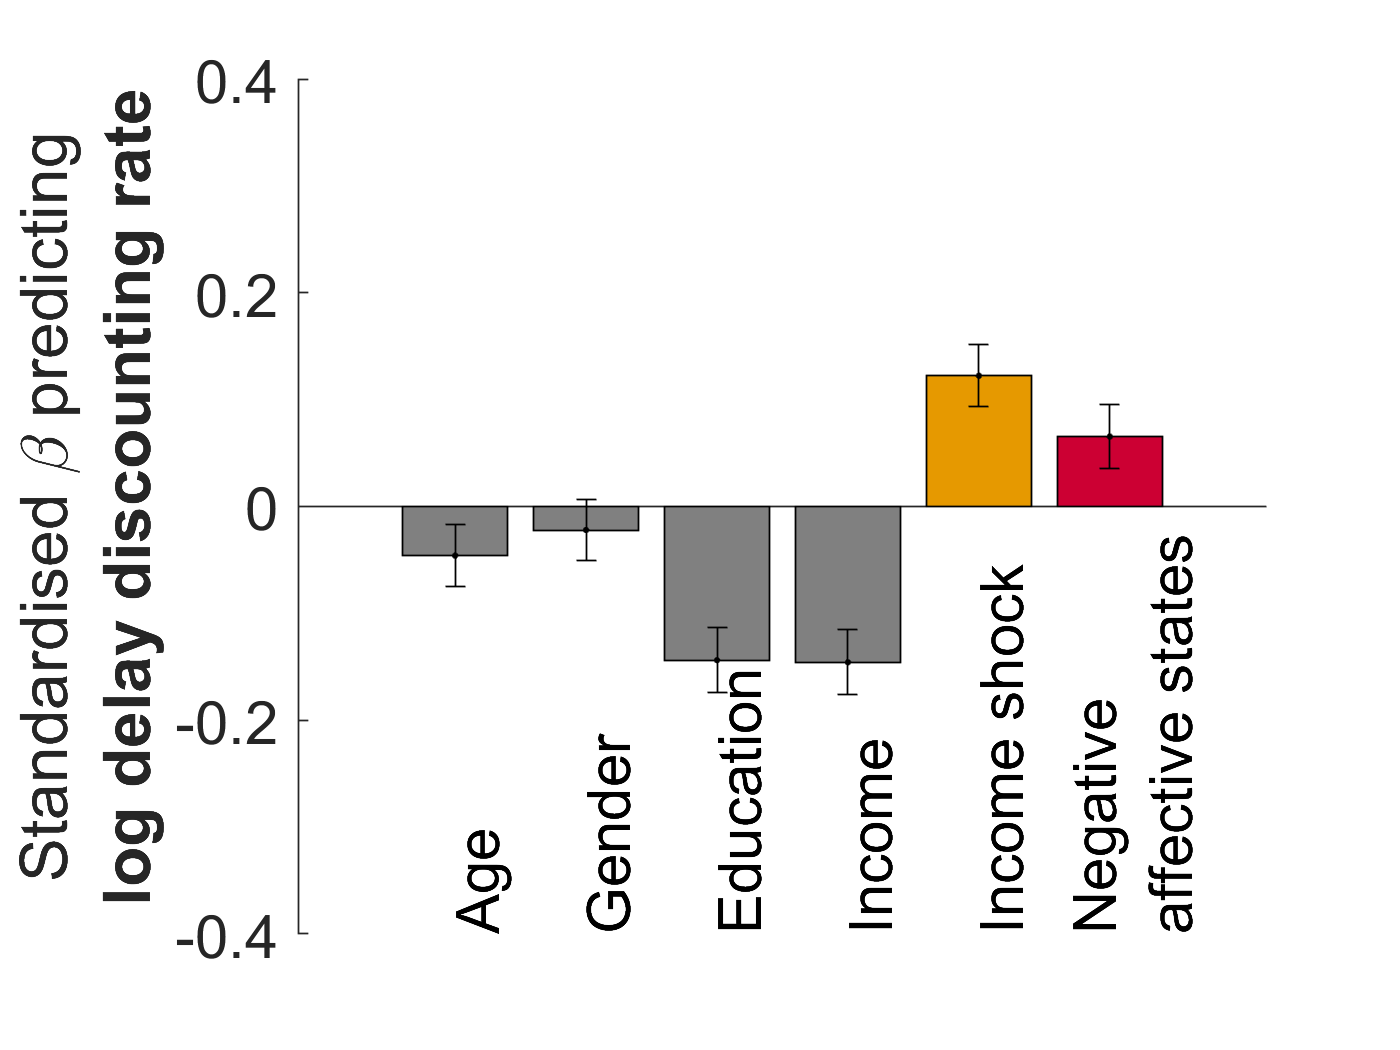

%%% REGRESSION Y~IV,M
[b,stats] = robustfit([demographics IV M],y);
figure;hold on;
bar(1:(length(b)-1),b(2:end),'FaceColor',[0.5 0.5 0.5]);
bar((length(b)-1),b(end),'FaceColor',[0.8 0 0.2]);
bar((length(b)-2),b(end-1),'FaceColor',[0.9 0.6 0]);
errorbar(1:(length(b)-1),b(2:end),stats.se(2:end),'k.')
lnames = {'Age' 'Gender' 'Education' 'Income'... %demographics
    'Income shock',{'Negative','affective states'} } ;% behaviour
text([1:(length(b)-1)]+0.15,-0.4.*ones(1,length(b)-1),lnames,'rotation',90,'FontSize',18)
ylabel({'Standardised \beta predicting'; ['\bf log delay discounting rate']})
% title('Time 1')
set(gca,'FontSize',18)
h = gca; h.XAxis.Visible = 'off';
ylim([-0.4 0.4])


%%% CONTROLLING FOR IS
% get full stats for IS
var2Table = [[b(end-1) stats.se(end-1) stats.t(end-1) stats.dfe stats.p(end-1) b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.Affects.AISKdem = array2table(var2Table);
matStats.decision.Affects.AISKdem.Properties.VariableNames = {'betaIS','seIS','tIS','dfIS','pIS','betaA','seA','tA','dfA','pA'};
matStats.decision.Affects.AISKdem

ans = 1×10 table
    betaIS       seIS       tIS      dfIS       pIS         betaA       seA         tA      dfA        pA   
    _______    ________    ______    ____    __________    _______    ________    ______    ____    ________

    0.12235    0.029037    4.2138    1138    2.7103e-05    0.06545    0.029637    2.2084    1138    0.027415


% matStats.decision.Affects.AISdem.Properties.RowNames = {'time 1','time 2'};
% get the p-values for demographics, to report to the plot
var2Table = [stats.p(2:(end-2))'];
matStats.decision.Affects.kdem = array2table(var2Table);
matStats.decision.Affects.kdem.Properties.VariableNames = {'Age' 'Gender' 'Education' 'Income'};

% store IS effect without controlling for demographics
[b,stats] = robustfit([IV,M],y);
var2Table = [[b(end-1) stats.se(end-1) stats.t(end-1) stats.dfe stats.p(end-1)],[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.Affects.AISK = array2table(var2Table);
matStats.decision.Affects.AISK.Properties.VariableNames = {'betaIS','seIS','tIS','dfIS','pIS','betaA','seA','tA','dfA','pA'};


**Figure 3C**

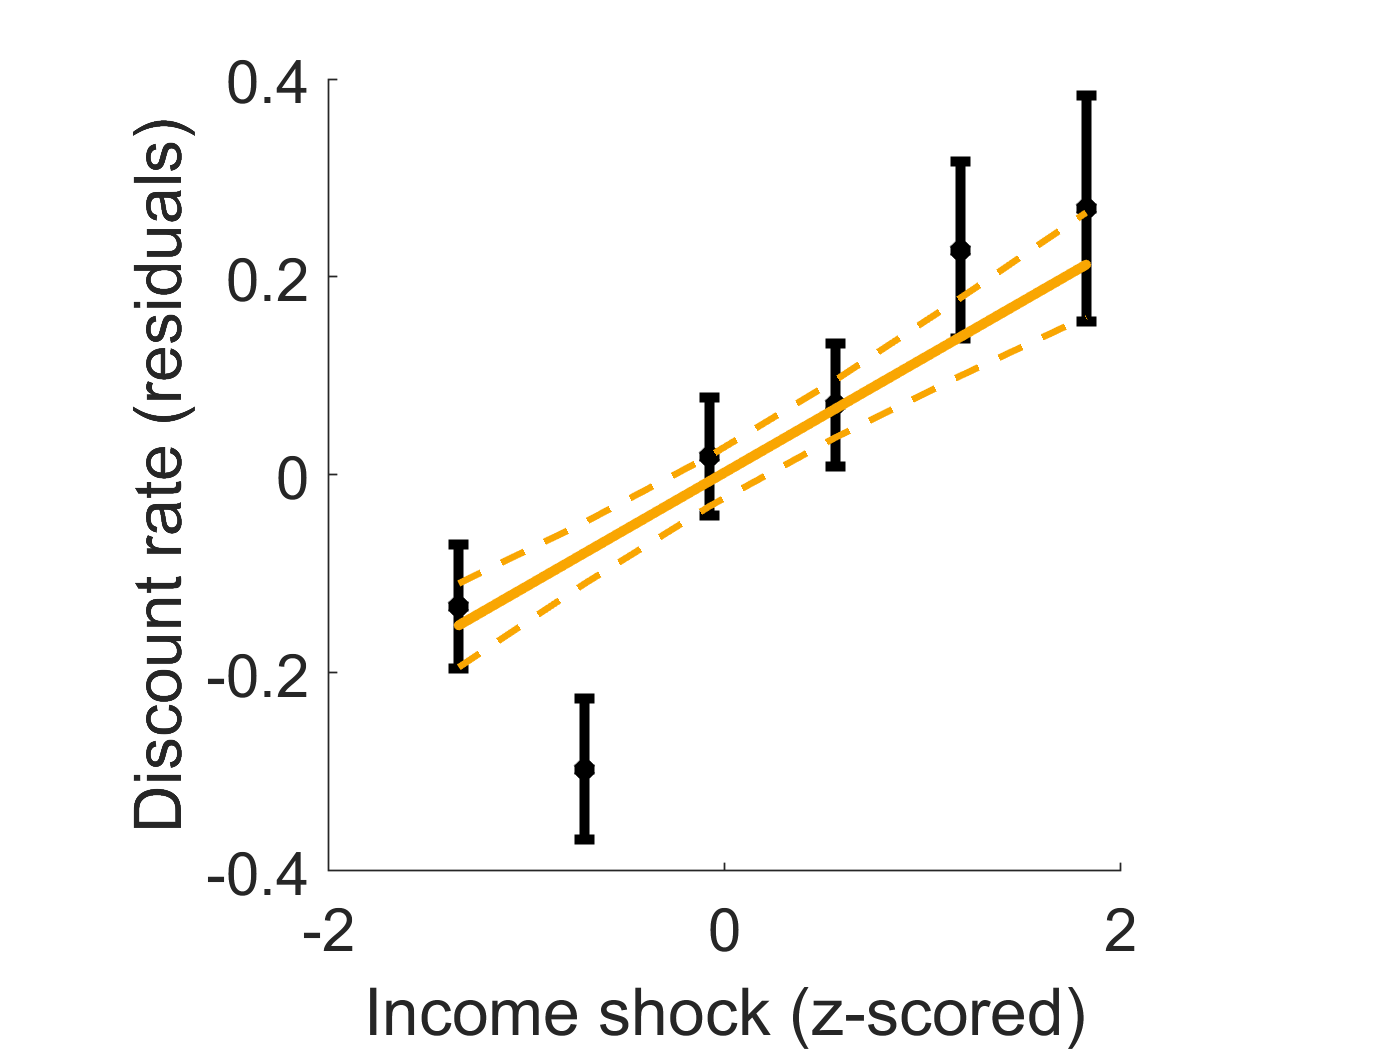

% PLOT IS EFFECT ON DDR
[b,stats] = robustfit([demographics M],y);
deltaXX = IV;
deltaYY = stats.resid;
[b,stats] = robustfit(IV,deltaYY);
lIV = unique(IV);
lDDm=[];lDDes=[];
for i=1:length(lIV)
    lDDm(i)  = mean(y(IV==lIV(i)));
    lDDes(i) = std(y(IV==lIV(i)))./sqrt(sum(IV==lIV(i)));
end
figure;hold on;
plot(lIV',lDDm,'k*','LineWidth',3)
errorbar(lIV',lDDm,lDDes,'.k','LineWidth',3) 
plot(deltaXX,b(1)+b(end).*deltaXX,'Color',[249/255,166/255,2/255],'LineWidth',3)
xlabel('Income shock (z-scored)')
ylabel('Discount rate (residuals)')
plot(deltaXX,b(1)+b(end).*deltaXX,'Color',[249/255,166/255,2/255],'LineWidth',3)
set(gca,'FontSize',18)
axis square
%compute se
n = size(IV,1);
p = tcdf(0.975,n-2);
se= sqrt(sum((y - b(1)+b(end).*IV).^2)./(n - 2)).*sqrt(1./n+(IV - mean(IV)).^2./sum((IV - mean(IV)).^2));
% get the boundaries
slopeUpper = b(1)+b(end).*IV +p.*se;
slopeLower  = b(1)+b(end).*IV -p.*se;
[aa,bb] = sort(IV);
plot(aa,slopeUpper(bb),'--','Color',[249/255,166/255,2/255],'LineWidth',2)
plot(aa,slopeLower(bb),'--','Color',[249/255,166/255,2/255],'LineWidth',2)

**Figure 3 D**

deltaYY = log(matestTP2((income.sign<3),1))-log(matestTP1(idxNewSample(income.sign<3),1));
deltaXX = (mean(matemotion(income.sign<3,[1 4 5]),2)./100- mean(dataTP1(income.sign<3,[10:1:12]),2)./100);

[b, stats] = robustfit([demographics(idxNewSample(income.sign<3),:) deltaXX],deltaYY);
var2Table = [b(end),stats.se(end),stats.t(end),stats.dfe(end),stats.p(end)];
matStats.deltaAffectdeltaK = array2table(var2Table);
matStats.deltaAffectdeltaK.Properties.VariableNames ={'beta','SE','t','df','p'};
matStats.deltaAffectdeltaK

ans = 1×5 table
     beta        SE         t       df        p   
    _______    _______    ______    ___    _______

    0.39757    0.33761    1.1776    178    0.24053


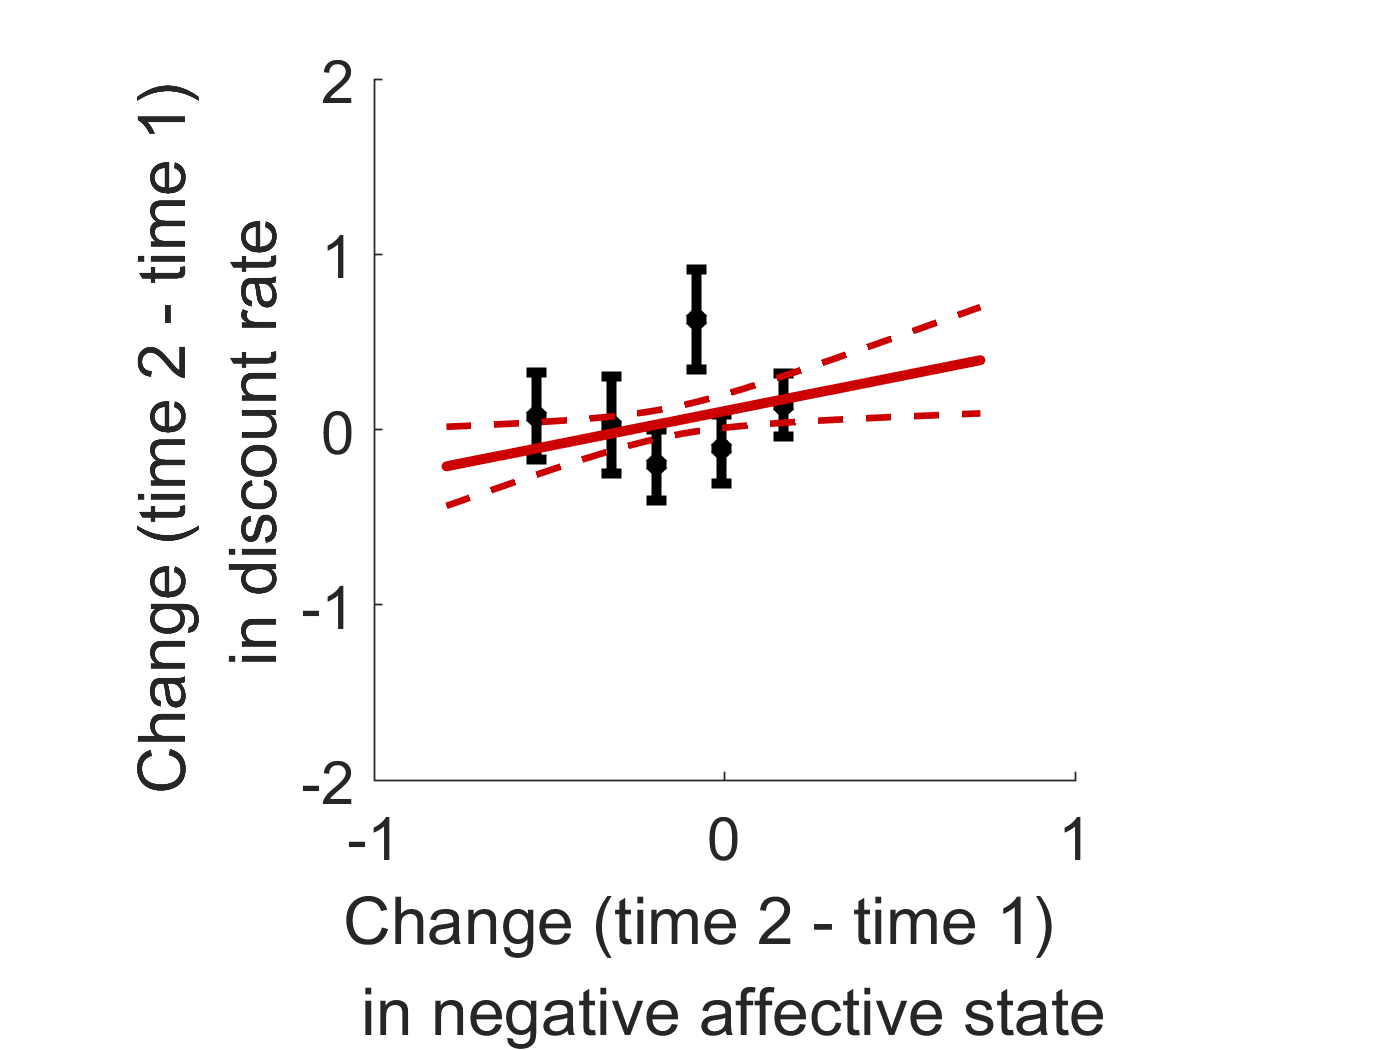



[lIV,idx]= sort(deltaXX);
lDDm=[];
lDDes=[];
lIVm=[];
lIVes=[];
N = 30;
for i=1:6%length(lIV)
    if i<6
        ioi = ((N*i-(N-1)):N*i);
    else
        ioi = ((N*i-(N-1)):184);
    end
    lDDm(i)  = nanmean(deltaYY(idx(ioi)));
    lDDes(i) = nanstd(deltaYY(idx(ioi)))./sqrt(30);
    lIVm(i)  = nanmean(lIV((ioi)));
    lIVes(i) = nanstd(lIV((ioi)))./sqrt(30);
end
figure;hold on;
plot(lIVm,lDDm,'k*','LineWidth',3)
errorbar(lIVm,lDDm,lDDes,'.k','LineWidth',3)
xlabel('Change (time 2 - time 1) \newline in negative affective state')
ylabel('Change (time 2 - time 1) \newline       in discount rate')
plot(deltaXX(2:(end-1)),b(1)+b(end).*deltaXX(2:(end-1)),'Color',[.8 0 0],'LineWidth',3)
set(gca,'FontSize',18)
ylim([-2 2])
axis square
%compute se
n = size(deltaXX,1);
p = tcdf(0.975,n-2);
se= sqrt(sum((deltaYY - b(1)+b(end).*deltaXX).^2)./(n - 2)).*sqrt(1./n+(deltaXX - mean(deltaXX)).^2./sum((deltaXX - mean(deltaXX)).^2));
% get the boundaries
slopeUpper = b(1)+b(end).*deltaXX +p.*se;
slopeLower  = b(1)+b(end).*deltaXX -p.*se;
[aa,bb] = sort(deltaXX);
plot(aa,slopeUpper(bb),'--','Color',[.8 0 0],'LineWidth',2)
plot(aa,slopeLower(bb),'--','Color',[.8 0 0],'LineWidth',2)

## Mediation analysis

We next conducted a formal mediation to test whether negative affective state was mediating the effect of income shock on temporal discounting rate. Using a Sobel test on the product of the weight between income shock and affective state and the weight from affective state to temporal discounting rate (denoted alpha and beta respectively), we found that negative affective state did not mediate the effect of income shock on temporal delay discounting regardless of whether we controlled for demographics (Sobel test on alpha*beta = 0.004±0.002, t1138 = 1.5, p = 0.13) or not (Sobel test on alpha*beta = 0.003±0.002, t1142 = 1.3, p = 0.20). 

demographics = demographics(idxNewSample(income.sign<3),:);
%% mediation at both time points
for i=1:4
    s=0;
    if mod(i,2)==1
        y  = zscore(log(matestTP1(idxNewSample(income.sign<3),1)));
        M  =  zscore(mean(dataTP1(income.sign<3,[10:1:12]),2));
        IV =  zscore(incomeShockTP1(idxNewSample(income.sign<3)));
    else
        y  = zscore(log(matestTP2((income.sign<3),1)));
        IV =  zscore(incomeShockTP2);
        M =  zscore((mean(matemotion(income.sign<3,[1 4 5]),2)));
    end
    if i>2
        demographics = [];
    end
    
    
    % step 1) regress Y on X
    [b,dev,stats] = glmfit([demographics IV],y);
    tau(i) = b(end);
    tauSE(i) = stats.se(end);
    tauP(i) = stats.p(end);
    s=s+1;
    matstats.mediation{i}(s,:) = [b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)];
    
    % step 2) regress M on X
    [b,dev,stats] = glmfit([demographics IV],M);
    alpha(i) = b(end);
    alphaV(i)            = stats.se(end)^2;
    alphaSE(i) = stats.se(end);
    alphaP(i) = stats.p(end);
    s=s+1;
    matstats.mediation{i}(s,:) = [b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)];
    
    
    % step 3) regress Y on X and M
    [b,dev,stats] = glmfit([demographics IV,M],y);
    tau_prime(i)         = b(end-1);
    tau_primeSE(i) = stats.se(end-1);
    tau_primeP(i) = stats.p(end-1);
    s=s+1;
    matstats.mediation{i}(s,:) = [b(end-1) stats.se(end-1) stats.t(end-1) stats.dfe stats.p(end-1)];
    
    beta(i)             = b(end);
    betaV(i)            = stats.se(end)^2;
    betaSE(i) = stats.se(end);
    betaP(i) = stats.p(end);
    s=s+1;
    matstats.mediation{i}(s,:) = [b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)];
    matstats.mediation{i} = array2table(matstats.mediation{i},'RowNames',{'tau','alpha','tauPrime','beta'},'VariableNames',{'beta','SE','t','df','p'});
    
    % inference based on a Sobel t-test
    SE = sqrt(alpha(i)^2*betaV(i) + beta(i)^2*alphaV(i));
    t = abs(alpha(i)*beta(i)/SE);
    p(i) = 2*spm_Ncdf(-t,0,1);
    matstats.mediationSobel{i} = [alpha(i)*beta(i) SE t stats.dfe p(i)];
    matstats.mediationSobel{i} = array2table(matstats.mediationSobel{i}(1,:),'VariableNames',{'alphaBeta','SE','t','df','p'});
    matstats.mediationSobel{i}
end  

ans = 1×5 table
    alphaBeta       SE         t       df        p   
    _________    ________    ______    ___    _______

    0.027606     0.019825    1.3924    177    0.16379


ans = 1×5 table
    alphaBeta       SE           t       df        p   
    _________    _________    _______    ___    _______

    0.001704     0.0062905    0.27089    177    0.78648


ans = 1×5 table
    alphaBeta       SE         t       df        p   
    _________    ________    ______    ___    _______

     0.02312     0.020394    1.1337    181    0.25692


ans = 1×5 table
    alphaBeta       SE          t       df        p   
    _________    _________    ______    ___    _______

    0.0020908    0.0068869    0.3036    181    0.76143


We then examined whether this change in affective state mediated the relationship between the change in income shock and temporal discounting rate. The mediation analysis revealed that it was not – regardless of whether we controlled for demographics (Sobel test on alpha*beta = 0.00008±0.00098, t177 = 0.09, p = 0.93) or not (Sobel test on alpha*beta = 0.00087±0.0055, t181 = 0.16, p = 0.87). 

%% mediation related to changes
demographics = dataTable_covid19US{(income.sign<3),{'Age' 'Gender' 'Education' 'Income'}};
y  = zscore(log(matestTP2((income.sign<3),1))-log(matestTP1(idxNewSample(income.sign<3),1)));
M  =  zscore((mean(matemotion(income.sign<3,[1 4 5]),2))-mean(dataTP1(income.sign<3,[10:1:12]),2));
IV =  zscore(incomeShockTP2-incomeShockTP1(idxNewSample(income.sign<3)));
for i=1:2
    s=0;
    if i>1
        demographics = [];
    end   
    
    % step 1) regress Y on X
    [b,dev,stats] = glmfit([demographics IV],y);
    tau(i) = b(end);
    tauSE(i) = stats.se(end);
    tauP(i) = stats.p(end);
    s=s+1;
    matstats.mediationChange{i}(s,:) = [b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)];
    
    % step 2) regress M on X
    [b,dev,stats] = glmfit([demographics IV],M);
    alpha(i) = b(end);
    alphaV(i)            = stats.se(end)^2;
    alphaSE(i) = stats.se(end);
    alphaP(i) = stats.p(end);
    s=s+1;
    matstats.mediationChange{i}(s,:) = [b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)];
    
    
    % step 3) regress Y on X and M
    [b,dev,stats] = glmfit([demographics IV,M],y);
    tau_prime(i)         = b(end-1);
    tau_primeSE(i) = stats.se(end-1);
    tau_primeP(i) = stats.p(end-1);
    s=s+1;
    matstats.mediationChange{i}(s,:) = [b(end-1) stats.se(end-1) stats.t(end-1) stats.dfe stats.p(end-1)];
    
    beta(i)             = b(end);
    betaV(i)            = stats.se(end)^2;
    betaSE(i) = stats.se(end);
    betaP(i) = stats.p(end);
    s=s+1;
    matstats.mediationChange{i}(s,:) = [b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)];
    matstats.mediationChange{i} = array2table(matstats.mediationChange{i},'RowNames',{'tau','alpha','tauPrime','beta'},'VariableNames',{'beta','SE','t','df','p'});
    
    % inference based on a Sobel t-test
    SE = sqrt(alpha(i)^2*betaV(i) + beta(i)^2*alphaV(i));
    t = abs(alpha(i)*beta(i)/SE);
    p(i) = 2*spm_Ncdf(-t,0,1);
    matstats.mediationChangeSobel{i} = [alpha(i)*beta(i) SE t stats.dfe p(i)];
    matstats.mediationChangeSobel{i} = array2table(matstats.mediationChangeSobel{i},'VariableNames',{'beta','SE','t','df','p'});
    matstats.mediationChangeSobel{i}
end

ans = 1×5 table
       beta           SE           t        df        p   
    __________    __________    ________    ___    _______

    8.5244e-05    0.00097583    0.087355    177    0.93039


ans = 1×5 table
       beta          SE           t       df        p   
    __________    _________    _______    ___    _______

    0.00087828    0.0054524    0.16108    181    0.87203


## **Supplementary figure 1. Overview of demographics. **

Sample (N = 1145) is representative of the US population in terms of **(a) **Age, **(b)** Gender, and **(c)**Education, and **(d)** Income, as well as the subsample (N = 200, **e-h**). Participants resided in 30 US States at time of testing. 

demographics = dataTable_covid19US_raw{:,{'Age' 'Gender' 'Education' 'Income'}};
sum(demographics(:,2)==1)

ans = 546

mean(demographics(:,1)),std(demographics(:,1))

ans = 44.0061

ans = 15.5860

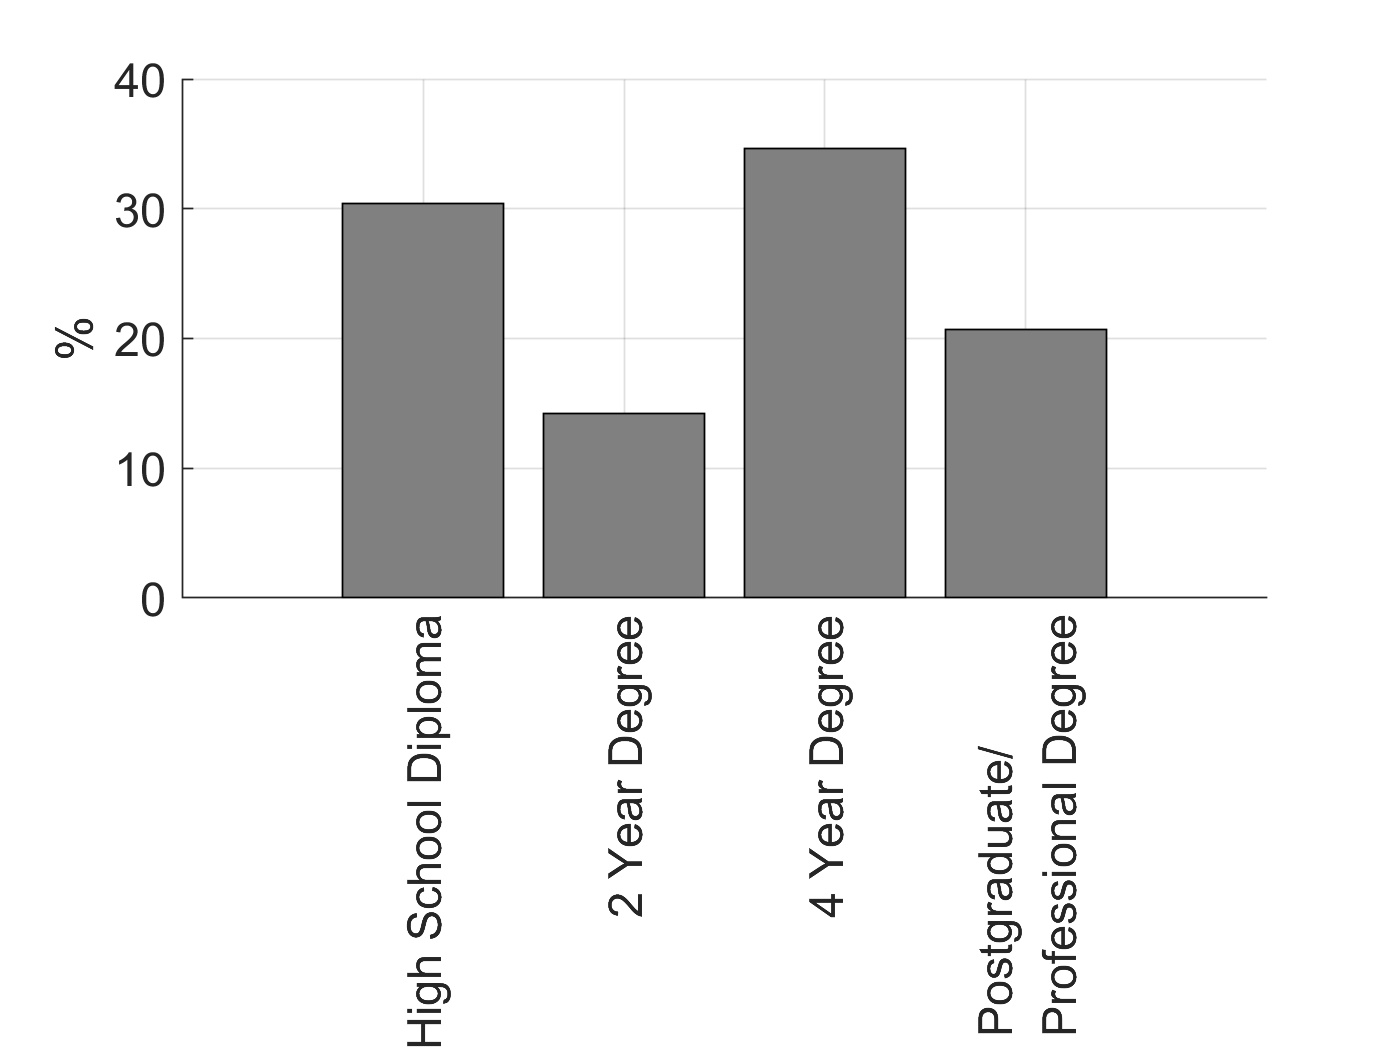

for i=1:size(unique(demographics(:,3)),1)
    cumFreqEdu(i) = sum(demographics(:,3)==i);
end

for i=1:size(unique(demographics(:,4)),1)
    freqWage(i) = sum(demographics(:,4)==i);
    perWage(i) = mean(demographics(:,4)==i);
end
% A = 48; B = 50 - 48 = 2; percentage of the median interval: D = 12%; range of the median interval c = 15000
% E = B/D * C = 2500; median = 52500
% figure;plot(cumsum(freqWage))


% High School Diploma
% 2 Year Degree
% 4 Year Degree  (3) 
% Postgraduate/Professional Degree  (4)
figure;hold on;
for i=1:4
    matStats.dem.education(i) = mean(demographics(:,3)==i);
    bar(i,matStats.dem.education(i).*100,'FaceColor',[.5 .5 .5]);grid on;box off;
end
labels = {'High School Diploma','2 Year Degree','4 Year Degree','Postgraduate/\newlineProfessional Degree'};
ylabel('%')
ylim([0 40])
set(gca,'XTick',1:4,'XTickLabel',labels,'XTickLabelRotation',90,'FontSize',14)

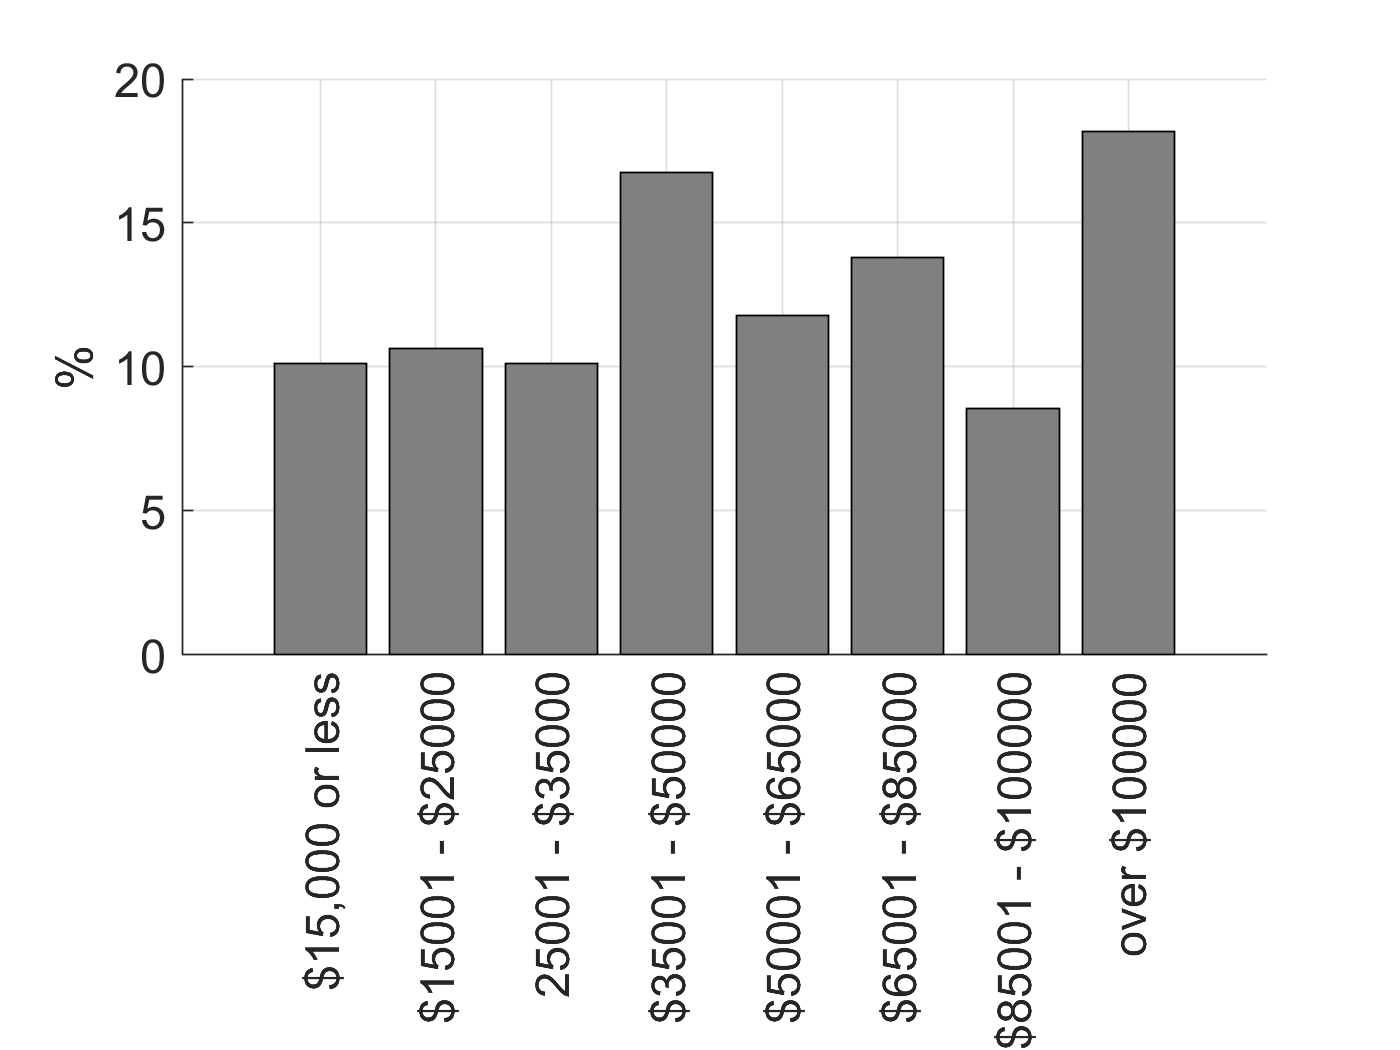



figure;hold on;
for i=1:8
    matStats.dem.income(i) = mean(demographics (:,4)==i);
    bar(i,matStats.dem.income(i).*100,'FaceColor',[.5 .5 .5]);grid on;box off;
end
labels = {"$15,000 or less","$15001 - $25000","25001 - $35000",...
    "$35001 - $50000","$50001 - $65000" ,...
    "$65001 - $85000","$85001 - $100000" ,"over $100000"} ;
ylabel('%')
set(gca,'XTick',1:8,'XTickLabel',labels,'XTickLabelRotation',90,'FontSize',14)

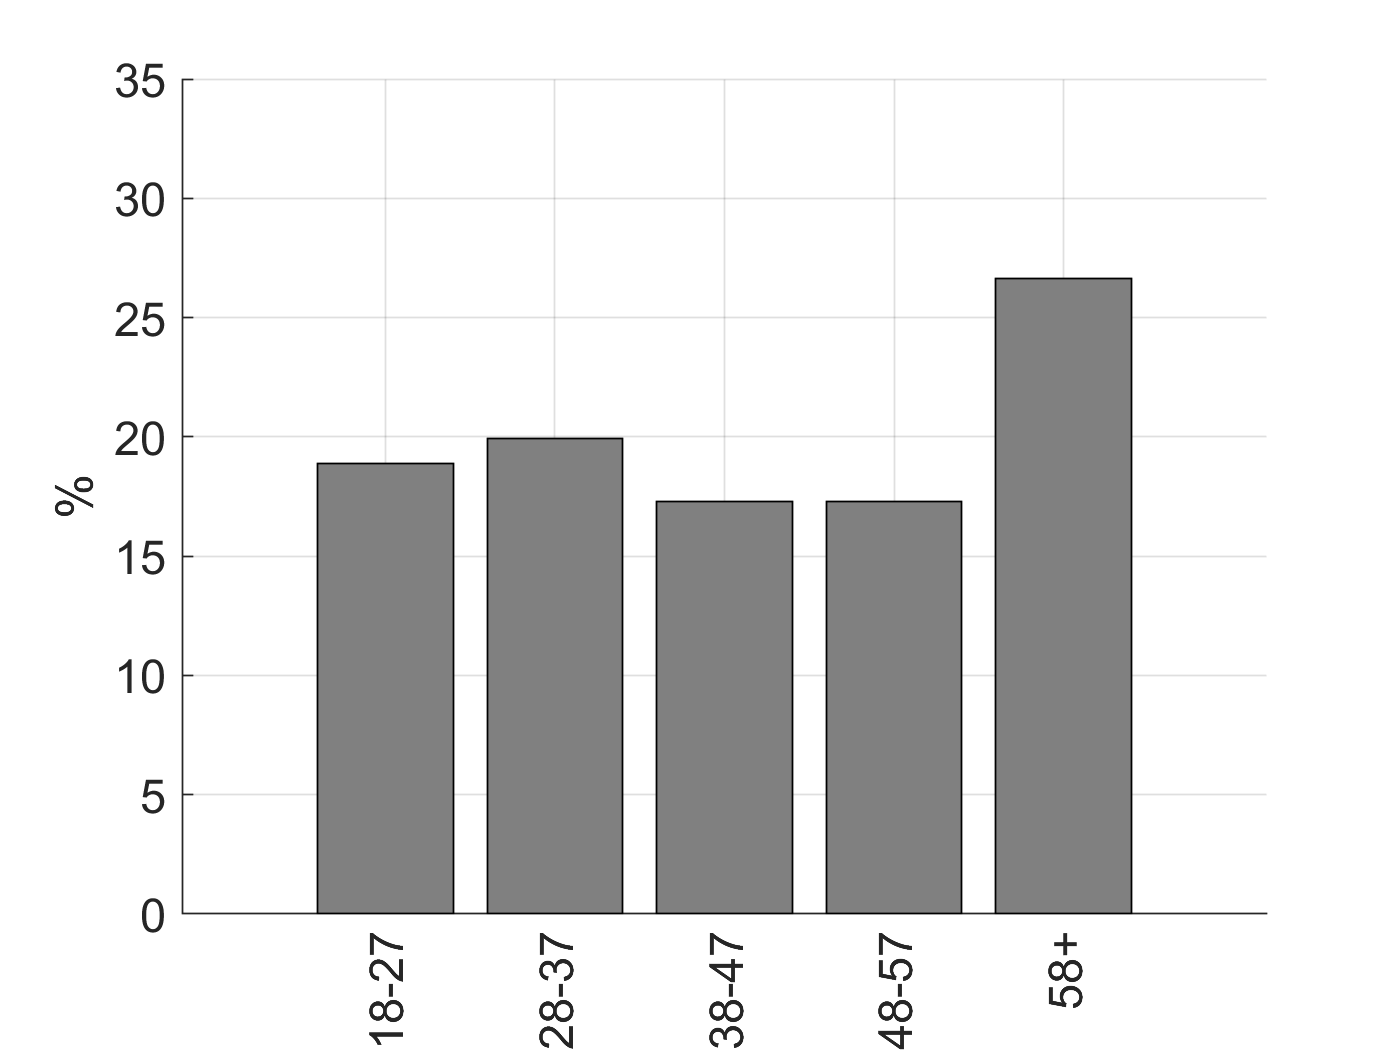



matStats.dem.age(1) = sum(demographics (:,1)>=18 & demographics (:,1)<=27)/size(demographics (:,1),1);
matStats.dem.age(2) = sum(demographics (:,1)>=28 & demographics (:,1)<=37)/size(demographics (:,1),1);
matStats.dem.age(3) = sum(demographics (:,1)>=38 & demographics (:,1)<=47)/size(demographics (:,1),1);
matStats.dem.age(4) = sum(demographics (:,1)>=48 & demographics (:,1)<=57)/size(demographics (:,1),1);
matStats.dem.age(5) = sum(demographics (:,1)>=58)/size(demographics (:,1),1);
matStats.dem.ageMeanSD = [mean(demographics (:,1)) std(demographics (:,1))];
figure;hold on;
for i=1:5
    bar(i,matStats.dem.age(i).*100,'FaceColor',[.5 .5 .5]);grid on;box off;
end
labels = {"18-27","28-37","38-47","48-57","58+"} ;
ylabel('%')
ylim([0 35])
set(gca,'XTick',1:5,'XTickLabel',labels,'XTickLabelRotation',90,'FontSize',14)

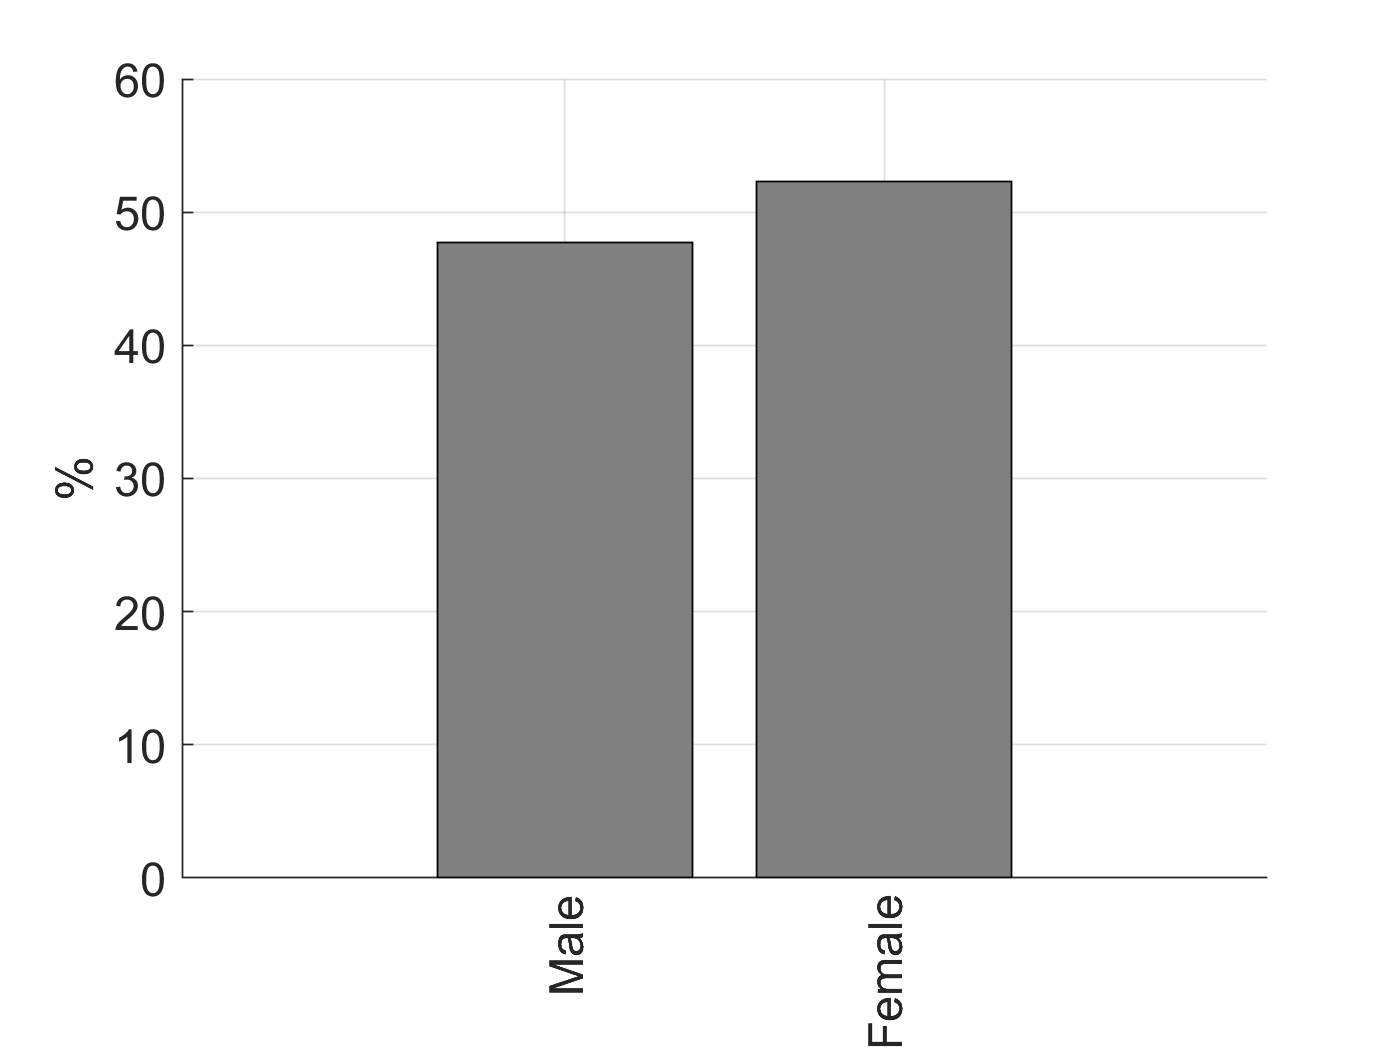


matStats.dem.gender = [mean(demographics(:,2)==1) mean(demographics(:,2)==2)];
figure;hold on;
for i=1:2
    bar(i,matStats.dem.gender(i).*100,'FaceColor',[.5 .5 .5]);grid on;box off;
end
labels = {"Male","Female"};
ylabel('%')
set(gca,'XTick',1:2,'XTickLabel',labels,'XTickLabelRotation',90,'FontSize',14)

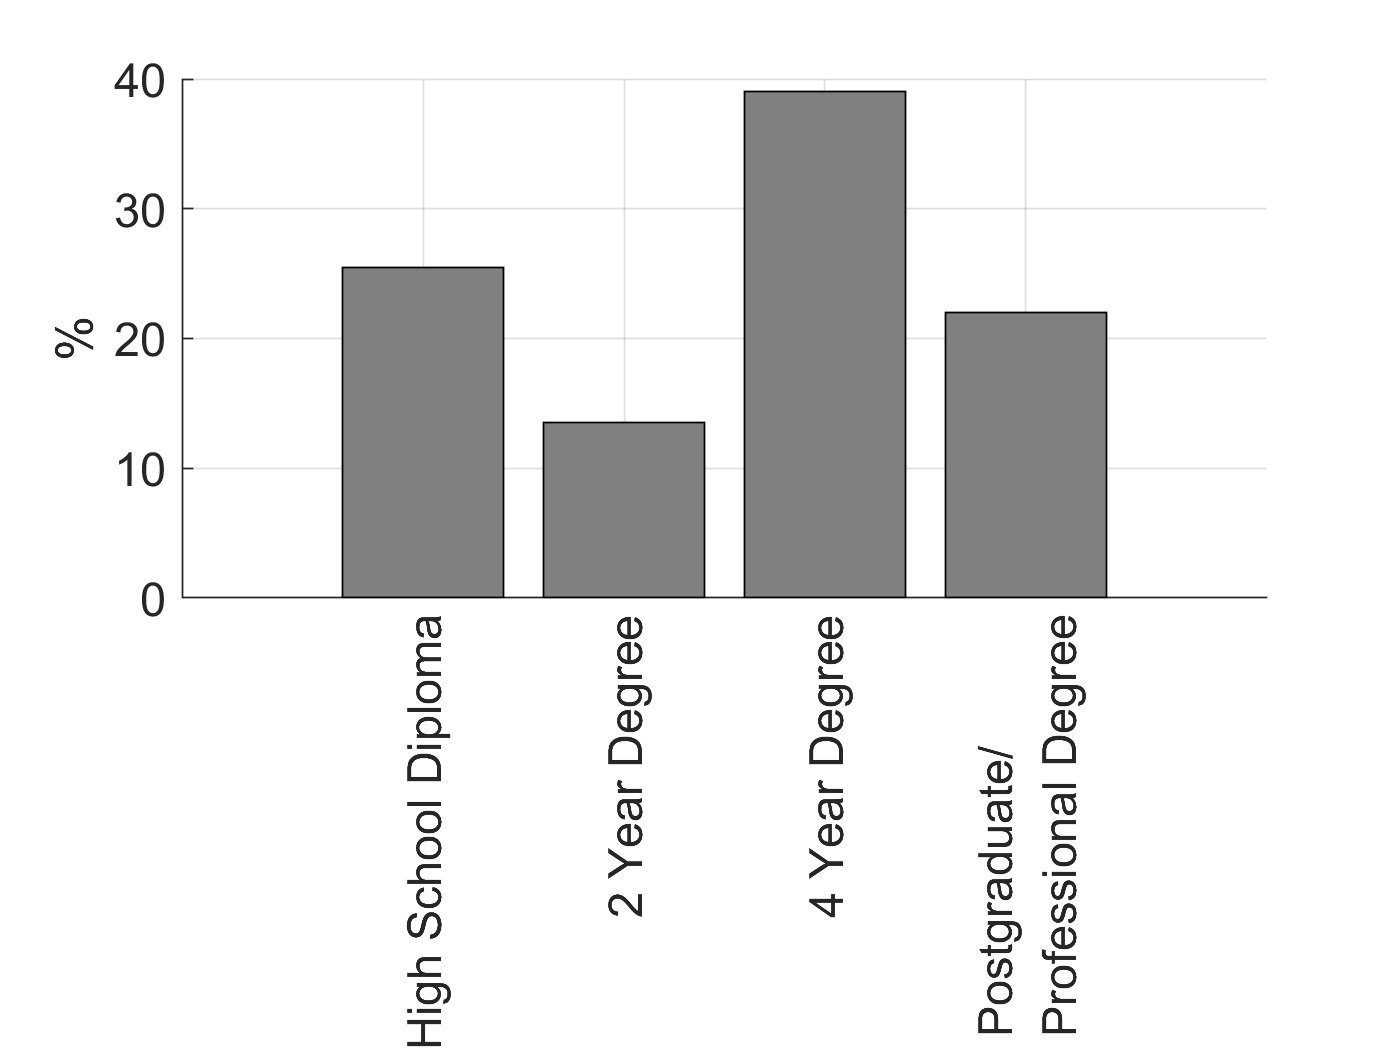


%% SUBSET
%% demographics
[a,states] = xlsread('stateAll.xlsx');
lStates = [states{idxNewSample(income.sign<3)}];

%'Age' 'Gender' 'Education' 'Income' {'Political', 'Orientation'} 'Ethnicity' 'Children' {'Health Insurance','satisfaction'} 'Restrictions'... %demographics

% High School Diploma
% 2 Year Degree
% 4 Year Degree  (3) 
% Postgraduate/Professional Degree  (4)
figure;hold on;
for i=1:4
    matStats.dem.education(i) = mean(dataTP1(:,3)==i);
    bar(i,matStats.dem.education(i).*100,'FaceColor',[.5 .5 .5]);grid on;box off;
end
labels = {'High School Diploma','2 Year Degree','4 Year Degree','Postgraduate/\newlineProfessional Degree'};
ylabel('%')
set(gca,'XTick',1:4,'XTickLabel',labels,'XTickLabelRotation',90,'FontSize',14)

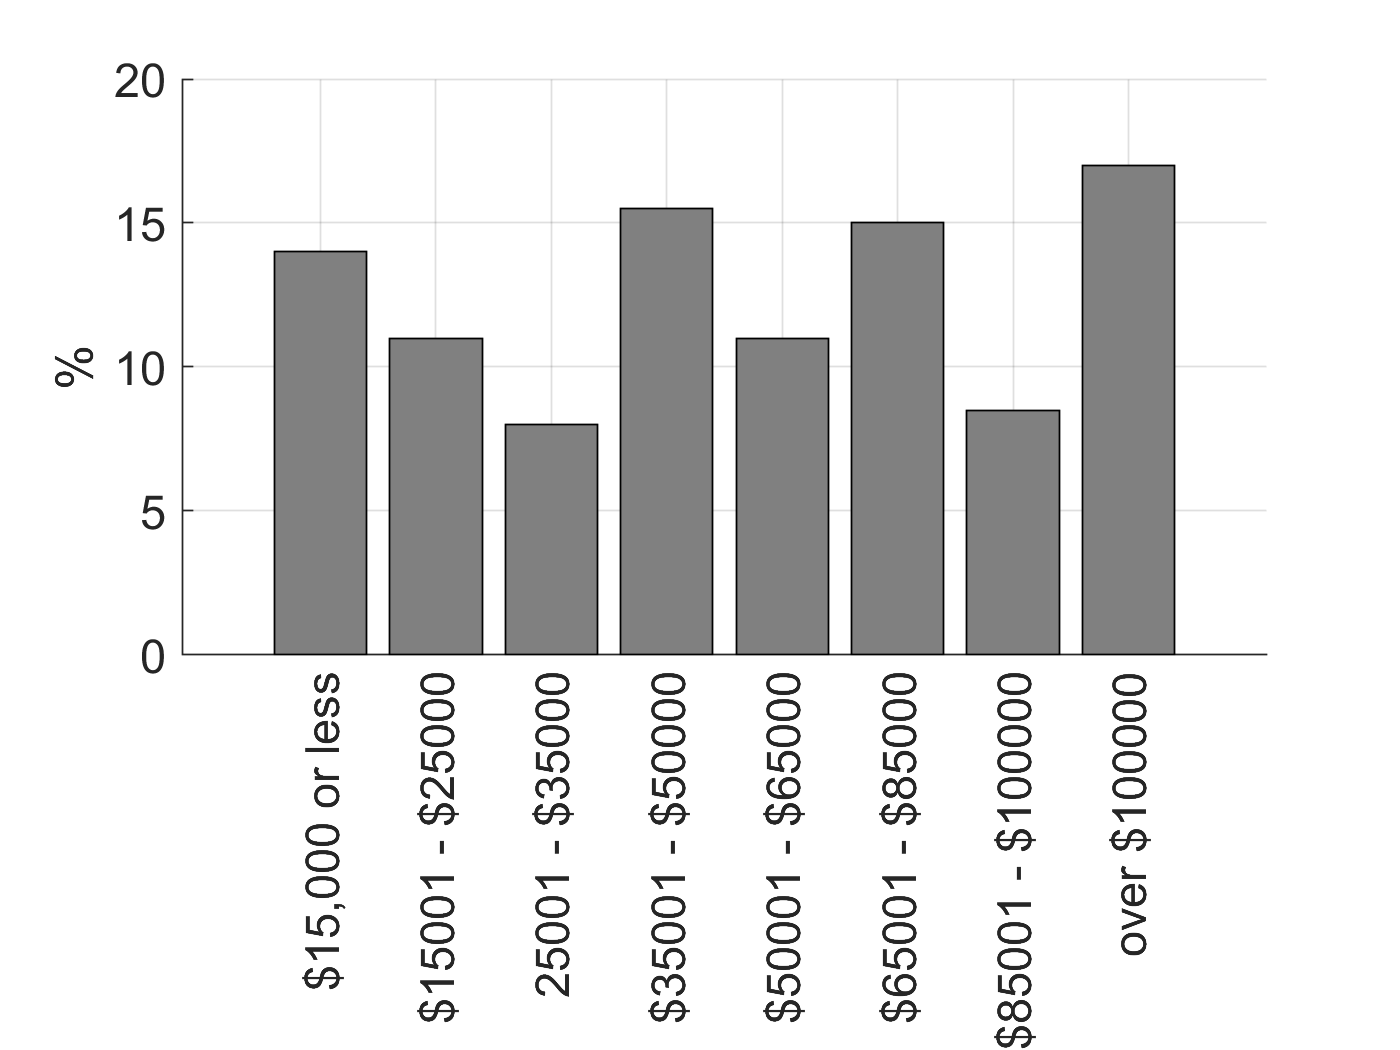



figure;hold on;
for i=1:8
    matStats.dem.income(i) = mean(dataTP1(:,4)==i);
    bar(i,matStats.dem.income(i).*100,'FaceColor',[.5 .5 .5]);grid on;box off;
end
labels = {"$15,000 or less","$15001 - $25000","25001 - $35000",...
    "$35001 - $50000","$50001 - $65000" ,...
    "$65001 - $85000","$85001 - $100000" ,"over $100000"} ;
ylabel('%')
set(gca,'XTick',1:8,'XTickLabel',labels,'XTickLabelRotation',90,'FontSize',14);

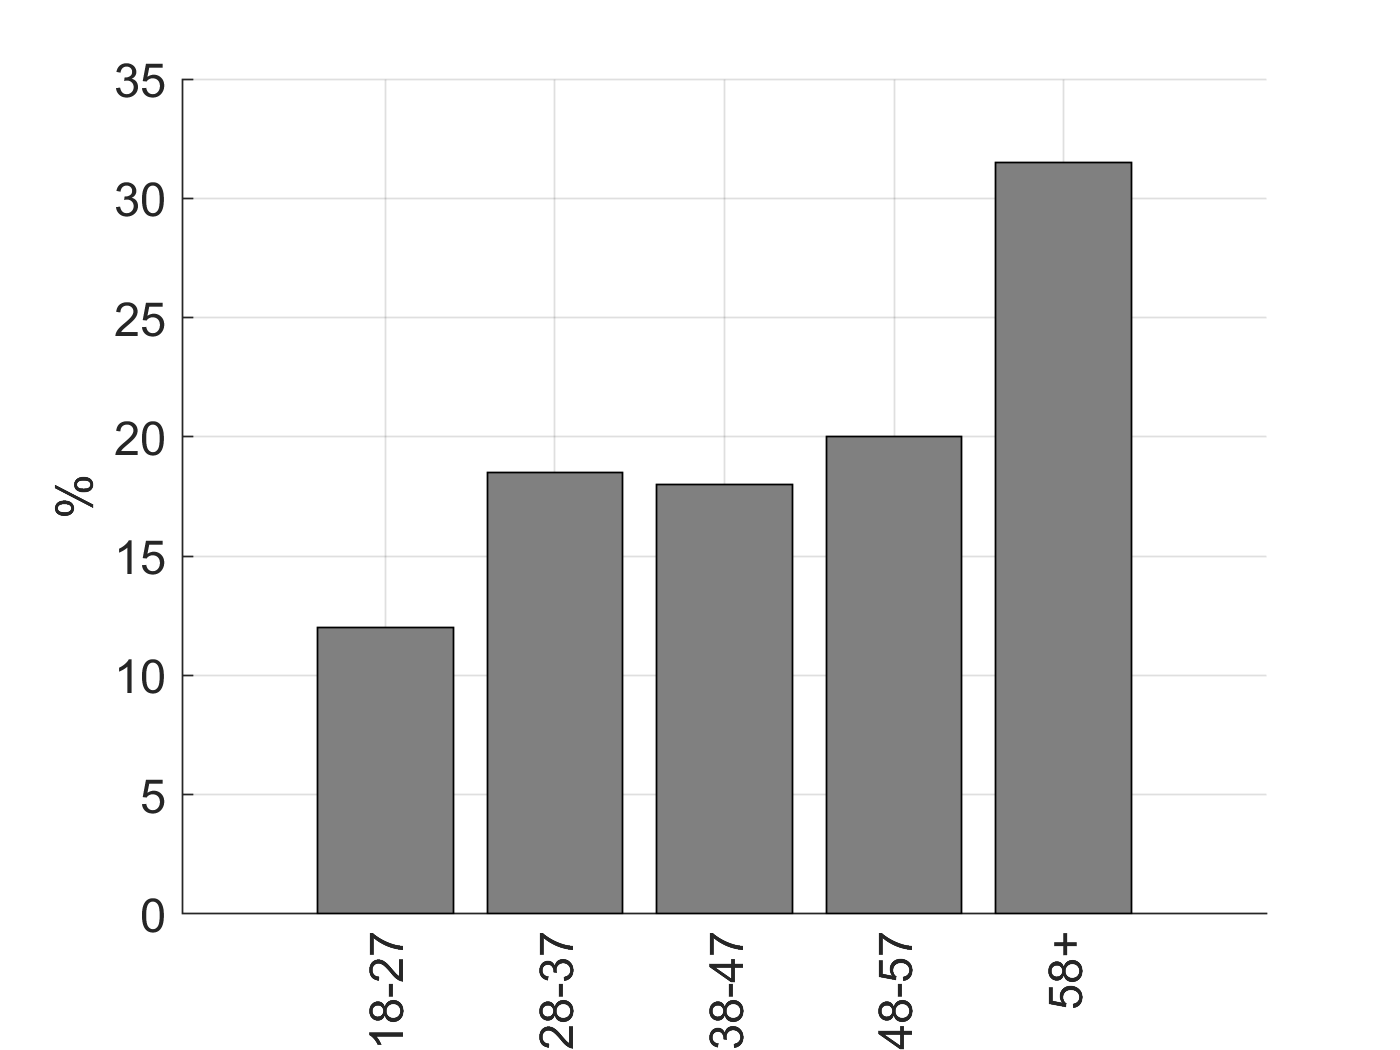



matStats.dem.age(1) = sum(dataTP1(:,1)>=18 & dataTP1(:,1)<=27)/size(dataTP1(:,1),1);
matStats.dem.age(2) = sum(dataTP1(:,1)>=28 & dataTP1(:,1)<=37)/size(dataTP1(:,1),1);
matStats.dem.age(3) = sum(dataTP1(:,1)>=38 & dataTP1(:,1)<=47)/size(dataTP1(:,1),1);
matStats.dem.age(4) = sum(dataTP1(:,1)>=48 & dataTP1(:,1)<=57)/size(dataTP1(:,1),1);
matStats.dem.age(5) = sum(dataTP1(:,1)>=58)/size(dataTP1(:,1),1);
matStats.dem.ageMeanSD = [mean(dataTP1(:,1)) std(dataTP1(:,1))];
figure;hold on;
for i=1:5
    bar(i,matStats.dem.age(i).*100,'FaceColor',[.5 .5 .5]);grid on;box off;
end
labels = {"18-27","28-37","38-47","48-57","58+"} ;
ylabel('%')
set(gca,'XTick',1:5,'XTickLabel',labels,'XTickLabelRotation',90,'FontSize',14)

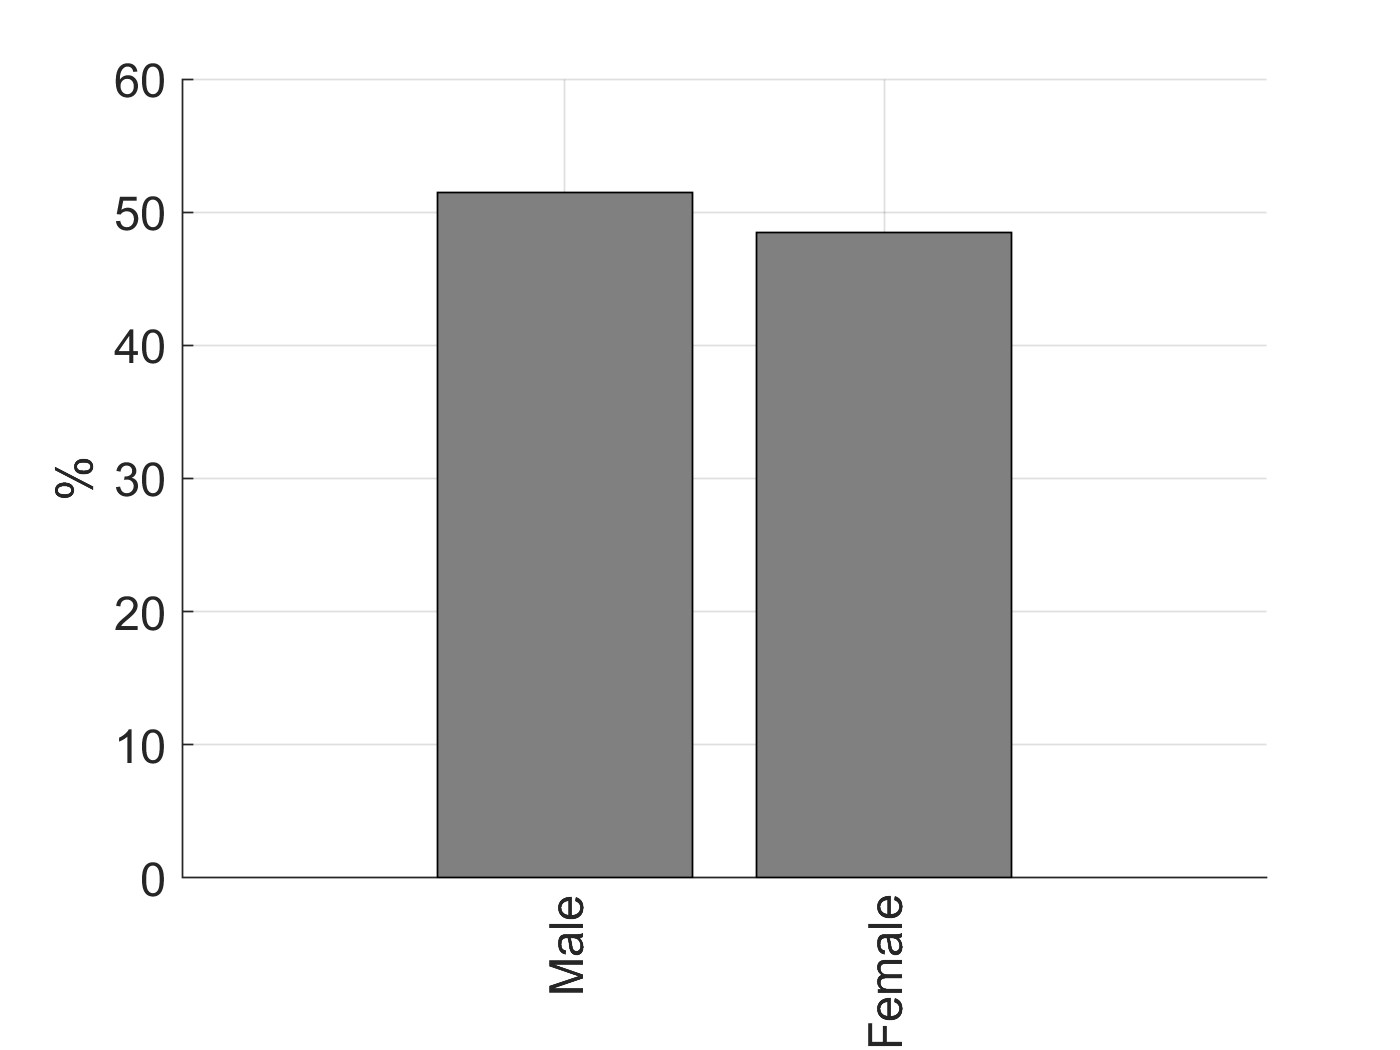


matStats.dem.gender = [mean(dataTP1(:,2)==1) mean(dataTP1(:,2)==2)];
figure;hold on;
for i=1:2
    bar(i,matStats.dem.gender(i).*100,'FaceColor',[.5 .5 .5]);grid on;box off;
end
labels = {"Male","Female"};
ylabel('%')
set(gca,'XTick',1:2,'XTickLabel',labels,'XTickLabelRotation',90,'FontSize',14)


%% Income shock effect on delay discounting
%% income shock: 
incomeShockTP1 = dataTP1(income.sign<3,18);
incomeShockTP2 = income.shock(income.sign<3,1);
var2Table = [(mean(income.sign~=3))*100, sum(income.sign~=3)];
matStats.incomeShock.sign = array2table(var2Table);
matStats.incomeShock.sign.Properties.VariableNames = {'Proportion','Absolute'};
var2Table = [mean(dataTP1(income.sign<3,18)) median(dataTP1(income.sign<3,18)) std(dataTP1(income.sign<3,18))/sqrt(sum(income.sign<3));...
             mean(income.shock(income.sign<3,1)) median(income.shock(income.sign<3,1)) std(income.shock(income.sign<3,1))/sqrt(sum(income.sign<3))];
matStats.incomeShock.summary  = array2table(var2Table);       
matStats.incomeShock.summary.Properties.VariableNames = {'Mean','Median','SE'};
matStats.incomeShock.summary.Properties.RowNames= {'time1','time2'};

## **Supplementary figure 2. A. Income shock, whole dataset at time 1 (N = 1,145).** 

Distribution of the reported income shock on a scale from 1 (no income shock) via 3 (moderate income shock) to 6 (high income shock). The black vertical lines correspond to the median (M = 3). **B-E. Income shock in the data subset (N = 182)**. **B & C.**Distribution of the reported income shock on a scale from 1 (no income shock) via 3 (moderate income shock) to 6 (high income shock). The black vertical lines correspond to the median (M = 3). **D**. Temporal correlation of income shock across participants. Income shock at time I is represented on the x axis, while income shock at time II is represented on the y axis. Each dot represents the proportion of participants at the coordinates. The legend represents the sizes corresponding to the minimal, the median and the maximal frequency, respectively. Dashed line the equality line. **E**. average income shock decreased between each timepoint (March 2020 and June 2020 respectively). Error bars correspond to the standard error of the mean. **P<0.01

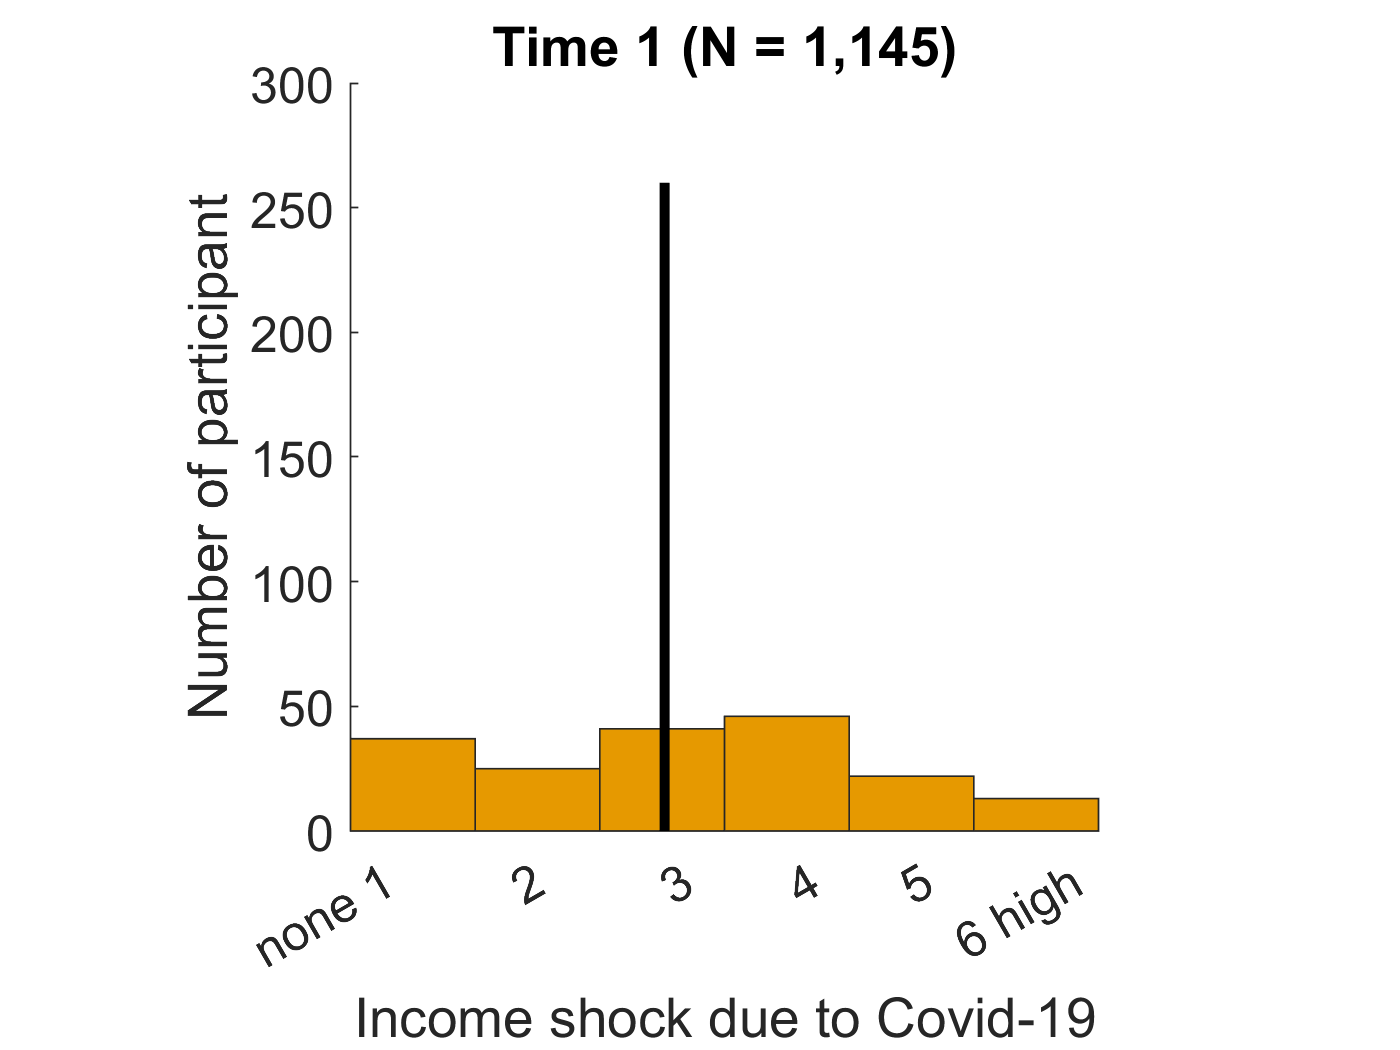

%%% Figure S2
incomeShockTP1 = dataTable_covid19US_raw{:,18};
figure;hold on;
hist(incomeShockTP1,6); h = findobj(gca,'Type','patch'); h.FaceColor = [0.9 0.6 0];
line(ones(1,261).*3.1,0:260,'Color',[0 0 0],'LineWidth',3);xlabel('Income shock due to Covid-19');ylabel('Number of participant');
set(gca,'XTick',[1.15:1:2.15 3.15 4 4.75 5.75],'XTickLabel',{'none 1','2','3','4','5','6 high'},'FontSize',15)
title('Time 1 (N = 1,145)')
axis square


% DELAY DISCOUNTING
for idem=1:size(demographics,2)
    demographics(:,idem) = zscore(demographics(:,idem));
end
M = zscore(mean(dataTable_covid19US{1:end,[10:1:12]},2));
y  = zscore(log(matestTP1(:,1)));
IV =  zscore(dataTable_covid19US_raw{:,18});
MIV = zscore(mean(dataTable_covid19US{1:end,[10:1:12]},2).*dataTable_covid19US_raw{:,18}); 
MIV2 = M.*IV; 

%% Supplementary figure 1 A & B
%% 1A
figure;hold on;
hist(dataTP1(income.sign<3,18),6); h = findobj(gca,'Type','patch'); h.FaceColor = [0.9 0.6 0];
median(dataTP1(income.sign<3,18))

ans = 3

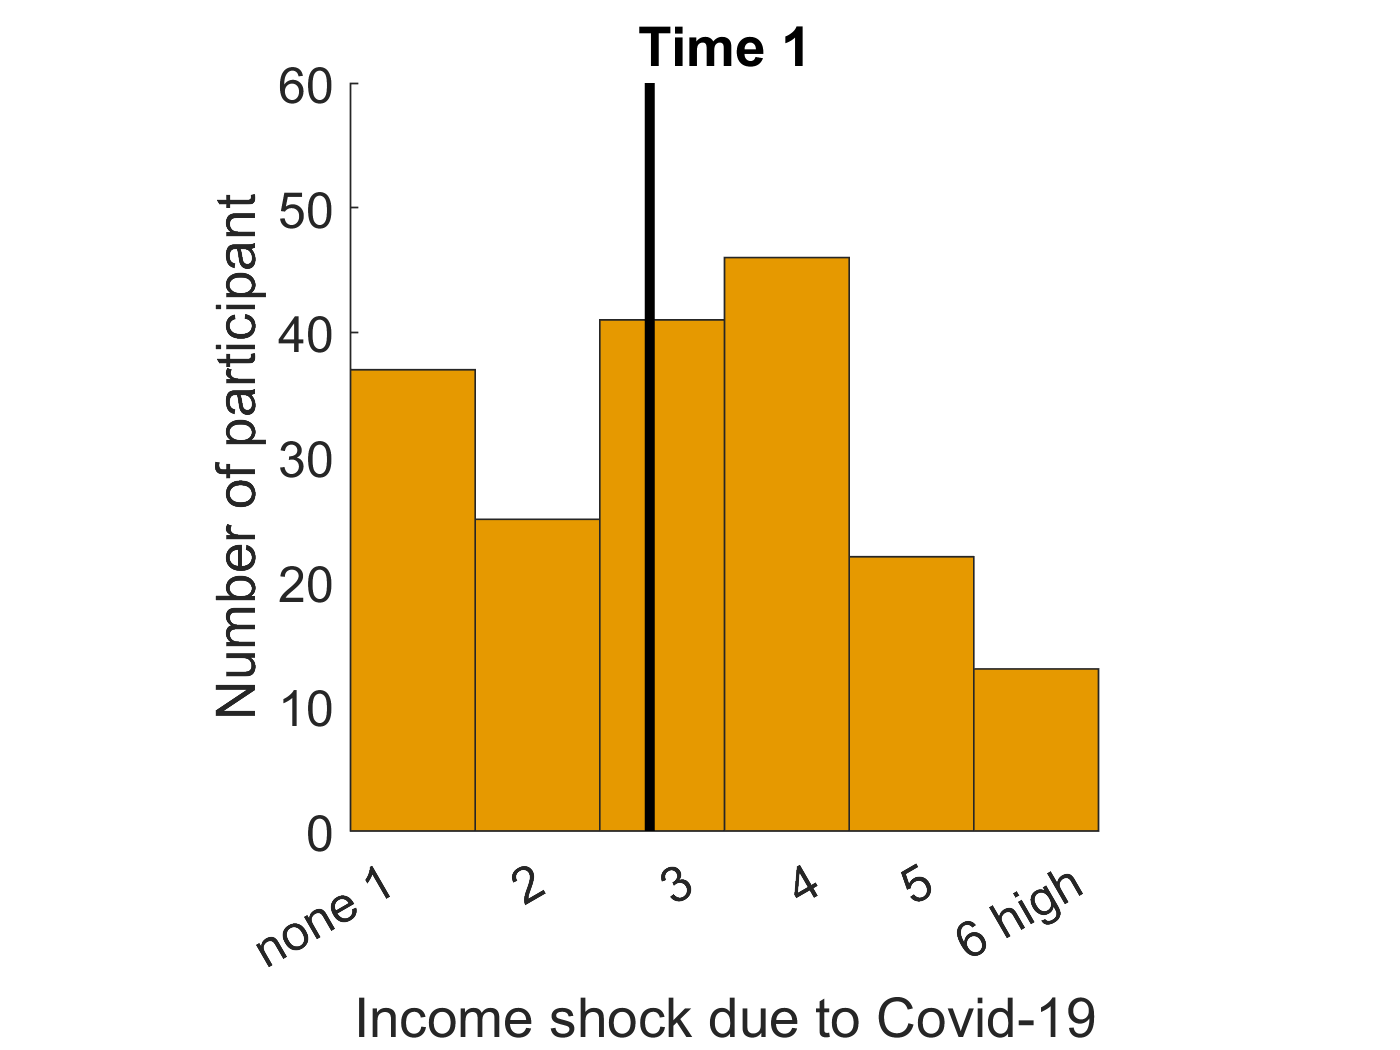

line(ones(1,61).*3,0:60,'Color',[0 0 0],'LineWidth',3);xlabel('Income shock due to Covid-19');ylabel('Number of participant');
set(gca,'XTick',[1.15:1:2.15 3.15 4 4.75 5.75],'XTickLabel',{'none 1','2','3','4','5','6 high'},'FontSize',15)
title('Time 1')
axis square

%% 1B
figure;hold on;
hist(income.shock(income.sign<3,1),6); h = findobj(gca,'Type','patch'); h.FaceColor = [0.9 0.6 0];
line(ones(1,61).*3.1,0:60,'Color',[0 0 0],'LineWidth',3);xlabel('Income shock due to Covid-19');ylabel('Number of participant');
set(gca,'XTick',[1.15:1:2.15 3.15 4 4.75 5.75],'XTickLabel',{'none 1','2','3','4','5','6 high'},'FontSize',15)
median(income.shock(income.sign<3,1))

ans = 3

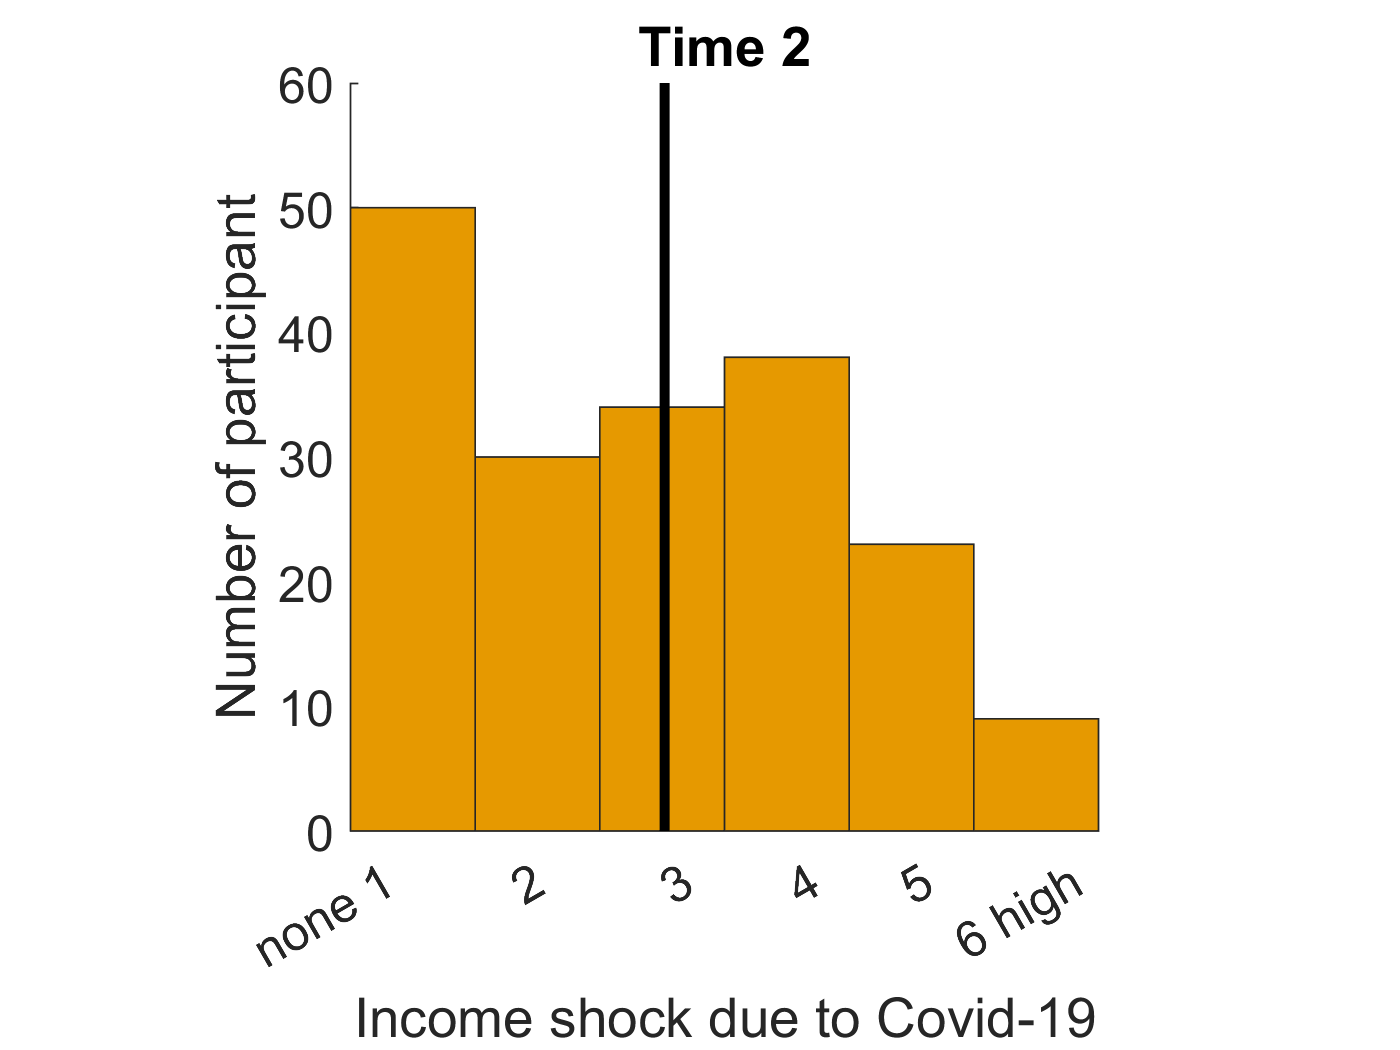

title('Time 2')
var2Table = [mean(dataTP1(income.sign<3,18)) median(dataTP1(income.sign<3,18)) std(dataTP1(income.sign<3,18))/sqrt(sum(income.sign<3));...
    mean(income.shock(income.sign<3,1)) median(income.shock(income.sign<3,1)) std(income.shock(income.sign<3,1))/sqrt(sum(income.sign<3))];
matStats.incomeShock.summary  = array2table(var2Table);
matStats.incomeShock.summary.Properties.VariableNames = {'Mean','Median','SE'};
matStats.incomeShock.summary.Properties.RowNames= {'time1','time2'};
axis square


%% 1C
figure;hold on;
XX = dataTP1(income.sign<3,18);
YY = income.shock(income.sign<3,1);
plot(1:1:6,1:1:6,'k--')
for i=1:size(XX,1)
        ISfreq(i)=sum(XX==XX(i) & YY==YY(i))/size(XX,1);
        lplot(i)=scatter(XX(i),YY(i),ISfreq(i)*1200,'MarkerFaceColor',[0.9 0.6 0],'MarkerEdgeColor',[0.9 0.6 0]);
end
idxMin = find(ISfreq==min(ISfreq));
idxMax = find(ISfreq==max(ISfreq));
idxMed = find(ISfreq==median(ISfreq));
xlabel('Income Shock at time 1')
ylabel('Income Shock at time 2')
set(gca,'XTick',[1:6],'XTickLabel',{'1','2','3','4','5','6(High)'},'YTick',[1:6],'YTickLabel',{'none 1','2','3','4','5','6 high'},'FontSize',15)
axis square
b = glmfit(XX,YY);
plot(XX,b(1) + b(2).*XX,'Color',[0.9 0.6 0])
l=legend([lplot(idxMin(1)),lplot(idxMed(1)),lplot(idxMax(1))],{num2str(round(ISfreq(idxMin(1)),3)),num2str(round(ISfreq(idxMed(1)),2)),num2str(round(ISfreq(idxMax(1)),2))});

l =   Legend (0.005, 0.04, 0.13) with properties:

         String: {'0.005'  '0.04'  '0.13'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 13.5000
       Position: [0.5931 0.7275 0.1718 0.1719]
          Units: 'normalized'

  Show all properties


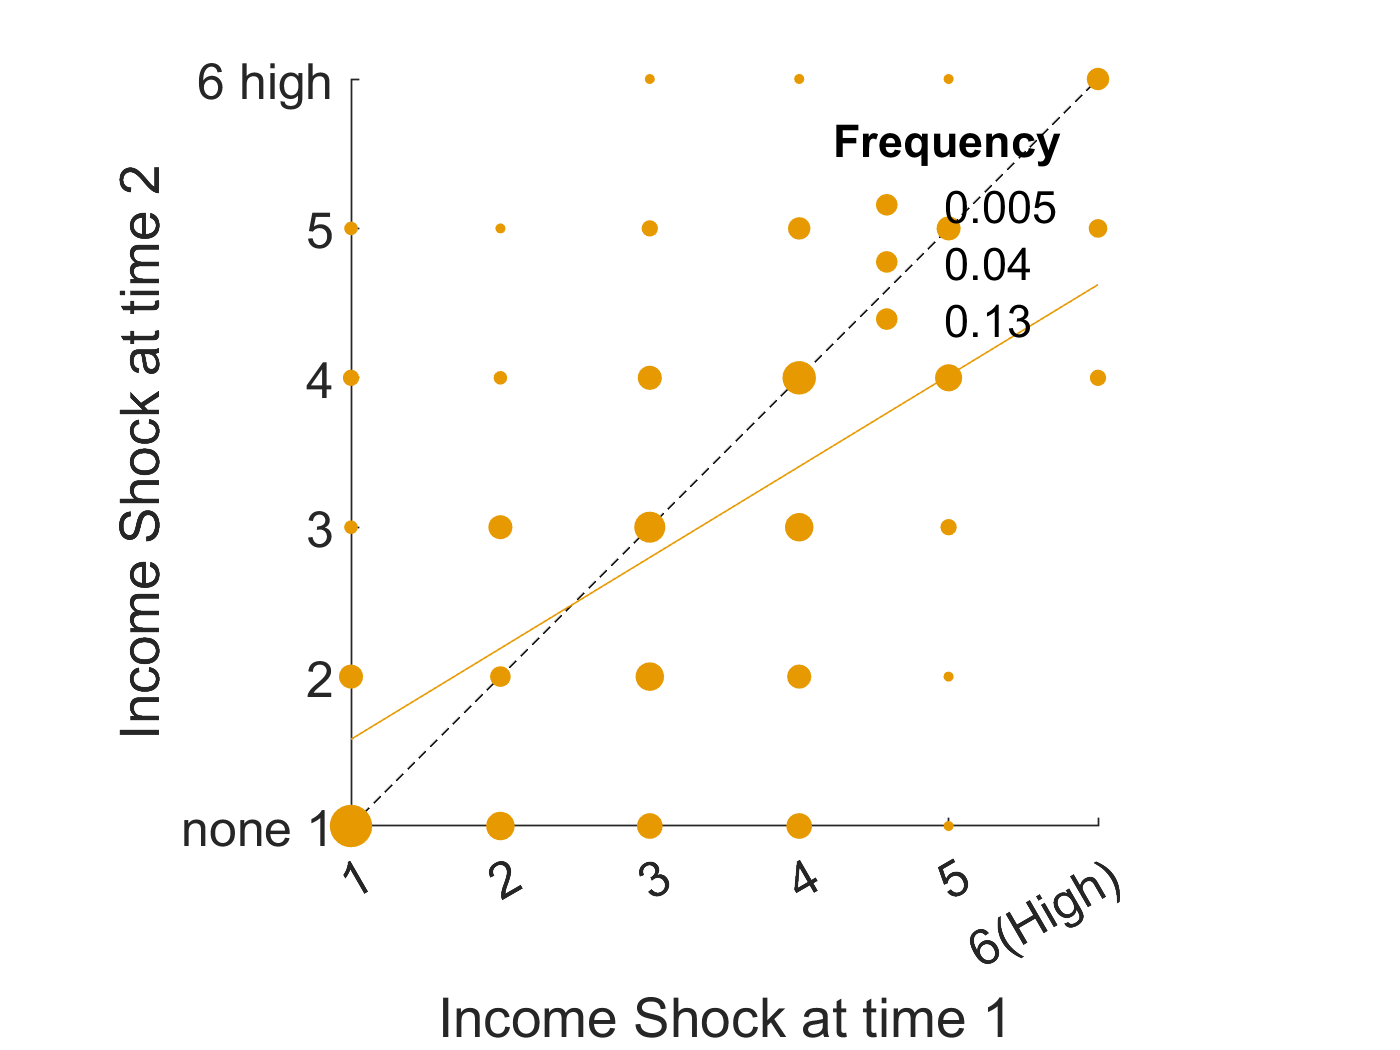

title(l,'Frequency')
legend boxoff

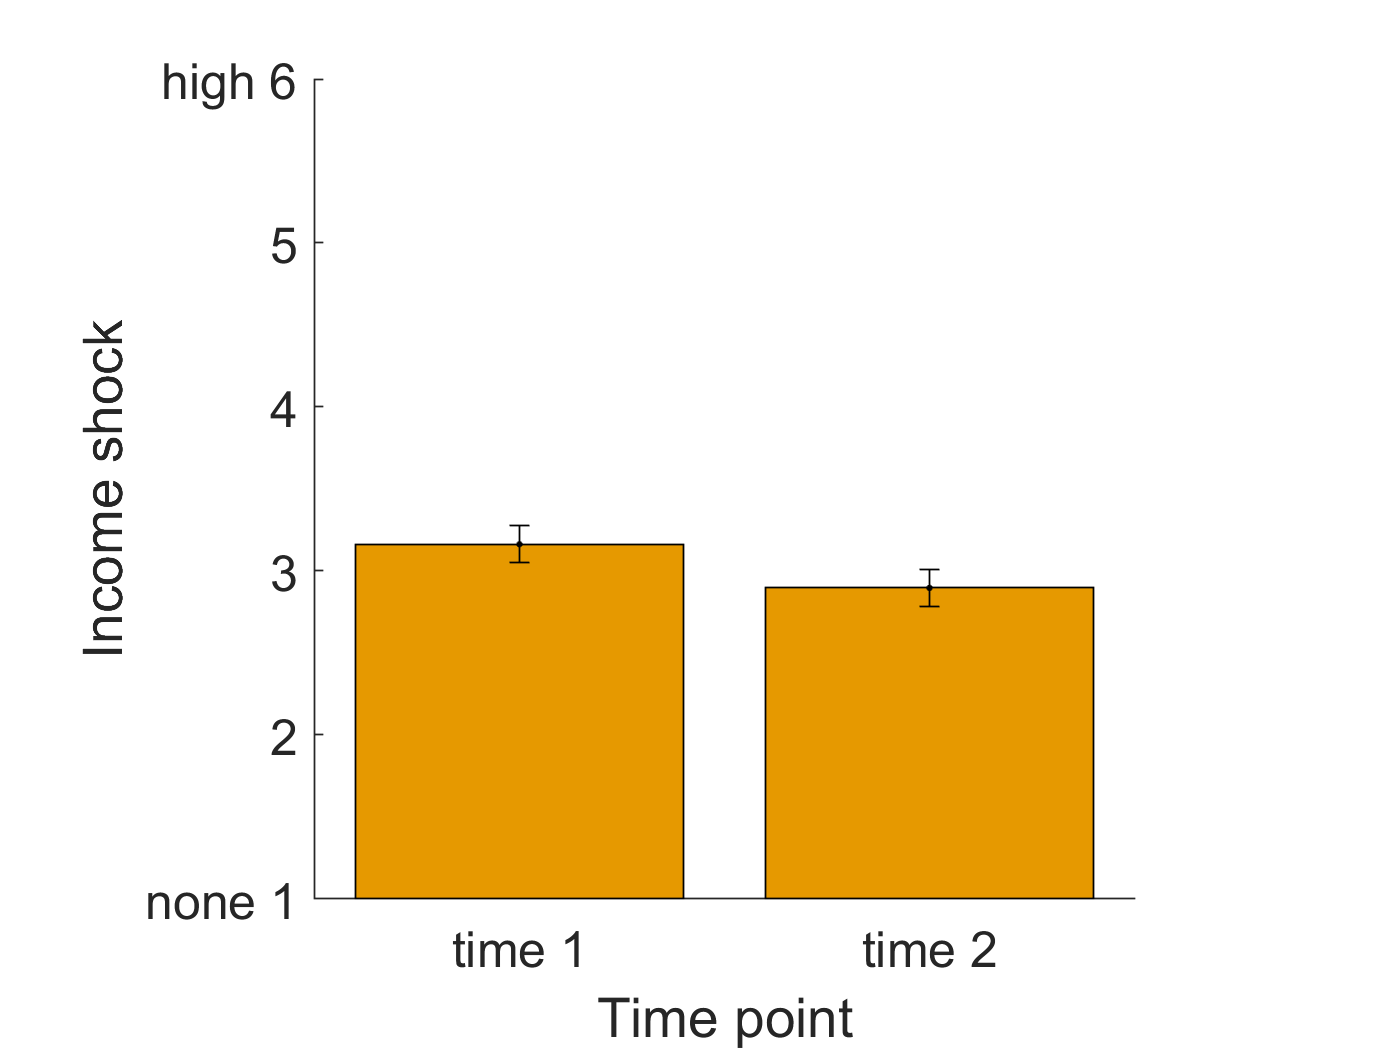

[rho3, p3] = corr(XX,YY);
var2Table = [rho3,p3];
matStats.incomeShock.corrTime = array2table(var2Table);
matStats.incomeShock.corrTime.Properties.VariableNames ={'rho','p'};

%% 1D
figure;
% subplot(2,3,6);
hold on;
XX = dataTP1(income.sign<3,18);
YY = income.shock(income.sign<3,1);
bar(nanmean([XX YY]),'FaceColor',[0.9 0.6 0])
errorbar(nanmean([XX YY]), nanstd([XX YY])./sqrt(size(XX,1)),'k.')
ylabel('Income shock')
xlabel('Time point')
set(gca,'XTick',1:2,'XTickLabel',{'time 1','time 2'})
ylim([1 6])
axis square
[h p c stats] = ttest(XX-YY);
diff = (XX-YY);
set(gca,'YTick',[1:6],'YTickLabel',{'none 1','2','3','4','5','high 6'},'FontSize',15)

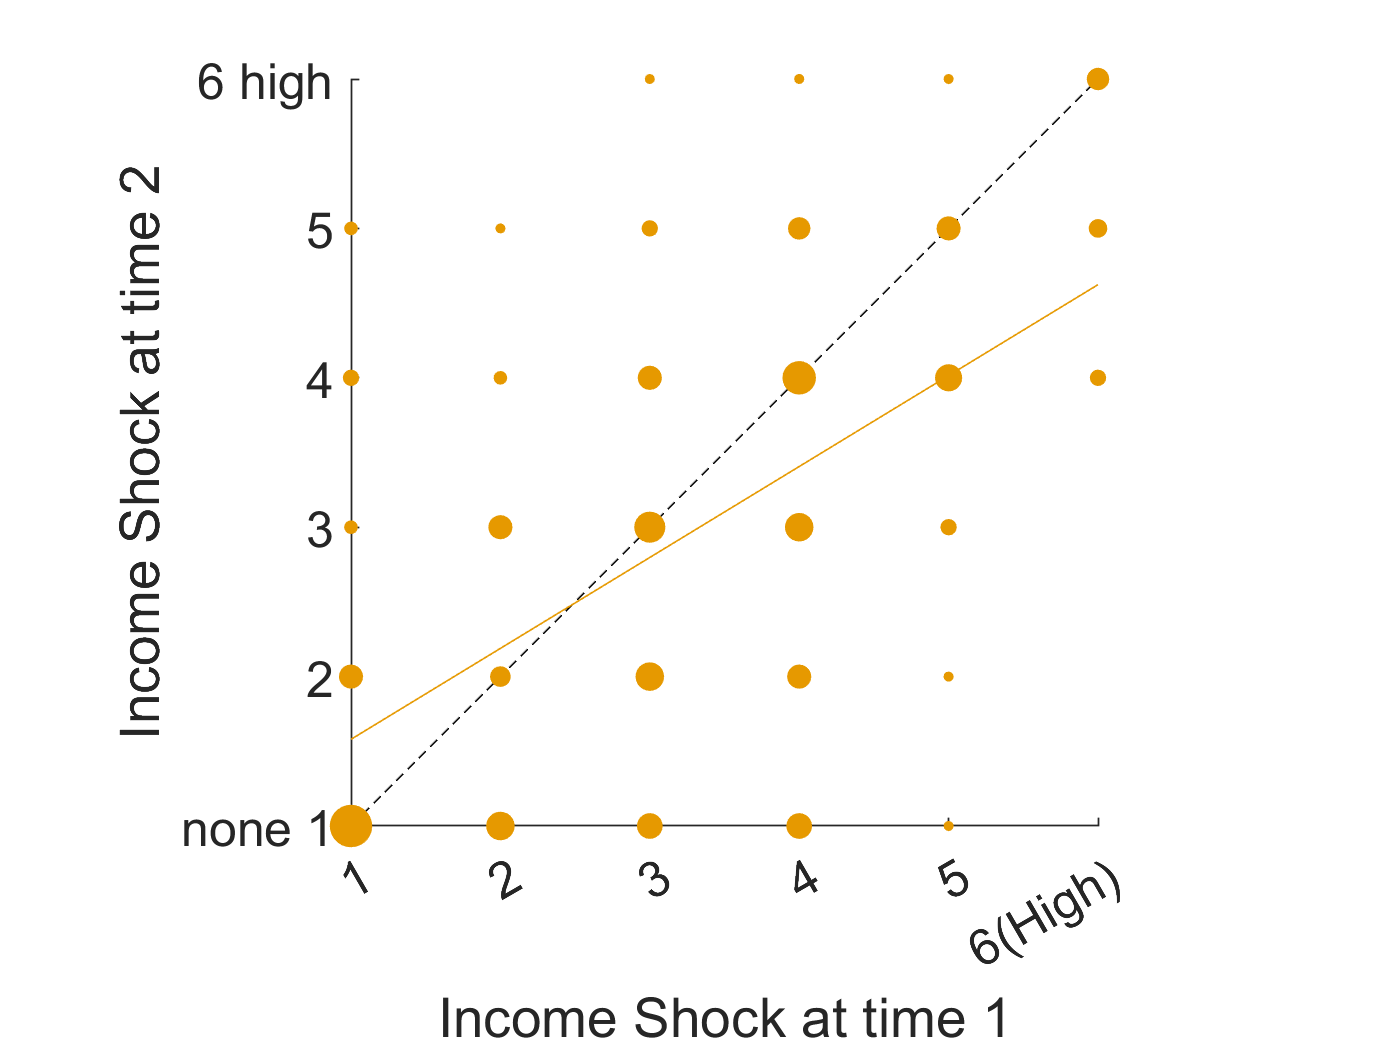

var2Table = [mean(XX),mean(YY),mean(diff),std(diff)/sqrt(size(diff,1)),stats.tstat,stats.df,p];
matStats.incomeShock.meanDiff = array2table(var2Table);
matStats.incomeShock.meanDiff.Properties.VariableNames ={'MeanTime1','MeanTime2','MeanDiff','SE','t','df','p'};

XX = incomeShockTP1;
YY = incomeShockTP2;
figure;hold on;
plot(1:1:6,1:1:6,'k--')
for i=1:size(XX,1)
        ISfreq(i)=sum(XX==XX(i) & YY==YY(i))/size(XX,1);
        lplot(i)=scatter(XX(i),YY(i),ISfreq(i)*1200,'MarkerFaceColor',[0.9 0.6 0],'MarkerEdgeColor',[0.9 0.6 0]);
end
idxMin = find(ISfreq==min(ISfreq));
idxMax = find(ISfreq==max(ISfreq));
idxMed = find(ISfreq==median(ISfreq));
xlabel('Income Shock at time 1')
ylabel('Income Shock at time 2')
set(gca,'XTick',[1:6],'XTickLabel',{'1','2','3','4','5','6(High)'},'YTick',[1:6],'YTickLabel',{'none 1','2','3','4','5','6 high'},'FontSize',15)
axis square
b = glmfit(XX,YY);
plot(XX,b(1) + b(2).*XX,'Color',[0.9 0.6 0])

% l=legend([lplot(idxMin(1)),lplot(idxMed(1)),lplot(idxMax(1))],{num2str(round(ISfreq(idxMin(1)),3)),num2str(round(ISfreq(idxMed(1)),2)),num2str(round(ISfreq(idxMax(1)),2))})
% title(l,'Frequency')
%legend boxoff
[rho3, p3] = corr(XX,YY);
var2Table = [rho3,p3];
matStats.incomeShock.corrTime = array2table(var2Table);
matStats.incomeShock.corrTime.Properties.VariableNames ={'rho','p'};
diff = (XX-YY);
[h p c stats] = ttest(diff);
var2Table = [mean(XX),mean(YY),mean(diff),std(diff)/sqrt(size(diff,1)),stats.tstat,stats.df,p];
matStats.incomeShock.meanDiff = array2table(var2Table);
matStats.incomeShock.meanDiff.Properties.VariableNames ={'MeanTime1','MeanTime2','MeanDiff','SE','t','df','p'};

## **Supplementary figure 3. Income shock is related to temporal discounting rates in the subset of participants at time I and time II.** 

The left panel corresponds to data collected at time I, and the right panel to data collected at time II. **A&B**: For illustration purposes participants were split to those experiencing high income shock in orange (that is those that reported income shock higher than 3, which is the middle of the scale) and low income shock in cyan (<3). Displayed are the proportion of trials in which participants selected the immediate reward over the delayed reward (Y axis) as a function of the days associated with the delayed reward. The orange line is above the cyan line indicating that those experiencing higher income shock were more likely to select immediate rewards over delayed rewards for the same delays.  The lines represent the prediction of the hyperbolic model and dots represent observed data. Error bars and shaded areas represents the standard error of the mean**. **

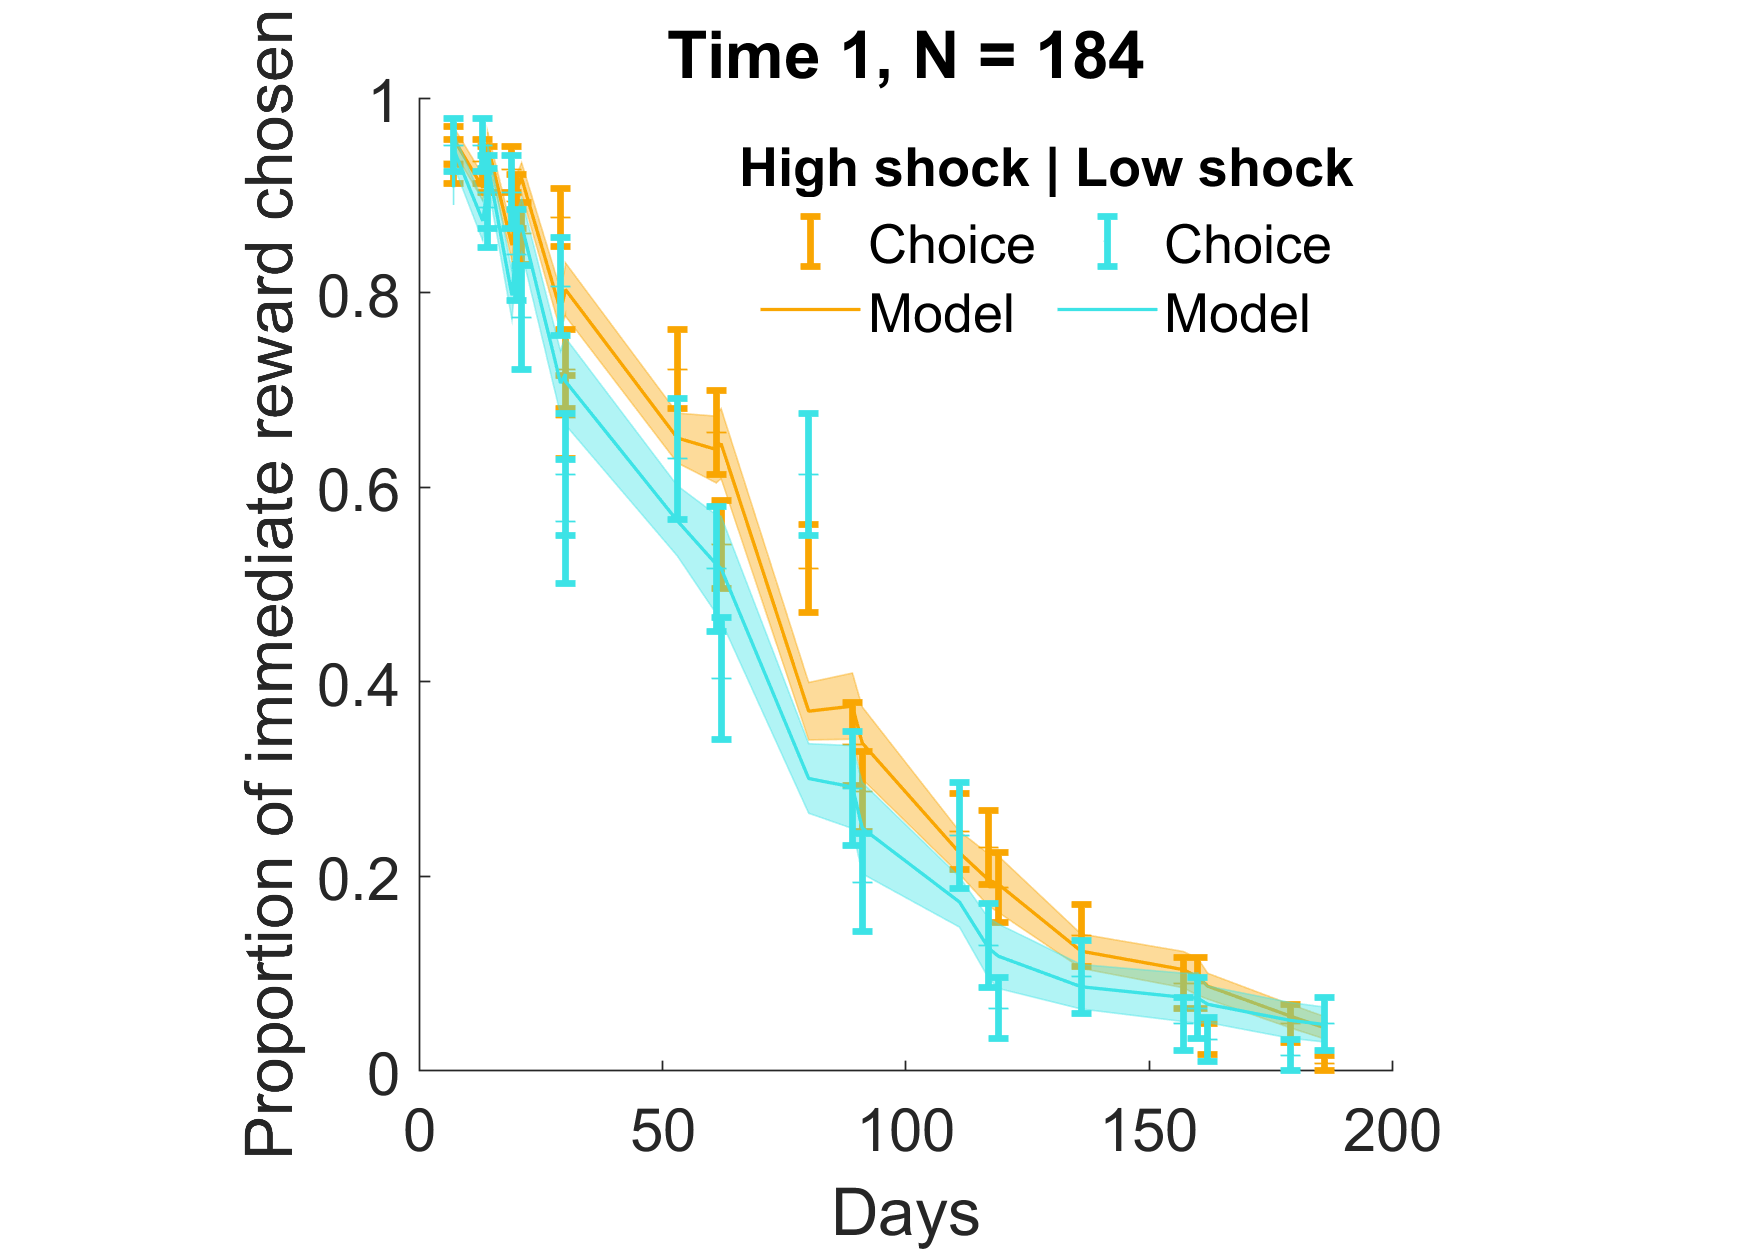

%% Time 1
%% Supplementary Figure 3A
figure('Renderer', 'painters', 'Position', [10 10 700 500]);    hold on;
for igroup=1:2
    if igroup==1
        ioi = dataTP1(:,18)>=3 & income.sign<3;
        lcolor = [249/255,166/255,2/255];
    else
        ioi =  dataTP1(:,18)<3 & income.sign<3;
        lcolor = [0.24 0.89 0.9];
    end    
    [ratioOrd] = sort(delay(2,:));%sort(log((rewardmag(2,:)./rewardmag(1,:)-1)./delay(2,:)));
    
    jbfill(ratioOrd,mean(matpredITC_sortedTP1(idxNewSample(ioi),:))+std(matpredITC_sortedTP1(idxNewSample(ioi),:))./sqrt(sum(ioi)),...
        mean(matpredITC_sortedTP1(idxNewSample(ioi),:))-std(matpredITC_sortedTP1(idxNewSample(ioi),:))./sqrt(sum((ioi))),...
        lcolor,lcolor,0,0.4);
     plot0{igroup} = plot(ratioOrd,mean(pImpSortedTP1(idxNewSample(ioi),:)),'+','Color',lcolor);
     plot1{igroup} = errorbar(ratioOrd,mean(pImpSortedTP1(idxNewSample(ioi),:)),std(pImpSortedTP1(idxNewSample(ioi),:))./sqrt(sum(ioi)),'.','Color',lcolor,'LineWidth',2);
     plot2{igroup} = plot(ratioOrd,mean(matpredITC_sortedTP1(idxNewSample(ioi),:)),'k','LineWidth',1,'Color',lcolor);
%     xlabel('log(delayed reward/Immediate reward)')
    xlabel('Days')
    ylabel('Proportion of immediate reward chosen')
    title('Time 1, N = 184')
    set(gca,'FontSize',18)
    %xlim([1,27])
    if igroup==2
        l = legend([plot1{1} plot2{1} plot1{2} plot2{2}],{'Choice','Model','Choice','Model'});
        l.NumColumns = 2;
        title(l,'High shock | Low shock')
        legend boxoff
    end
    axis square
end 

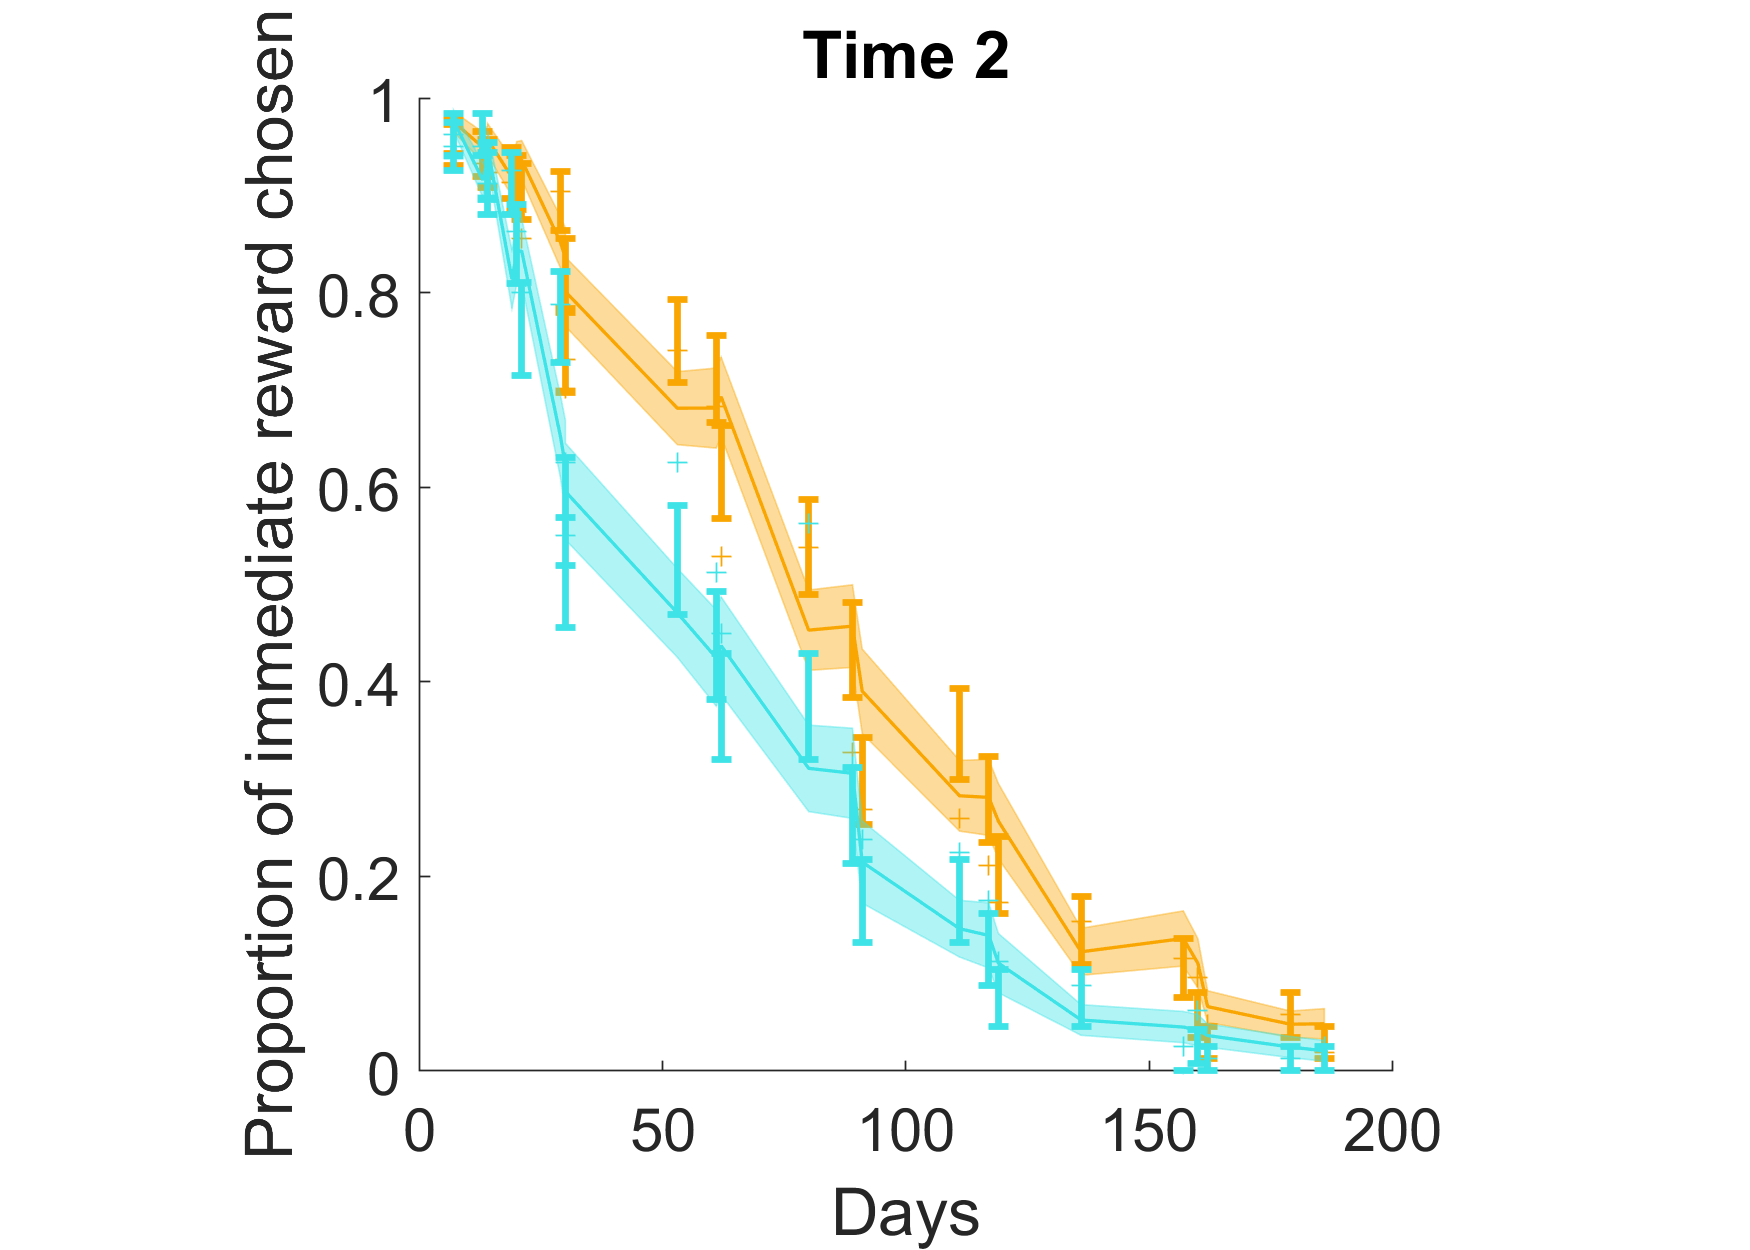

var2Table = [mean(matestTP1(idxNewSample(income.sign<3),[3])), std(matestTP1(idxNewSample(income.sign<3),[3]))/sqrt(size(matestTP1(idxNewSample(income.sign<3),:),1)),...
    mean(matestTP1(idxNewSample(income.sign<3),[4])), std(matestTP1(idxNewSample(income.sign<3),[4]))/sqrt(size(matestTP1(idxNewSample(income.sign<3),:),1))];
matStats.decision.ITC.fit = array2table(var2Table);
matStats.decision.ITC.fit.Properties.VariableNames = {'MeanR2','ESR2','MeanBacc','ESBacc'};
matStats.decision.ITC.fit.Properties.RowNames = {'time 1'};
var2Table = [nanmedian(log(matestTP1(idxNewSample(income.sign<3),1))) nanstd(log(matestTP1(idxNewSample(income.sign<3),1)))./sqrt(sum(income.sign<3))];
matStats.decision.ITC.k = array2table(var2Table);
matStats.decision.ITC.k.Properties.VariableNames = {'MedianK','ESK'};
matStats.decision.ITC.k.Properties.RowNames = {'time 1'};


for idem=1:size(demographics,2)
    demographics(:,idem) = zscore(demographics(:,idem));
end
y  = zscore(log(matestTP1(idxNewSample(income.sign<3),1)));
IV =  zscore(incomeShockTP1);
validata = ~isnan(y);
% income.Month(ioi,3) 
X =[demographics(idxNewSample(income.sign<3),:) IV];
Y = y;
[b,stats] = robustfit(X,y);stats.p(end);
% get full stats for IS
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.ITC.kISdem= array2table(var2Table);
matStats.decision.ITC.kISdem.Properties.VariableNames = {'beta','se','t','df','p'};
matStats.decision.ITC.kISdem.Properties.RowNames = {'time 1'};
% get the p-values for demographics, to report to the plot
var2Table = [stats.p(2:(end-1))'];
matStats.decision.ITC.kdem = array2table(var2Table);
matStats.decision.ITC.kdem.Properties.VariableNames = {'Age' 'Gender' 'Education' 'Income'};%{'Age' 'Gender' 'Education' 'Income' 'PoliticalOrientation' 'Ethnicity' 'Children' 'HealthInsurance' 'Restrictions'};
matStats.decision.ITC.kdem.Properties.RowNames = {'time 1'};


% store IS effect without controlling for demographics
[b,stats] = robustfit([IV],y);
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.ITC.kIS = array2table(var2Table);
matStats.decision.ITC.kIS.Properties.VariableNames = {'beta','se','t','df','p'};
matStats.decision.ITC.kIS.Properties.RowNames = {'time 1'};

%% Time 2
%% Supplementary figure 3 B
figure('Renderer', 'painters', 'Position', [10 10 700 500]);hold on;
for igroup=1:2
    if igroup==1
        ioi = income.shock>=3 & income.sign<3;% 
        lcolor = [249/255,166/255,2/255];
    else
        ioi =  income.shock<3 & income.sign<3;%
        lcolor = [0.24 0.89 0.9];
    end
    [ratioOrd] = sort(delay(2,:));%sort(log((rewardmag(2,:)./rewardmag(1,:)-1)./delay(2,:)));
    
    jbfill(ratioOrd,mean(matpredITC_sortedTP2((ioi),:))+std(matpredITC_sortedTP2((ioi),:))./sqrt(sum(ioi)),...
        mean(matpredITC_sortedTP2((ioi),:))-std(matpredITC_sortedTP2((ioi),:))./sqrt(sum((ioi))),...
        lcolor,lcolor,0,0.4);
    plot0{igroup} = plot(ratioOrd,mean(pImpSortedTP1(idxNewSample(ioi),:)),'+','Color',lcolor);
    plot1{igroup} = errorbar(ratioOrd,mean(pImpSortedTP2((ioi),:)),std(pImpSortedTP2((ioi),:))./sqrt(sum(ioi)),'.','Color',lcolor,'LineWidth',2);
    plot2{igroup} = plot(ratioOrd,mean(matpredITC_sortedTP2((ioi),:)),'k','LineWidth',1,'Color',lcolor);
    %     xlabel('Questions (sorted by the discouting rate they measure)')
    xlabel('Days');%('${\it} log([(delayed reward/immediate reward) - 1]/delay))$','Interpreter','Latex')
    ylabel('Proportion of immediate reward chosen')
    set(gca,'FontSize',18)
    title('Time 2')
%     xlim([1,27])
    if igroup==2
        l = legend([plot1{1} plot2{1} plot1{2} plot2{2}],{'Choice','Prediction','Choice','Prediction'});
        l.NumColumns = 2;
        title(l,'High shock | Low shock')
        legend boxoff
    end
    axis square
    legend off
end 

var2Table = [mean(matestTP2((income.sign<3),[3])), std(matestTP2((income.sign<3),[3]))/sqrt(size(matestTP2((income.sign<3),:),1)),...
    nanmean(matestTP2((income.sign<3),[4])), nanstd(matestTP2((income.sign<3),[4]))/sqrt(size(matestTP2((income.sign<3),:),1))];
matStats.decision.ITC.fit(2,:) = array2table(var2Table);
matStats.decision.ITC.fit.Properties.RowNames = {'time 1','time 2'};

var2Table = [nanmedian(log(matestTP2((income.sign<3),1))) nanstd(log(matestTP2((income.sign<3),1)))./sqrt(sum(income.sign<3))];
matStats.decision.ITC.k(2,:) = array2table(var2Table);
matStats.decision.ITC.k.Properties.RowNames = {'time 1','time 2'};

demographics = dataTable_covid19US{idxNewSample(income.sign<3) ,{'Age' 'Gender' 'Education' 'Income'}};
for idem=1:size(demographics,2)
    demographics(:,idem) = zscore(demographics(:,idem));
end
y  = zscore(log(matestTP2((income.sign<3),1)));
IV =  zscore(incomeShockTP2);
% D = demographics(idx)
validata = ~isnan(y);

[b,stats] = robustfit([demographics IV],y);stats.p(5);
% get full stats for IS
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.ITC.kISdem(2,:) = array2table(var2Table);
matStats.decision.ITC.kISdem.Properties.RowNames = {'time 1','time 2'};
% get the p-values for demographics, to report to the plot
var2Table = [stats.p(2:(end-1))'];
matStats.decision.ITC.kdem(2,:) = array2table(var2Table);
matStats.decision.ITC.kdem.Properties.RowNames = {'time 1','time 2'};
[b,stats] = robustfit([IV],y);
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.ITC.kIS(2,:) = array2table(var2Table);
matStats.decision.ITC.kIS.Properties.RowNames = {'time 1','time 2'};

[rho p] = corr(log(matestTP1(idxNewSample(income.sign<3),1)),log(matestTP2((income.sign<3),1)));
matStats.decision.ITC.kCorrTP = array2table([rho p]);
matStats.decision.ITC.kCorrTP.Properties.VariableNames = {'rho','p'};

XX = log(matestTP1(idxNewSample(income.sign<3),1));
YY = log(matestTP2((income.sign<3),1));
% bar(nanmean([XX YY]),'FaceColor',[.5 .5 .5])
% errorbar(nanmean([XX YY]), nanstd([XX YY])./sqrt(size(XX,1)),'k.')
% ylabel('Log delay discounting rate')
% xlabel('Time point')
% set(gca,'XTick',1:2,'XTickLabel',{'time 1','time 2'},'FontSize',15)
% ylim([-5 -4])
% axis square
[h p c stats] = ttest(XX-YY);
diff = (XX-YY);
%set(gca,'YTick',[1:6],'YTickLabel',{'none 1','2','3','4','5','high 6'},'FontSize',15)
var2Table = [mean(XX),std(XX)/sqrt(size(XX,1)),mean(YY),std(YY)/sqrt(size(YY,1)),mean(diff),std(diff)/sqrt(size(diff,1)),stats.tstat,stats.df,p];
matStats.ITC.meanDiff = array2table(var2Table);
matStats.ITC.meanDiff.Properties.VariableNames ={'MeanTime1','SETime1','MeanTime2','SETime2','MeanDiff','SE','t','df','p'};

## **Supplementary figure 4. Affective states. **

**A, C, E:** Self-reported negative emotions for the whole dataset at time I (**A**), for the subsample at time I (**C**), and for the subsample at time II (**E**) are correlated with each other (all Spearman ρ are displayed, all p < 10-20). These were averaged, creating a single construct which we refer to as negative affective state. **B, D, F:** Distribution of negative affective state in the population for the whole dataset at time I (**B**), for the subsample at time I (**D**), and for the subsample at time II (**F**). The vertical black line corresponds to the median.** G**: Average negative affective state was reduced over time.  Error bars correspond to the standard error of the mean. **H**: Most participants experienced more negative affective states at time 1 than at time 2 although both were correlated, with approximately 70 participants who experienced no or almost no negative affective state at Time 2.  *****p < 10-14 

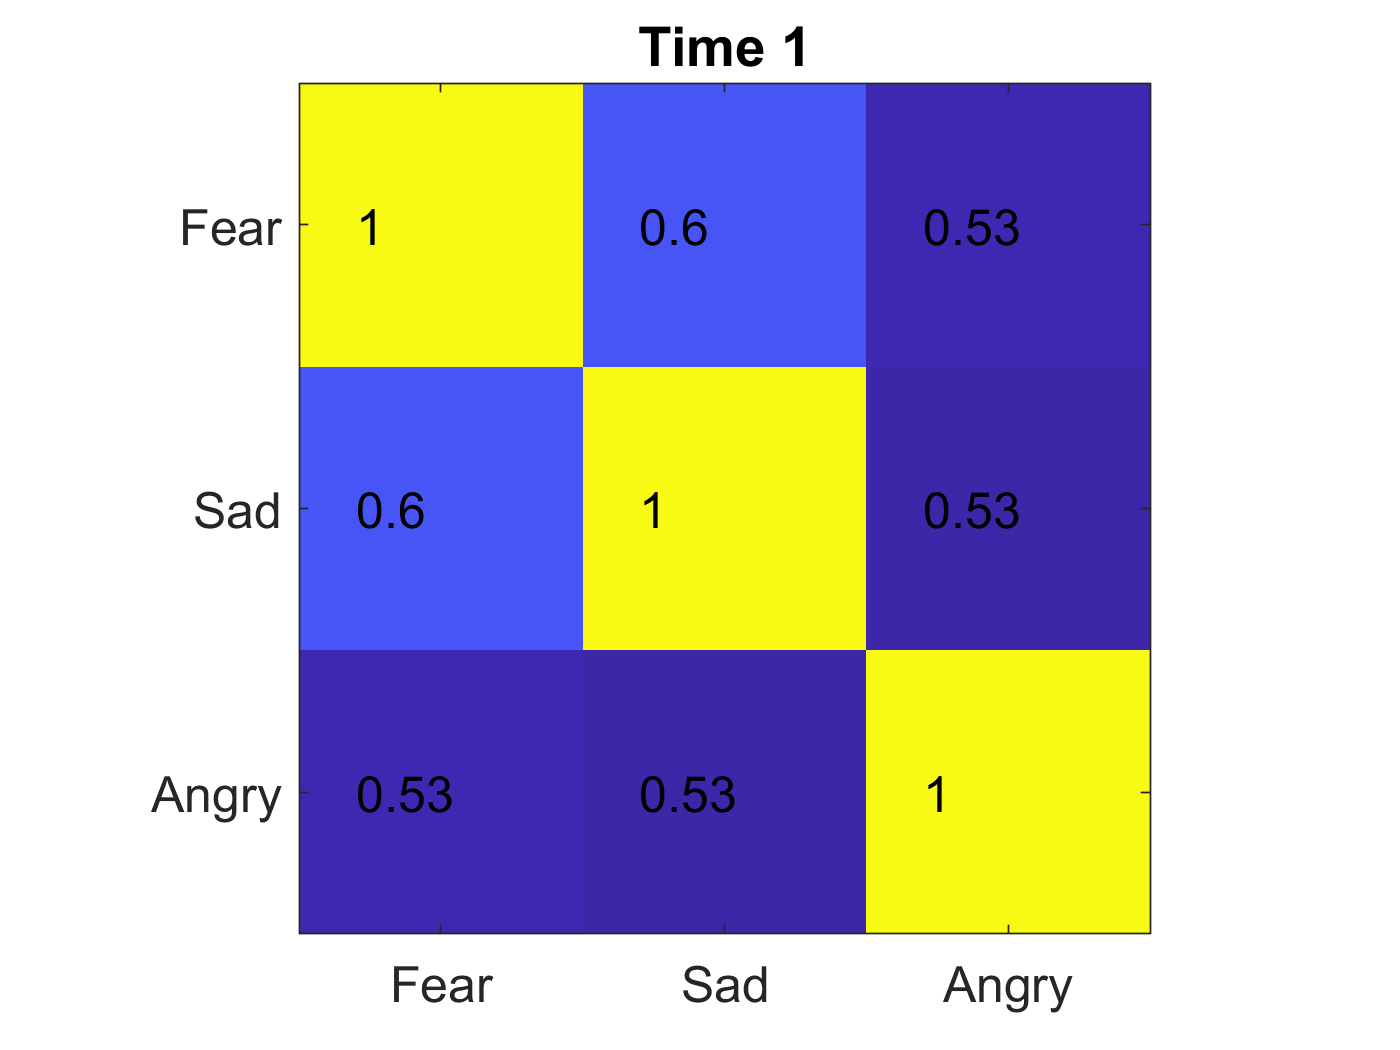

%%% EMOTIONS
rho1=[];
zz = table2array(dataTable_covid19US_raw(1:end,[10:1:12]));
XX = zz;
lnames = {'Fear' 'Sad' 'Angry'};%  'Hopeful' 'Joyful'};
for iEmotion = 1:3
    for jEmotion = 1:3
        [rho1(iEmotion,jEmotion), p1(iEmotion,jEmotion)] = corr(XX(:,iEmotion),XX(:,jEmotion),'type','Spearman');
    end
end

figure;imagesc(rho1);
for iEmotion = 1:3
    for jEmotion = 1:3
        text(iEmotion-0.3,jEmotion,num2str(round(rho1(iEmotion,jEmotion),2)),'FontSize',15)
    end
end
axis square
title('Time 1')
set(gca,'XTick',1:3,'XTickLabel',lnames,'YTick',1:3,'YTickLabel',lnames,'FontSize',15)

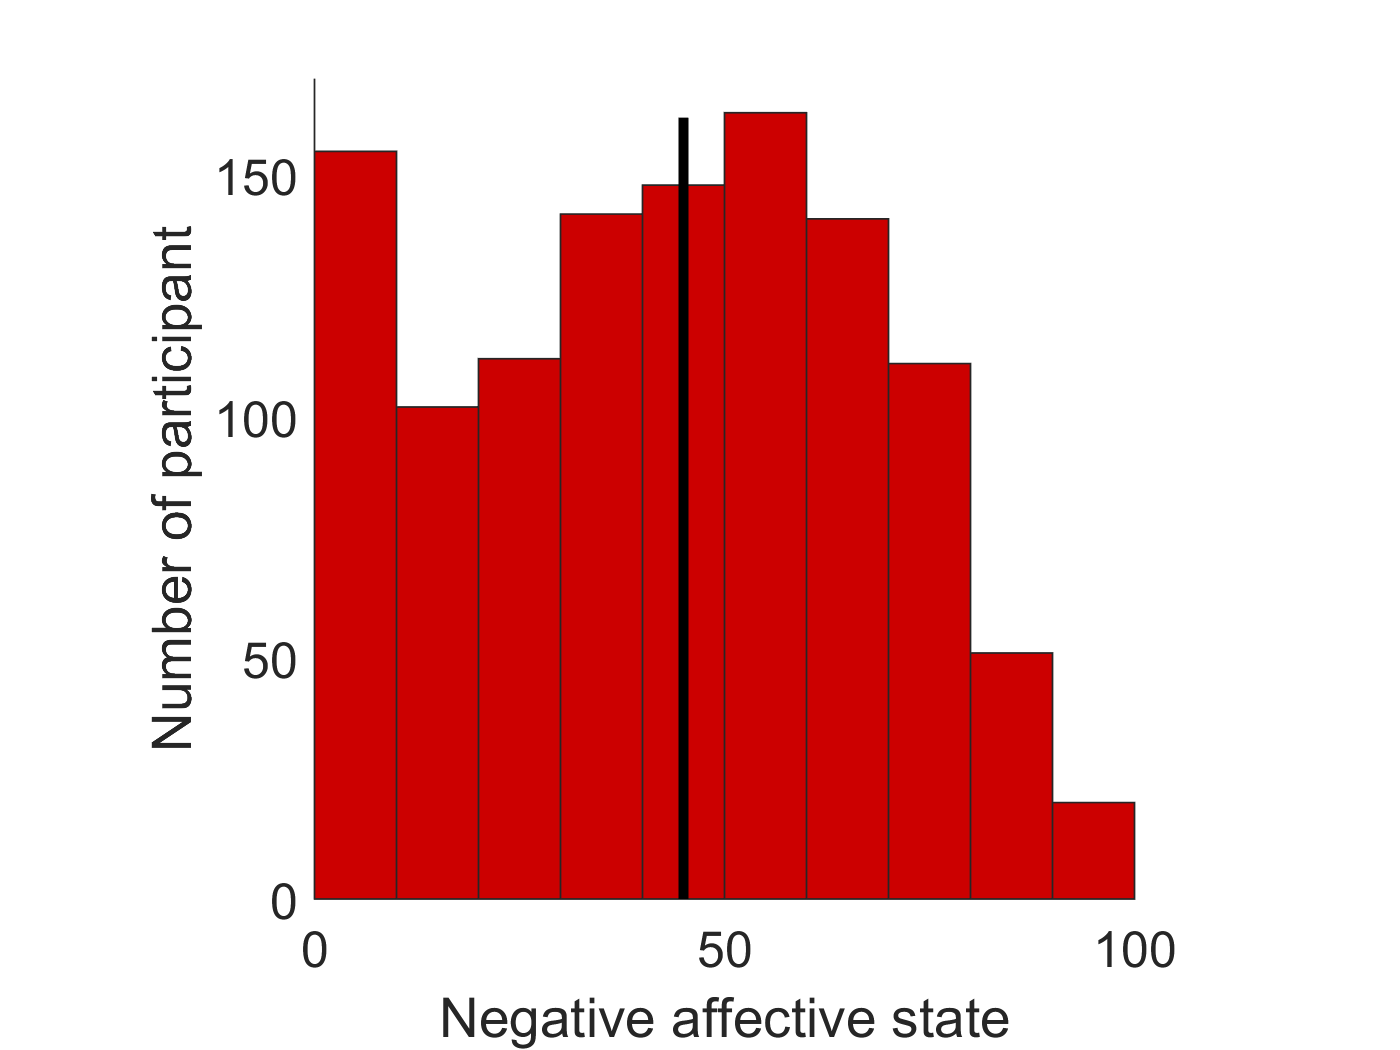


var2Table = [rho1];
matStats.emotion2AffectiveStates.rho= array2table(var2Table);
matStats.emotion2AffectiveStates.rho.Properties.VariableNames =lnames;
matStats.emotion2AffectiveStates.rho.Properties.RowNames =lnames;
var2Table = [p1];
matStats.emotion2AffectiveStates.p= array2table(var2Table);
matStats.emotion2AffectiveStates.p.Properties.VariableNames =lnames;
matStats.emotion2AffectiveStates.p.Properties.RowNames =lnames;

XX=mean(zz,2);
figure; hist(XX)
h = findobj(gca,'Type','patch'); h.FaceColor = [0.8 0 0];
line(ones(1,163).*median(XX),0:162,'Color',[0 0 0],'LineWidth',3);
xlabel('Negative affective state');
ylabel('Number of participant');
% title('Time 1')
set(gca,'FontSize',15,'XTick',0:50:100,'XTickLabels',{'0','50','100'})
xlim([0 100])
ylim([0 170])
axis square
box off

std((XX))./sqrt(sum(income.sign<3))

ans = 1.8621

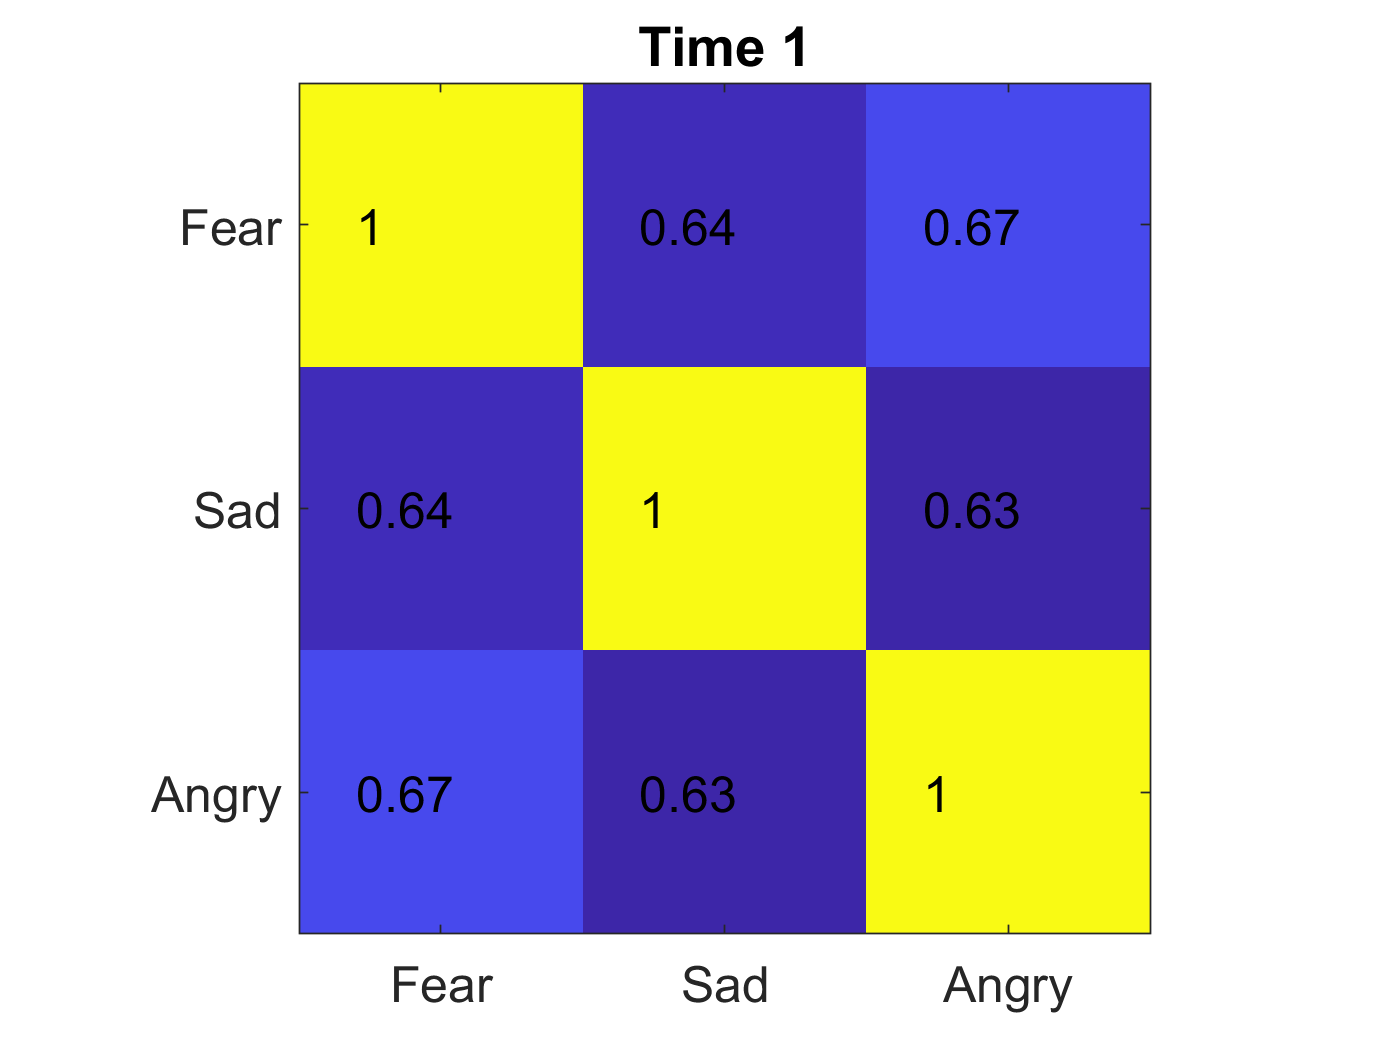


%% Supplementary figure 2 A
rho1=[];
XX = dataTP1(income.sign<3,[10:1:14]);
lnames = {'Fear' 'Sad' 'Angry'};%  'Hopeful' 'Joyful'};
for iEmotion = 1:3
    for jEmotion = 1:3
        [rho1(iEmotion,jEmotion), p1(iEmotion,jEmotion)] = corr(XX(:,iEmotion),XX(:,jEmotion),'type','Spearman');
    end
end

figure;imagesc(rho1);
for iEmotion = 1:3
    for jEmotion = 1:3
        text(iEmotion-0.3,jEmotion,num2str(round(rho1(iEmotion,jEmotion),2)),'FontSize',15)
    end
end
axis square
title('Time 1')
set(gca,'XTick',1:3,'XTickLabel',lnames,'YTick',1:3,'YTickLabel',lnames,'FontSize',15)

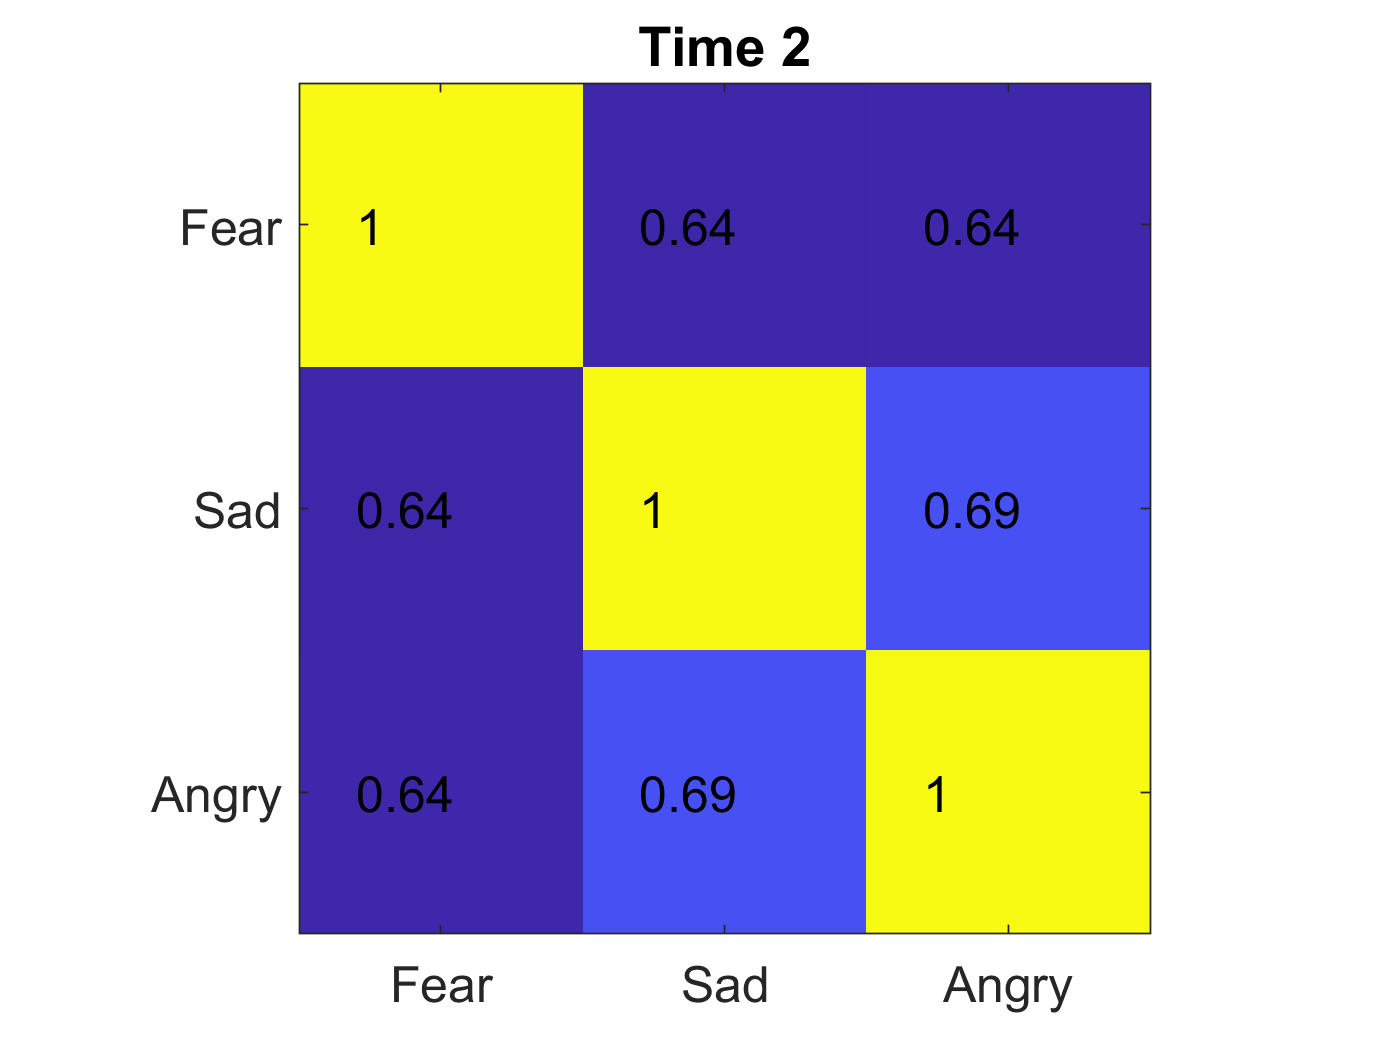


var2Table = [rho1];
matStats.emotion2AffectiveStates.rho= array2table(var2Table);
matStats.emotion2AffectiveStates.rho.Properties.VariableNames =lnames;
matStats.emotion2AffectiveStates.rho.Properties.RowNames =lnames;
var2Table = [p1];
matStats.emotion2AffectiveStates.p= array2table(var2Table);
matStats.emotion2AffectiveStates.p.Properties.VariableNames =lnames;
matStats.emotion2AffectiveStates.p.Properties.RowNames =lnames;

%% supplementary figure 2 B
XX = matemotion(income.sign<3,[1 4 5 2 3]);
lnames = {'Fear' 'Sad' 'Angry'};%  'Hopeful' 'Joyful'};
for iEmotion = 1:3
    for jEmotion = 1:3
        [rho1(iEmotion,jEmotion), p1(iEmotion,jEmotion)] = corr(XX(:,iEmotion),XX(:,jEmotion),'type','Spearman');
    end
end
figure;imagesc(rho1)
for iEmotion = 1:3
    for jEmotion = 1:3
        text(iEmotion-0.3,jEmotion,num2str(round(rho1(iEmotion,jEmotion),2)),'FontSize',15)
    end
end
axis square
title('Time 2')
set(gca,'XTick',1:3,'XTickLabel',lnames,'YTick',1:3,'YTickLabel',lnames,'FontSize',15)

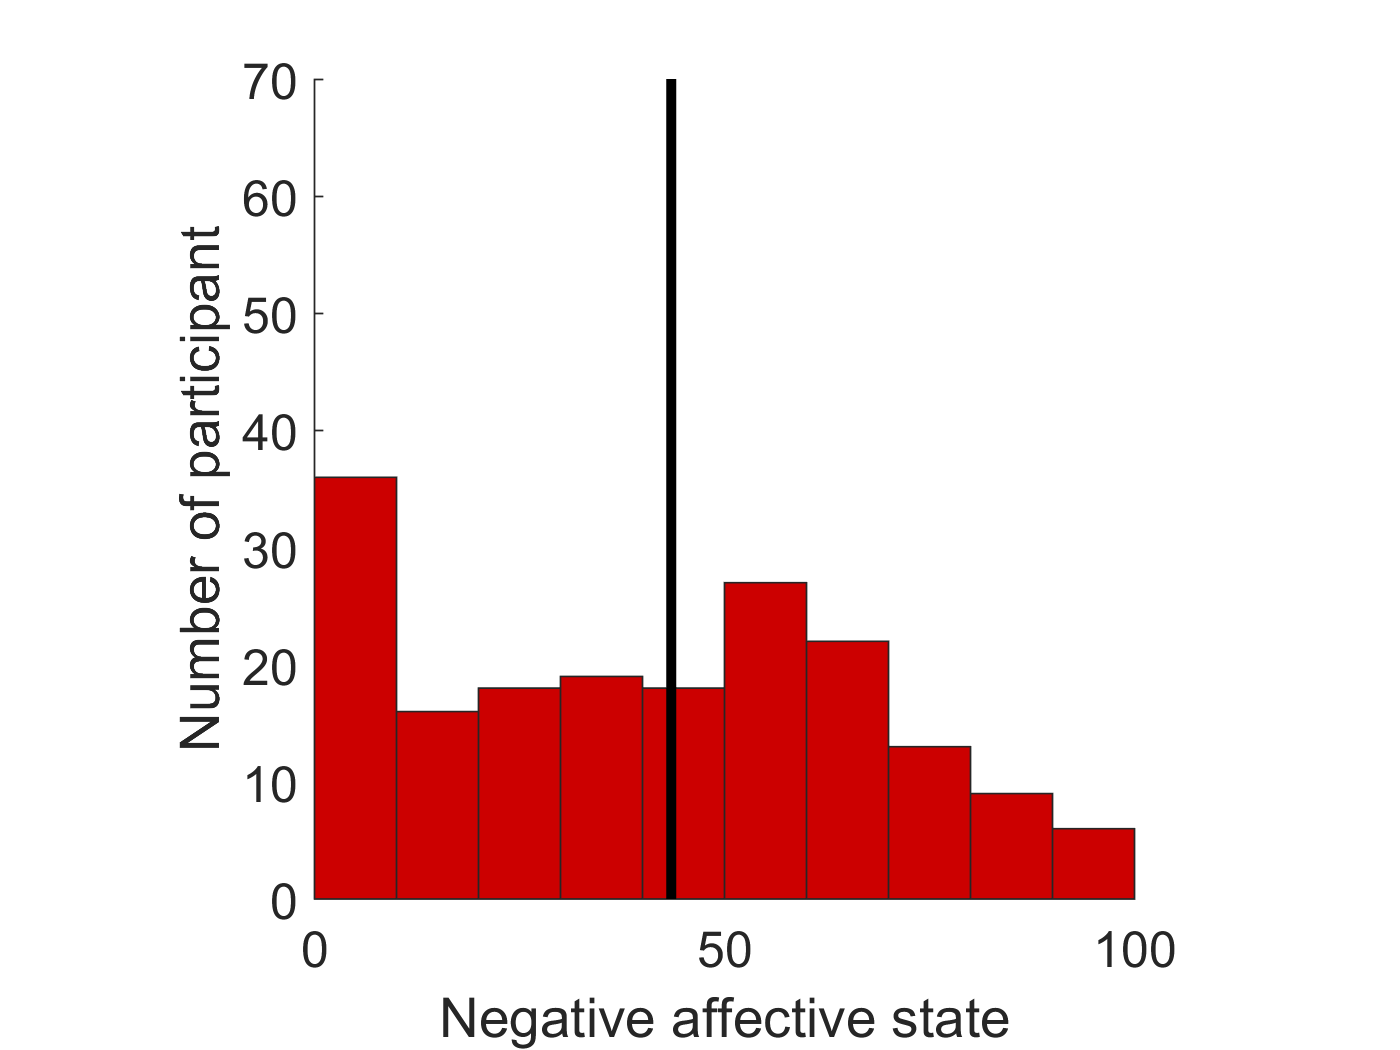

var2Table = [rho1];
matStats.emotion2AffectiveStates.rho2= array2table(var2Table);
matStats.emotion2AffectiveStates.rho2.Properties.VariableNames =lnames;
matStats.emotion2AffectiveStates.rho2.Properties.RowNames =lnames;
var2Table = [p1];
matStats.emotion2AffectiveStates.p2= array2table(var2Table);
matStats.emotion2AffectiveStates.p2.Properties.VariableNames =lnames;
matStats.emotion2AffectiveStates.p2.Properties.RowNames =lnames;

%% supplementary figure 3 C & D
XX=mean(dataTP1(income.sign<3,[10:1:12]),2);
figure; hist(XX)
h = findobj(gca,'Type','patch'); h.FaceColor = [0.8 0 0];
line(ones(1,71).*median(XX),0:70,'Color',[0 0 0],'LineWidth',3);
xlabel('Negative affective state');
ylabel('Number of participant');
% title('Time 1')
set(gca,'FontSize',15,'XTick',0:50:100,'XTickLabels',{'0','50','100'})
xlim([0 100])
ylim([0 70])
axis square
box off

std((XX))./sqrt(sum(income.sign<3))

ans = 2.0302



XX=mean(matemotion(income.sign<3,[1 4 5]),2);
figure; hist(XX)
h = findobj(gca,'Type','patch'); h.FaceColor = [0.8 0 0];
line(ones(1,71).*median(XX),0:70,'Color',[0 0 0],'LineWidth',3);
xlabel('Negative affective state');
ylabel('Number of participant');
%title('Time 2')
set(gca,'FontSize',15)
xlim([0 100])
ylim([0 70])
axis square
std((XX))./sqrt(sum(income.sign<3))

ans = 1.8397

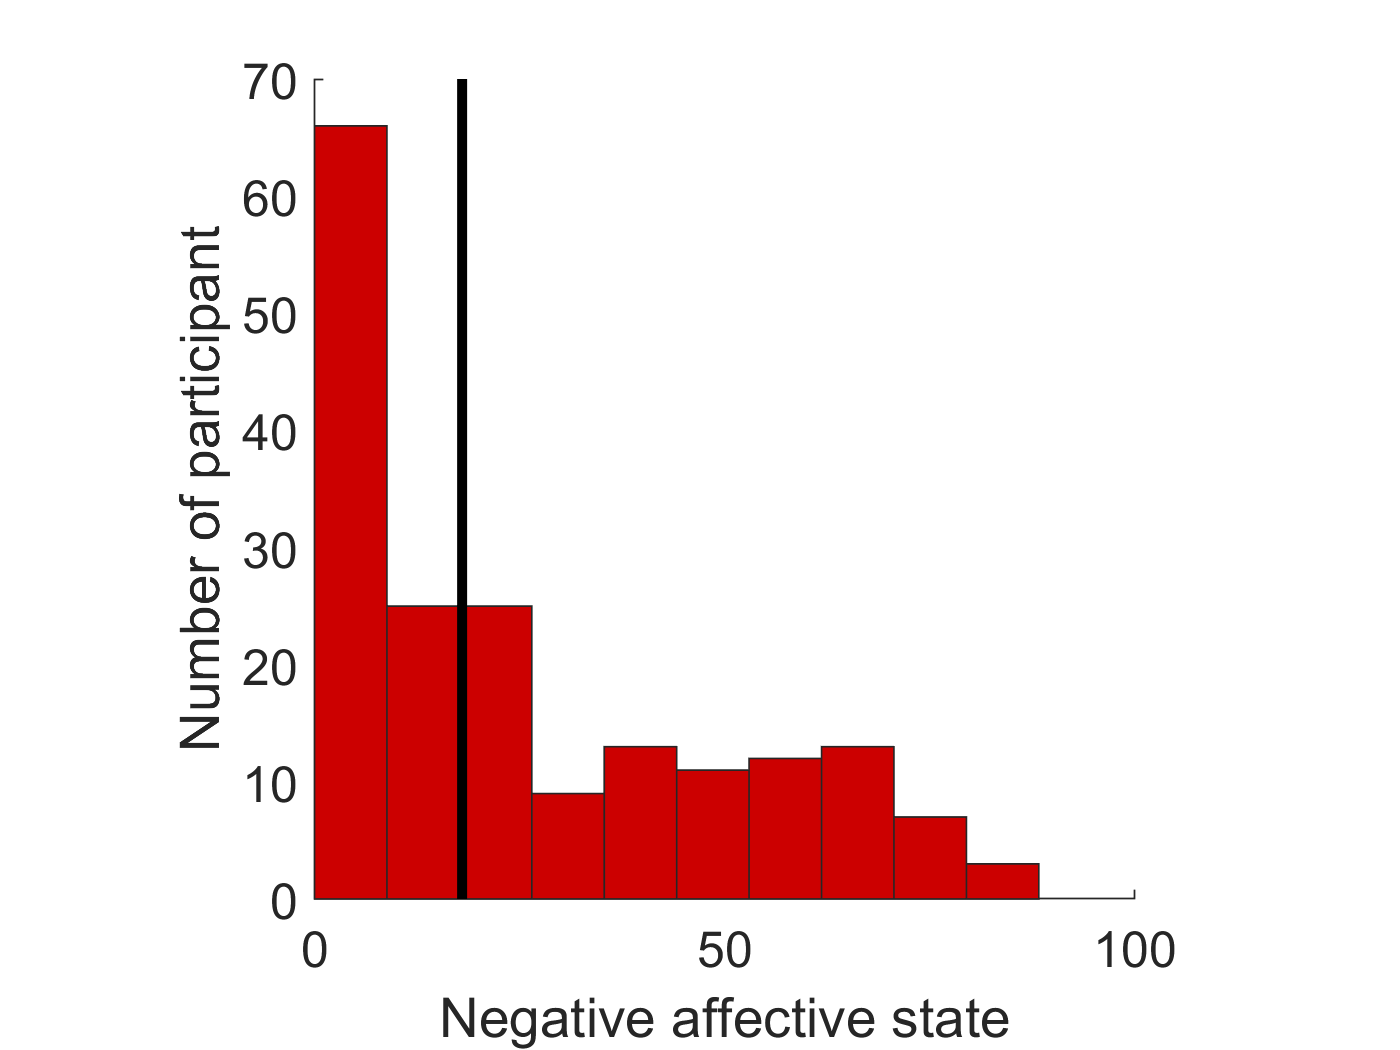

box off


%% Supplementary figure 3 E & F
%% change in negative affective states
%% Correlation between time 1 & time 2
XX = mean(dataTP1(income.sign<3,[10:1:12]),2);
YY = (mean(matemotion(income.sign<3,[1 4 5]),2));

%% S3E
figure;hold on;
plot(0:1:100,0:1:100,'--','Color',[.5 .5 .5])
scatter(XX,YY,40,'MarkerFaceColor',[0.8 0 0],'MarkerEdgeColor',[0.8 0 0],'MarkerFaceAlpha',.4,'MarkerEdgeAlpha',.4)
xlabel('Negative affective state at time 1')
ylabel('Negative affective state at time 2')
set(gca,'FontSize',15)
axis square
[rho p] = corr(XX,YY)

rho = 0.5741

p = 1.5969e-17

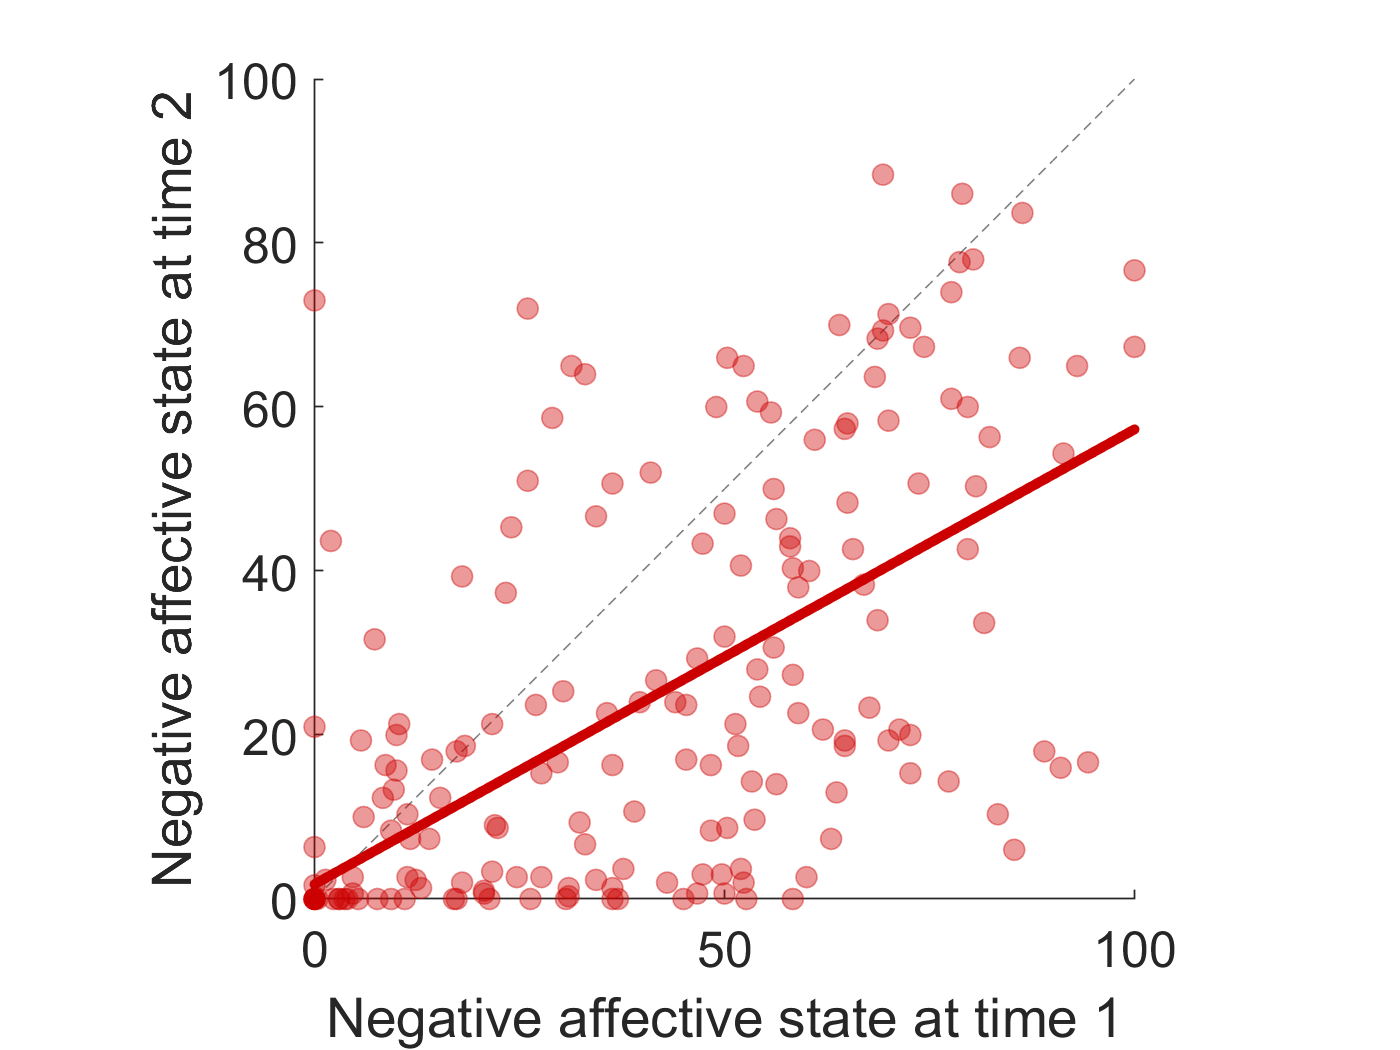


b = robustfit(XX,YY);
plot(XX,b(1)+XX.*b(2),'Color',[0.8 0 0],'LineWidth',3)

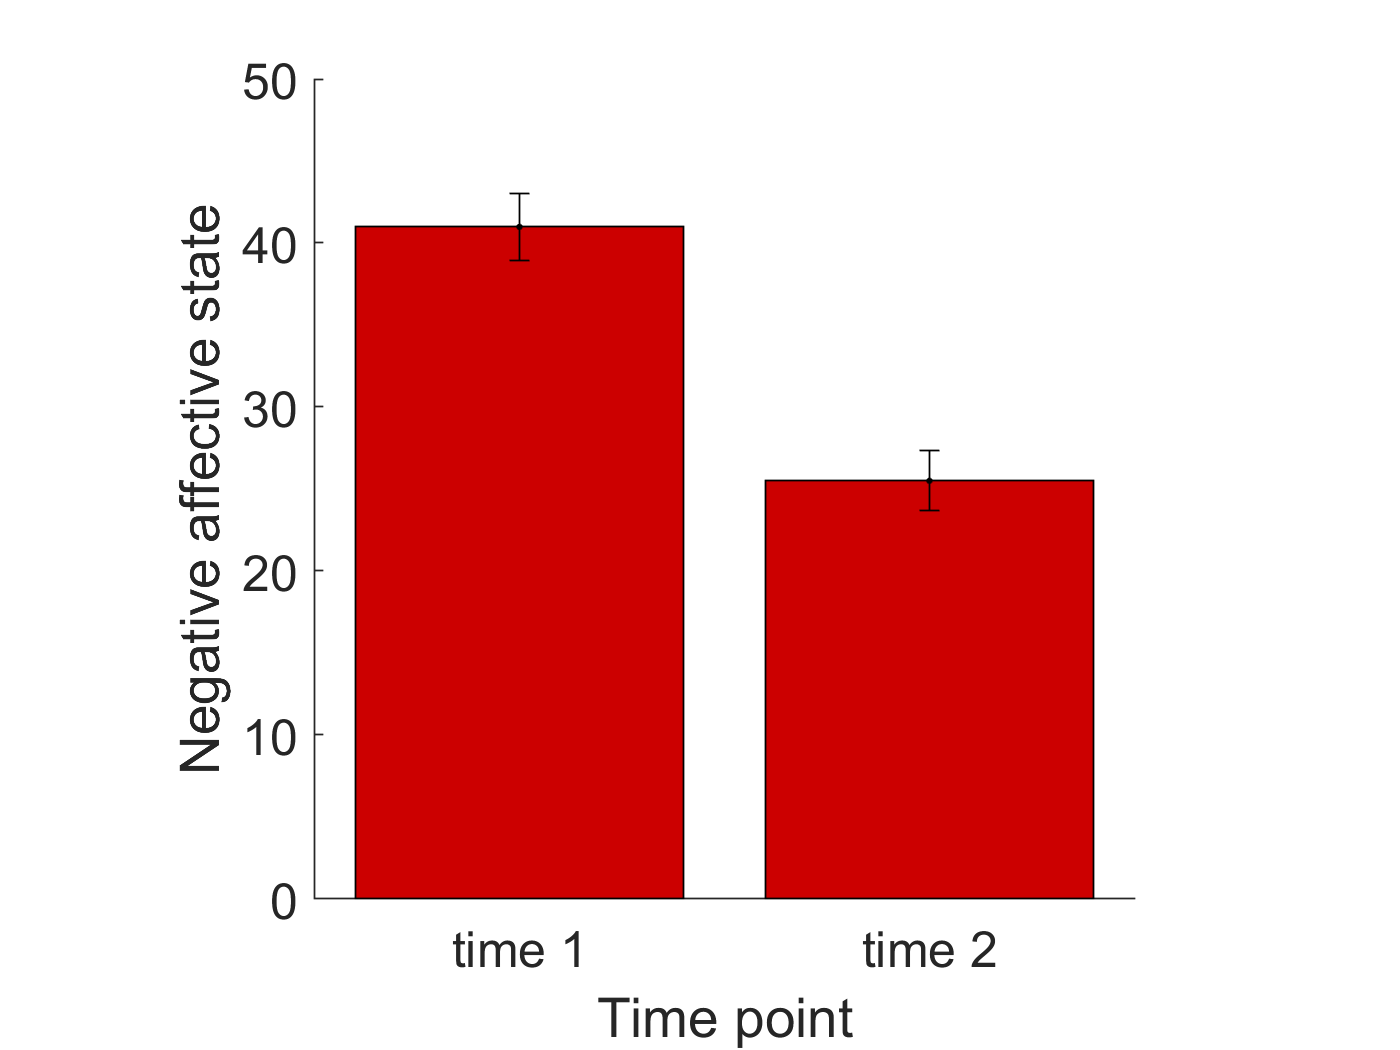

matStats.decision.Affects.ACorrTP = array2table([rho p]);
matStats.decision.Affects.ACorrTP.Properties.VariableNames = {'rho','p'};

%% S3F
figure;
% subplot(2,3,6);
hold on;
bar(nanmean([XX YY]),'FaceColor',[0.8 0 0])
errorbar(nanmean([XX YY]), nanstd([XX YY])./sqrt(size(XX,1)),'k.')
ylabel('Negative affective state')
xlabel('Time point')
set(gca,'XTick',1:2,'XTickLabel',{'time 1','time 2'},'FontSize',15)
% ylim([-5 -4])
axis square

[h p c stats] = ttest(XX-YY);
diff = (XX-YY);
%set(gca,'YTick',[1:6],'YTickLabel',{'none 1','2','3','4','5','high 6'},'FontSize',15)
var2Table = [mean(XX),std(XX)/sqrt(size(XX,1)),mean(YY),std(YY)/sqrt(size(YY,1)),mean(diff),std(diff)/sqrt(size(diff,1)),stats.tstat,stats.df,p];
matStats.Affects.meanDiff = array2table(var2Table);
matStats.Affects.meanDiff.Properties.VariableNames ={'MeanTime1','SETime1','MeanTime2','SETime2','MeanDiff','SE','t','df','p'};

%% Supplementary figure 3
%% 3A
y  = zscore(log(matestTP1(idxNewSample(income.sign<3),1)));
M  =  zscore(mean(dataTP1((income.sign<3),[10:1:12]),2));%zscore(dataTP2(1:199,18)); %zscore(dataTP2(1:199,18));%zscore(income.shockTP2);
IV =  zscore(incomeShockTP1);
% D = demographics(idx)
validata = ~isnan(y);

[b,stats] = robustfit([demographics IV],M);
% get full stats for IS
var2Table = [[b(end) stats.se(end) stats.t(end) stats.dfe stats.p(end)]];
matStats.decision.Affects.AISdem = array2table(var2Table);
matStats.decision.Affects.AISdem.Properties.VariableNames = {'beta','se','t','df','p'};
% matStats.decision.Affects.AISdem.Properties.RowNames = {'time 1','time 2'};
% get the p-values for demographics, to report to the plot
var2Table = [stats.p(2:(end-1))'];
matStats.decision.Affects.Adem = array2table(var2Table);
matStats.decision.Affects.Adem.Properties.VariableNames = {'Age' 'Gender' 'Education' 'Income'};

% figure;hold on;
% bar(1,b(end),'FaceColor',[0.9 0.6 0]);
% errorbar(1,b(end),stats.se(end),'k.')
% lnames = {'Income shock'} % behaviour
% text(1,-0.4,lnames,'rotation',90,'FontSize',18)
% ylabel({'Standardised \beta predicting'; ['\bf negative affective states']})
% title('Time 1')
% set(gca,'FontSize',15)
% h = gca; h.XAxis.Visible = 'off';
% ylim([-0.4 0.4])

## **Supplementary figure 5. Temporal discounting rate is related to negative affect in the subset of participants in Time 1 but not Time 2. **

**A: **data collected at time 1 of the subset. **B:** data collected at time 2. For illustration purposes participants were median split into those experiencing high negative affective state in red (>=50) and low negative affective state in green (<50). Displayed are the proportion of trials in which participants selected the immediate reward over the delayed reward (Y axis) as a function of the days associated with the delayed reward (X axis). The lines represent the prediction of the hyperbolic model and dots represent observed data. Error bars and shaded areas represents the standard error of the mean. 

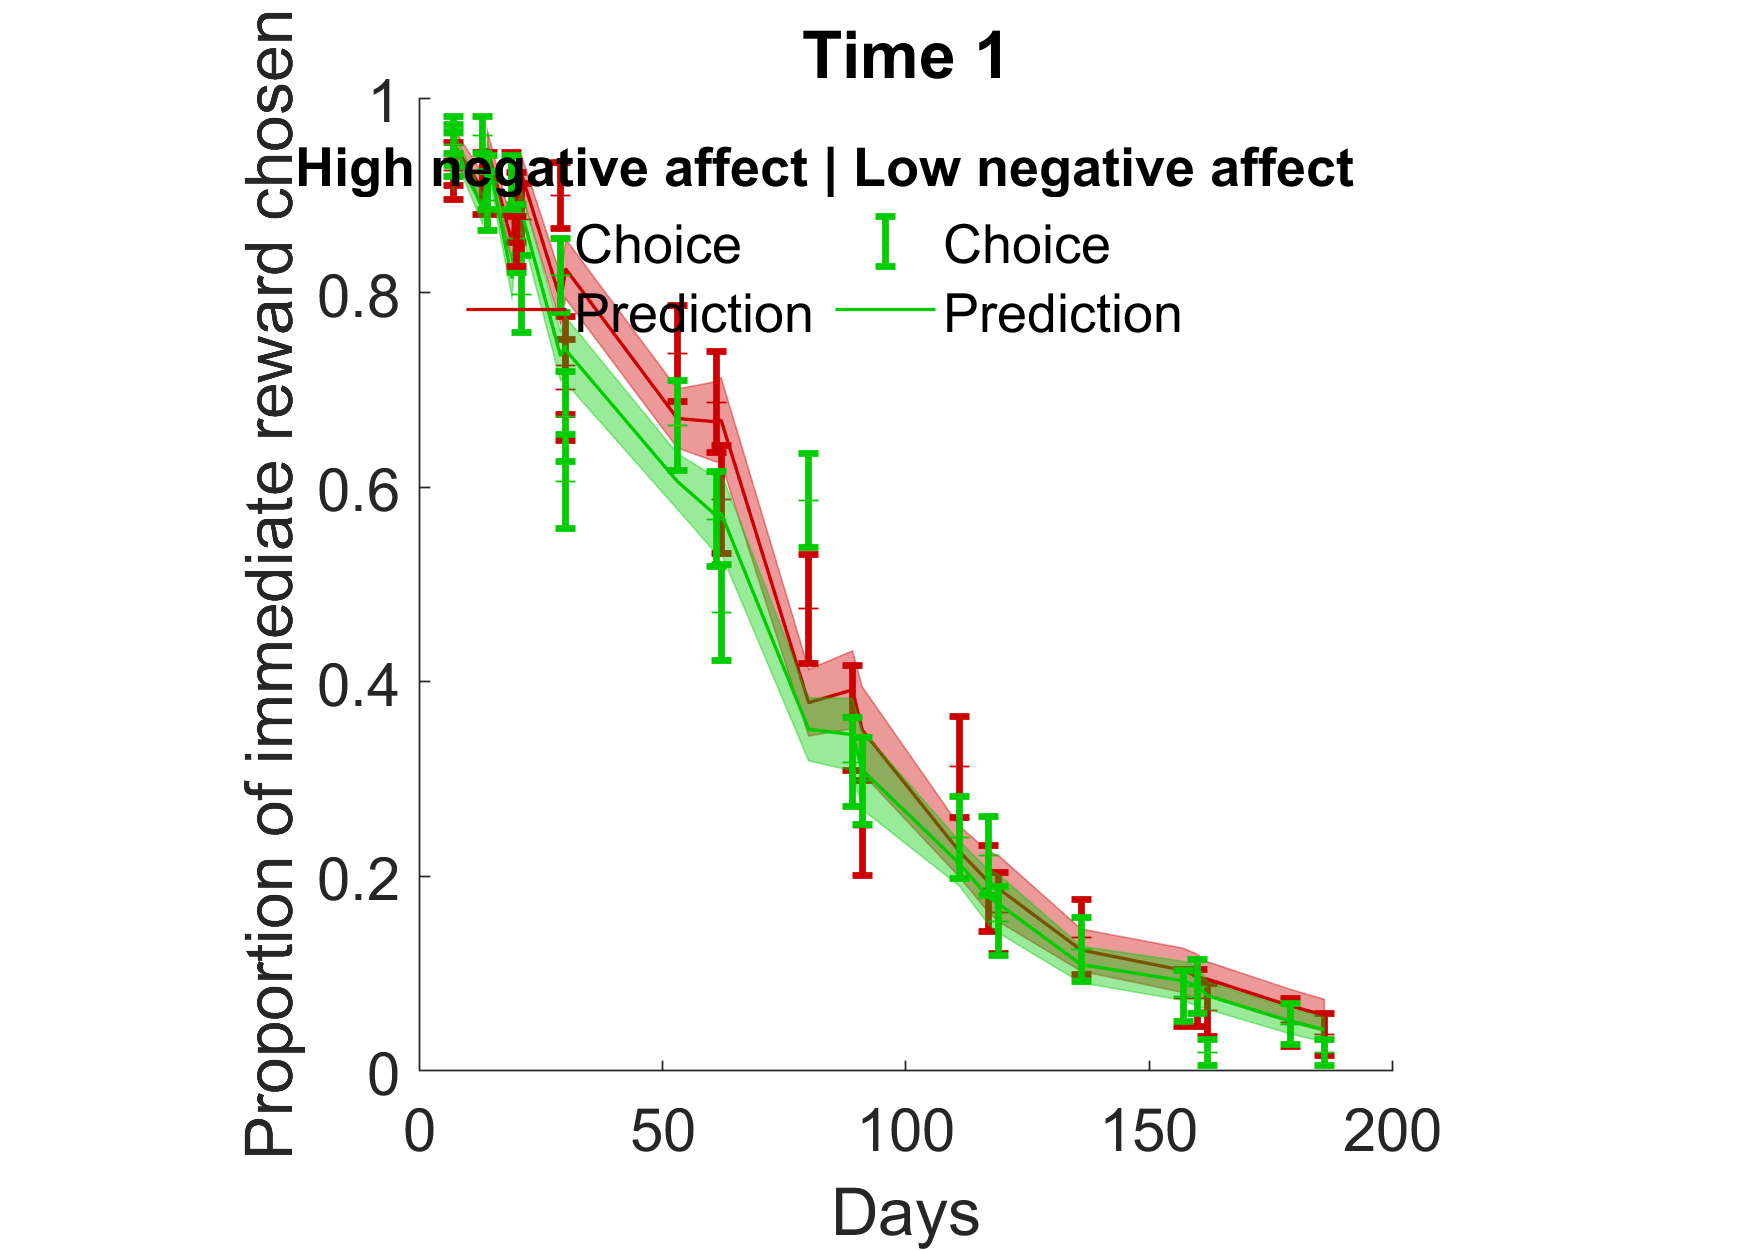

%% Affective states
%% Correlations between emotions
%% Supplementary figure 5 A 
XX=mean(dataTP1(income.sign<3,[10:1:12]),2);
figure('Renderer', 'painters', 'Position', [10 10 700 500]);hold on;
for igroup=1:2
    if igroup==1
        ioi = XX >= 50 ;%median(XX);% & matr2(idxNewSample)'>0.1;%& matpseudoR2'>0.1;%income.shock>=3;
        lcolor = [0.8 0 0];
    else
        ioi =  XX < 50;%median(XX);% & matr2(idxNewSample)'>0.1;%& matpseudoR2'>0.1;%income.shock<3;
        lcolor = [0 0.8 0];
    end
    
    [ratioOrd] = sort(delay(2,:));%sort(log((rewardmag(2,:)./rewardmag(1,:)-1)./delay(2,:)));
    
    jbfill(ratioOrd,mean(matpredITC_sortedTP1(idxNewSample(ioi),:))+std(matpredITC_sortedTP1(idxNewSample(ioi),:))./sqrt(sum(ioi)),...
        mean(matpredITC_sortedTP1(idxNewSample(ioi),:))-std(matpredITC_sortedTP1(idxNewSample(ioi),:))./sqrt(sum((ioi))),...
        lcolor,lcolor,0,0.4);
     plot0{igroup} = plot(ratioOrd,mean(pImpSortedTP1(idxNewSample(ioi),:)),'+','Color',lcolor);
     plot1{igroup} = errorbar(ratioOrd,mean(pImpSortedTP1(idxNewSample(ioi),:)),std(pImpSortedTP1(idxNewSample(ioi),:))./sqrt(sum(ioi)),'.','Color',lcolor,'LineWidth',2);
     plot2{igroup} = plot(ratioOrd,mean(matpredITC_sortedTP1(idxNewSample(ioi),:)),'k','LineWidth',1,'Color',lcolor);
%     xlabel('log(delayed reward/Immediate reward)')
    xlabel('Days')
    ylabel('Proportion of immediate reward chosen')
    title('Time 1')
    set(gca,'FontSize',18)
    %xlim([1,27])
    if igroup==2
        l = legend([plot1{1} plot2{1} plot1{2} plot2{2}],{'Choice','Prediction','Choice','Prediction'});
        l.NumColumns = 2;
        title(l,'High negative affect | Low negative affect')
        legend boxoff
    end
    axis square
end 

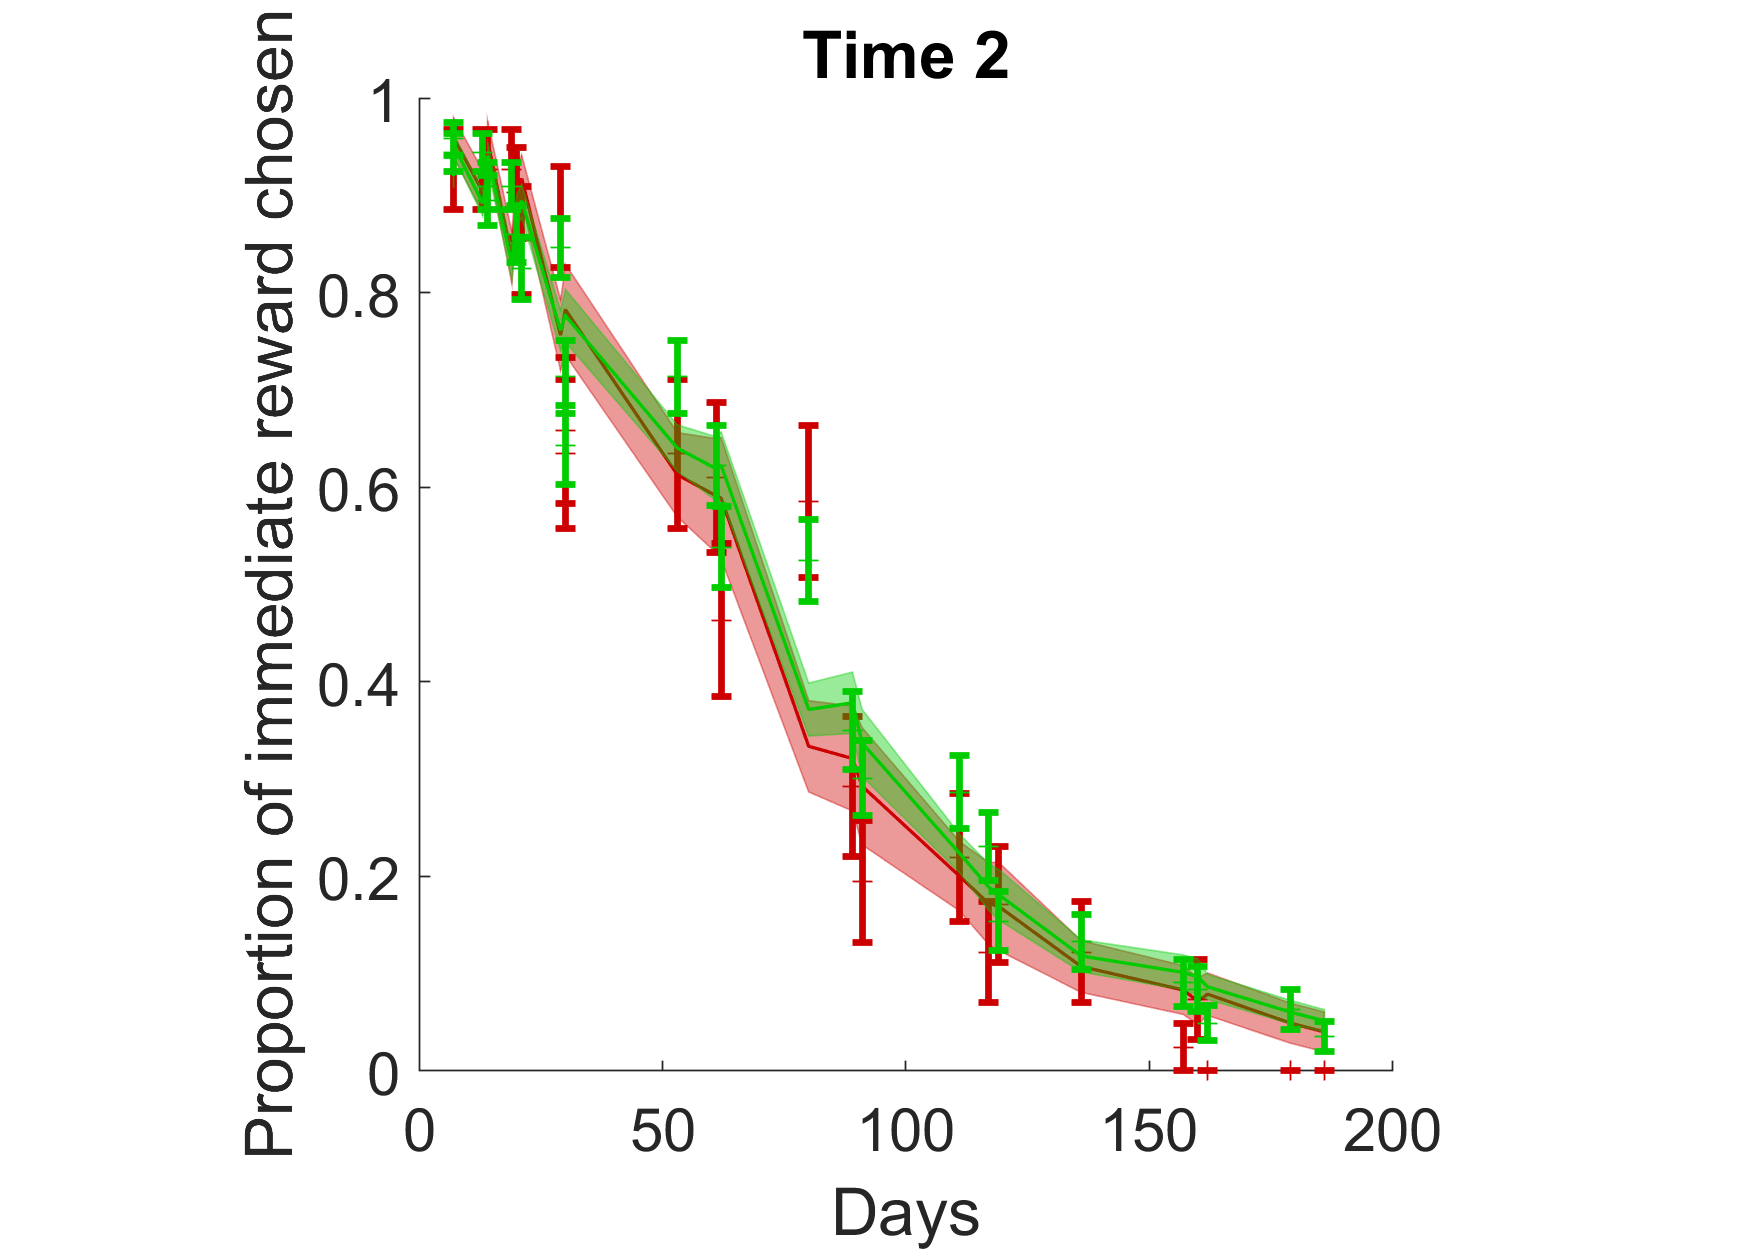


%% Supplementary figure 5B
XX=mean(matemotion(income.sign<3,[1 4 5]),2);
figure('Renderer', 'painters', 'Position', [10 10 700 500]) ;   hold on;
for igroup=1:2
   if igroup==1
        ioi = XX >= 50 ;%median(XX);% & matr2(idxNewSample)'>0.1;%& matpseudoR2'>0.1;%income.shock>=3;
        lcolor = [0.8 0 0];
    else
        ioi =  XX < 50;%median(XX);% & matr2(idxNewSample)'>0.1;%& matpseudoR2'>0.1;%income.shock<3;
        lcolor = [0 0.8 0];
    end
    
    [ratioOrd] = sort(delay(2,:));%sort(log((rewardmag(2,:)./rewardmag(1,:)-1)./delay(2,:)));
    
    jbfill(ratioOrd,mean(matpredITC_sortedTP1(idxNewSample(ioi),:))+std(matpredITC_sortedTP1(idxNewSample(ioi),:))./sqrt(sum(ioi)),...
        mean(matpredITC_sortedTP1(idxNewSample(ioi),:))-std(matpredITC_sortedTP1(idxNewSample(ioi),:))./sqrt(sum((ioi))),...
        lcolor,lcolor,0,0.4);
     plot1{igroup} = plot(ratioOrd,mean(pImpSortedTP1(idxNewSample(ioi),:)),'+','Color',lcolor);
     plot1{igroup} = errorbar(ratioOrd,mean(pImpSortedTP1(idxNewSample(ioi),:)),std(pImpSortedTP1(idxNewSample(ioi),:))./sqrt(sum(ioi)),'.','Color',lcolor,'LineWidth',2);
     plot2{igroup} = plot(ratioOrd,mean(matpredITC_sortedTP1(idxNewSample(ioi),:)),'k','LineWidth',1,'Color',lcolor);
%     xlabel('log(delayed reward/Immediate reward)')
    xlabel('Days')
    ylabel('Proportion of immediate reward chosen')
    title('Time 2')
    set(gca,'FontSize',18)
    %xlim([1,27])
    if igroup==2
        l = legend([plot1{1} plot2{1} plot1{2} plot2{2}],{'Choice','Prediction','Choice','Prediction'});
        l.NumColumns = 2;
        title(l,'High negative affect | Low negative affect')
        legend boxoff
    end
    axis square
    legend off
end 